# **Analysing Force Plate and Limb Vector Positioning For the different frog species **

# Analysing Force Plate Data 

This code analyses the force and kinematic data that was taken as the frogs (mutiple species)  walked across a force plate. The x, y, and z forces will be analysed in this code, and will then be combined and analysed against all of the other trials. In addition to the (x), (y) and (z) data, we also calculate resultant force (R). Joint angle data was collect via digitization over two strides in the fore- and hindlimbs. Additionally, the distance between tendons will be calculated.

**Contributors: **

M Kearns

CM Reynaga

Jenifer Fabian Dubon

**Last updated: **

July 19, 2022

## Setting Directory & Clearning Workspace

 clear variables % so that it clears the workspace prior to every time the code is run
tic % setting up run timer
close all   % closes previous figure windows

%cd 'H:\Madison'
%cd /Users/creynaga/Documents/MATLAB/BMC/PH_data/MatlabData/
cd '/Volumes/LaCie/JFabianDubon/'

## Parameters

A single stride was defined as: The moment on a forelimb phallange/limb, closest to the side of interest, made contact with the ground, as the start of the stride. The stride ends once all limbs have cycled through, until the same start forelimb is about to make contact again with the ground to start a new stride. 

**Video Information**

*This section will read in the parameters from the follow imported excel sheet*

params = 'quadrupedel_Parameters.xlsx'

params = 'quadrupedel_Parameters.xlsx'

parameters = importdata(params)

parameters = struct with fields:
        data: [9×27 double]
    textdata: {10×28 cell}


Change number based upon the row you'd like to process with the excel spread sheet and **save the matlab code before you run the code!**

excel_row_to_process = 10 

excel_row_to_process = 10

**Video Informationph**

Reading in parameters from excel sheet

row_to_process = excel_row_to_process-1

row_to_process = 9

date = num2str(parameters.data(row_to_process,1))

date = '20220429'

genus_species = 'ks'

genus_species = 'ks'

individual = num2str(parameters.data(row_to_process,3))

individual = '1'

walk_num = num2str(parameters.data(row_to_process,4))

walk_num = '3'

walk_seq = append(date,'_',genus_species,individual,'_walk',walk_num)

walk_seq = '20220429_ks1_walk3'

fps = 250   % high speed video frame rate

fps = 250

igor_sr = parameters.data(row_to_process,20)   % igor sample rate/frequency is it 10000 or 100000

igor_sr = 10000

body_weight =parameters.data(row_to_process,23) % frog's mass needed to normalized the data

body_weight = 2.6100


%force points for each of the 4 corners of the force plate
fp_pnt_A = parameters.data(row_to_process,24)

fp_pnt_A = 758

fp_pnt_B = parameters.data(row_to_process,25)

fp_pnt_B = 758

fp_pnt_C = parameters.data(row_to_process,26)

fp_pnt_C = 758

fp_pnt_D = parameters.data(row_to_process,27)

fp_pnt_D = 758

**Video Conditions**

FL =  parameters.data(row_to_process,14)  % does the FL make good contact with the force plate in this walk seq?

FL = 1

HL = parameters.data(row_to_process,15) % does the HL make good contact with the force plate in this walk seq?

HL = 1

Overlap = parameters.data(row_to_process,16)  % is their overlap between when the FL and HL are on the force plate?

Overlap = 1

%HL_salvage = parameters.data.ViableData(row_to_process,12)  % value of 1 suggest we can salvage some info for preliminary analysis of HL

**Walk Sequence Information**

Converting video frames into time (sec)

totalf= parameters.data(row_to_process,13)   % total amount of video frames

totalf = 758

totalf_sec = round((totalf/fps),4)       % total amount of time filmed

totalf_sec = 3.0320

startf_s1 = parameters.data(row_to_process,5)   % beginning frame for stride 1 defined as forelimb nearest to the camera touches down

startf_s1 = 141

startf_s1_sec = round((startf_s1/fps),4)

startf_s1_sec = 0.5640

endf_s1 =  parameters.data(row_to_process,10)    % end frame for stride 1 defined as the frame right before the forelimb touches back to start the next stride

endf_s1 = 271

endf_s1_sec = round((endf_s1/fps),4)

endf_s1_sec = 1.0840

startf_s2 = parameters.data(row_to_process,11)   % beginning frame for stride 2

startf_s2 = 272

startf_s2_sec = round((startf_s2/fps),4)

startf_s2_sec = 1.0880

endf_s2 = parameters.data(row_to_process,12) % end frame for stride 2; if not a complete 2nd stride insert '0'

endf_s2 = 408

endf_s2_sec = round((endf_s2/fps),4)

endf_s2_sec = 1.6320

trigger_t = parameters.data(row_to_process,19)   % from IGOR

trigger_t = 6.4296

force_time = round(((1:igor_sr)'/10000),4)  % time array for forceplate data

force_time =     0.0001
    0.0002
    0.0003
    0.0004
    0.0005
    0.0006
    0.0007
    0.0008
    0.0009
    0.0010


fl_end = parameters.data(row_to_process,8)    % last frame front toe touches force plate before leaving

fl_end = 244

fl_end_sec = round((fl_end/fps),4)

fl_end_sec = 0.9760

hl_start = parameters.data(row_to_process,6)   % back toe touches force plate / hindlim makes contact with the forceplate for the first time.  (for mine its not the toe, its one of the other fingers that make contact first.

hl_start = 232

hl_start_sec = round((hl_start/fps),4)

hl_start_sec = 0.9280

hl_end = parameters.data(row_to_process,9)    % last frame back toe touch force plate before leaving

hl_end = 327

hl_end_sec = round((hl_end/fps),4)

hl_end_sec = 1.3080


fl_only_ends = hl_start -1;                    % frame where only the fl ends contact with the force plate
fl_only_ends_sec = round((fl_only_ends/fps),4)

fl_only_ends_sec = 0.9240


hl_only_starts = fl_end +1;                    %beginning frame where the hl is the only one that is in contact with the force plate
hl_only_starts_sec = round((hl_only_starts/fps),4)

hl_only_starts_sec = 0.9800

## Converstions from frames to sec 

Finding the distance in time from the end of the video, to set-up to align with the trigger.

delta_fl_only_end = totalf_sec - fl_only_ends_sec  

delta_fl_only_end = 2.1080

delta_hl_only_starts = totalf_sec - hl_only_starts_sec

delta_hl_only_starts = 2.0520


delta_s1_start = totalf_sec-startf_s1_sec

delta_s1_start = 2.4680

delta_s1_end = totalf_sec-endf_s1_sec

delta_s1_end = 1.9480

delta_fl_end = totalf_sec-fl_end_sec

delta_fl_end = 2.0560

delta_hl_on = totalf_sec-hl_start_sec

delta_hl_on = 2.1040

delta_hl_end = totalf_sec-hl_end_sec

delta_hl_end = 1.7240

delta_s2_start = totalf_sec-startf_s2_sec

delta_s2_start = 1.9440

if endf_s2_sec ~= 0
    delta_s2_end = totalf_sec-endf_s2_sec 
end

delta_s2_end = 1.4000


%   start cut occurs at time of HL on and FL end
 start_cut = abs(round(trigger_t-delta_s1_start,5))

start_cut = 3.9616

 end_cut= round(trigger_t-delta_s1_end,5)

end_cut = 4.4816

# Analysing Joint Angle Variation In Forward Locomotion

This code will go through:

- each step of the experimental approach 

- how the data was processed

- plotting the graphs to contrast the changes in velocity

**Important Note:**

The frog was characterized within the constraints of a single stride. One stride begins when the front foot closest to the camera lifts, and it ends right as the foot is placed back on the ground in anticipation for another stride.

### Setting Up The Workspace

xyzfile = fullfile("20220429/20220429_ks1_walk3_dataxyzpts.csv")

xyzfile = "20220429/20220429_ks1_walk3_dataxyzpts.csv"

xyzpts = importdata(xyzfile)

xyzpts = struct with fields:
          data: [758×42 double]
      textdata: {1×42 cell}
    colheaders: {1×42 cell}


**Important Points To Digitize & Analyze**

- Eye

- Center of Mass

- Shoulder

- Elbow

- Wrist

- Hip

- Knee

- Torso/ankle

- Longest phalange (hind L limb)

- Longest phalange (fore L limb)

- Force Plate "A" point

- Force Plate "B" point

- Force Plate "C" point

- Force Plate "D" point

In order to make sure that MATLAB orients the data correctly, we assign the point values to the individual columns, and specify the frame numbers (rows) that we want to grab data from.

pt1_X_s1 = xyzpts.data(startf_s1:endf_s1, 1);
pt1_Y_s1 = xyzpts.data(startf_s1:endf_s1, 2);
pt1_Z_s1 = xyzpts.data(startf_s1:endf_s1, 3);

pt2_X_s1 = xyzpts.data(startf_s1:endf_s1, 4);
pt2_Y_s1 = xyzpts.data(startf_s1:endf_s1, 5);
pt2_Z_s1 = xyzpts.data(startf_s1:endf_s1, 6);

pt3_X_s1 = xyzpts.data(startf_s1:endf_s1, 7);
pt3_Y_s1 = xyzpts.data(startf_s1:endf_s1, 8);
pt3_Z_s1 = xyzpts.data(startf_s1:endf_s1, 9);

pt4_X_s1 = xyzpts.data(startf_s1:endf_s1, 10);
pt4_Y_s1 = xyzpts.data(startf_s1:endf_s1, 11);
pt4_Z_s1 = xyzpts.data(startf_s1:endf_s1, 12);

pt5_X_s1 = xyzpts.data(startf_s1:endf_s1, 13);
pt5_Y_s1 = xyzpts.data(startf_s1:endf_s1, 14);
pt5_Z_s1 = xyzpts.data(startf_s1:endf_s1, 15);

pt6_X_s1 = xyzpts.data(startf_s1:endf_s1, 16);
pt6_Y_s1 = xyzpts.data(startf_s1:endf_s1, 17);
pt6_Z_s1 = xyzpts.data(startf_s1:endf_s1, 18);

pt7_X_s1 = xyzpts.data(startf_s1:endf_s1, 19);
pt7_Y_s1 = xyzpts.data(startf_s1:endf_s1, 20);
pt7_Z_s1 = xyzpts.data(startf_s1:endf_s1, 21);

pt8_X_s1 = xyzpts.data(startf_s1:endf_s1, 22);
pt8_Y_s1 = xyzpts.data(startf_s1:endf_s1, 23);
pt8_Z_s1 = xyzpts.data(startf_s1:endf_s1, 24);

pt9_X_s1 = xyzpts.data(startf_s1:endf_s1, 25);
pt9_Y_s1 = xyzpts.data(startf_s1:endf_s1, 26);
pt9_Z_s1 = xyzpts.data(startf_s1:endf_s1, 27);

pt10_X_s1 = xyzpts.data(startf_s1:endf_s1, 28);
pt10_Y_s1 = xyzpts.data(startf_s1:endf_s1, 29);
pt10_Z_s1 = xyzpts.data(startf_s1:endf_s1, 30);

`If` data set has hindlimb data


    pt1_X_s2 = xyzpts.data(startf_s2:endf_s2, 1);
    pt1_Y_s2 = xyzpts.data(startf_s2:endf_s2, 2);
    pt1_Z_s2 = xyzpts.data(startf_s2:endf_s2, 3);

    pt2_X_s2 = xyzpts.data(startf_s2:endf_s2, 4);
    pt2_Y_s2 = xyzpts.data(startf_s2:endf_s2, 5);
    pt2_Z_s2 = xyzpts.data(startf_s2:endf_s2, 6);

    pt3_X_s2 = xyzpts.data(startf_s2:endf_s2, 7);
    pt3_Y_s2 = xyzpts.data(startf_s2:endf_s2, 8);
    pt3_Z_s2 = xyzpts.data(startf_s2:endf_s2, 9);

    pt4_X_s2 = xyzpts.data(startf_s2:endf_s2, 10);
    pt4_Y_s2 = xyzpts.data(startf_s2:endf_s2, 11);
    pt4_Z_s2 = xyzpts.data(startf_s2:endf_s2, 12);

    pt5_X_s2 = xyzpts.data(startf_s2:endf_s2, 13);
    pt5_Y_s2 = xyzpts.data(startf_s2:endf_s2, 14);
    pt5_Z_s2 = xyzpts.data(startf_s2:endf_s2, 15);
    
    pt6_X_s2 = xyzpts.data(startf_s2:endf_s2, 16);
    pt6_Y_s2 = xyzpts.data(startf_s2:endf_s2, 17);
    pt6_Z_s2 = xyzpts.data(startf_s2:endf_s2, 18);

    pt7_X_s2 = xyzpts.data(startf_s2:endf_s2, 19);
    pt7_Y_s2 = xyzpts.data(startf_s2:endf_s2, 20);
    pt7_Z_s2 = xyzpts.data(startf_s2:endf_s2, 21);

    pt8_X_s2 = xyzpts.data(startf_s2:endf_s2, 22);
    pt8_Y_s2 = xyzpts.data(startf_s2:endf_s2, 23);
    pt8_Z_s2 = xyzpts.data(startf_s2:endf_s2, 24);

    pt9_X_s2 = xyzpts.data(startf_s2:endf_s2, 25);
    pt9_Y_s2 = xyzpts.data(startf_s2:endf_s2, 26);
    pt9_Z_s2 = xyzpts.data(startf_s2:endf_s2, 27);

    pt10_X_s2 = xyzpts.data(startf_s2:endf_s2, 28);
    pt10_Y_s2 = xyzpts.data(startf_s2:endf_s2, 29);
    pt10_Z_s2 = xyzpts.data(startf_s2:endf_s2, 30);


Both stride 1 and 2 digitized points concatinated


    pt1_X = cat(1, pt1_X_s1, pt1_X_s2);
    pt1_Y = cat(1, pt1_Y_s1, pt1_Y_s2);
    pt1_Z = cat(1, pt1_Z_s1, pt1_Z_s2);

    pt2_X = cat(1, pt2_X_s1, pt2_X_s2);
    pt2_Y = cat(1, pt2_Y_s1, pt2_Y_s2);
    pt2_Z = cat(1, pt2_Z_s1, pt2_Z_s2);

    pt3_X = cat(1, pt3_X_s1, pt3_X_s2);
    pt3_Y = cat(1, pt3_Y_s1, pt3_Y_s2);
    pt3_Z = cat(1, pt3_Z_s1, pt3_Z_s2);

    pt4_X = cat(1, pt4_X_s1, pt4_X_s2);
    pt4_Y = cat(1, pt4_Y_s1, pt4_Y_s2);
    pt4_Z = cat(1, pt4_Z_s1, pt4_Z_s2);

    pt5_X = cat(1, pt5_X_s1, pt5_X_s2);
    pt5_Y = cat(1, pt5_Y_s1, pt5_Y_s2);
    pt5_Z = cat(1, pt5_Z_s1, pt5_Z_s2);
    
    pt6_X = cat(1, pt6_X_s1, pt6_X_s2);
    pt6_Y = cat(1, pt6_Y_s1, pt6_Y_s2);
    pt6_Z = cat(1, pt6_Z_s1, pt6_Z_s2);

    pt7_X = cat(1, pt7_X_s1, pt7_X_s2);
    pt7_Y = cat(1, pt7_Y_s1, pt7_Y_s2);
    pt7_Z = cat(1, pt7_Z_s1, pt7_Z_s2);

    pt8_X = cat(1, pt8_X_s1, pt8_X_s2);
    pt8_Y = cat(1, pt8_Y_s1, pt8_Y_s2);
    pt8_Z = cat(1, pt8_Z_s1, pt8_Z_s2);

    pt9_X = cat(1, pt9_X_s1, pt9_X_s2);
    pt9_Y = cat(1, pt9_Y_s1, pt9_Y_s2);
    pt9_Z = cat(1, pt9_Y_s1, pt9_Y_s2);

    pt10_X = cat(1, pt10_X_s1, pt10_X_s2);
    pt10_Y = cat(1, pt10_Y_s1, pt10_Y_s2);
    pt10_Z = cat(1, pt10_Y_s1, pt10_Y_s2);


`If` data set has force plates A, B, C and D pts

    pnt_A_x = xyzpts.data(fp_pnt_A, 31);
    pnt_A_y = xyzpts.data(fp_pnt_A, 32);
    pnt_A_z = xyzpts.data(fp_pnt_A, 33);

    pnt_B_x = xyzpts.data(fp_pnt_B, 34);
    pnt_B_y = xyzpts.data(fp_pnt_B, 35);
    pnt_B_Z = xyzpts.data(fp_pnt_B, 36);

    pnt_C_x = xyzpts.data(fp_pnt_C, 37);
    pnt_C_y = xyzpts.data(fp_pnt_C, 38);
    pnt_C_z = xyzpts.data(fp_pnt_C, 39);

    pnt_D_x = xyzpts.data(fp_pnt_D, 40);
    pnt_D_y = xyzpts.data(fp_pnt_D, 41);
    pnt_D_z = xyzpts.data(fp_pnt_D, 42);

## Creating Percent Stride for Digitized Data

Finding percent stride for stride 1 and 2

[~, stride1size] = size(startf_s1:endf_s1)  % finds the array size from the start of the stride to the end

stride1size = 131

p_stride1 = (((1:stride1size)'/stride1size).*100);   % use if only have forelimb data

Provides percent stride for stride 2 and both stride 1 and 2 concatenated together 

if HL == 1    
    [~, stride2size] = size(startf_s2:endf_s2)  % finding the size from the start of the stride to the end
    p_stride2 = (((1:stride2size)'/stride2size).*100)+100
    
    % concatinating forelimb and hindlimb percent stride  
    total_digitized_time = cat(1, p_stride1, p_stride2) % use for videos with both FL and HL digitized data
end

stride2size = 137

p_stride2 =   100.7299
  101.4599
  102.1898
  102.9197
  103.6496
  104.3796
  105.1095
  105.8394
  106.5693
  107.2993


total_digitized_time =     0.7634
    1.5267
    2.2901
    3.0534
    3.8168
    4.5802
    5.3435
    6.1069
    6.8702
    7.6336


## converting frames to time 

stride 1

video_s1_frame = xyzpts.data(startf_s1:endf_s1, 1)    %THIS PART IS NOT NEEDED

video_s1_frame =     3.8311
    3.8968
    4.0628
    4.1092
    4.4183
    4.5106
    4.7413
    4.9395
    5.0663
    5.2062


                                                        
video_s2_frame = xyzpts.data(startf_s2:endf_s2, 1)

video_s2_frame =    42.2035
   42.4765
   42.7992
   42.9873
   43.2692
   43.6390
   43.9522
   44.3096
   44.5721
   44.8400




s1_frame_t = video_s1_frame ./250

s1_frame_t =     0.0153
    0.0156
    0.0163
    0.0164
    0.0177
    0.0180
    0.0190
    0.0198
    0.0203
    0.0208


s2_frame_t = video_s2_frame ./250

s2_frame_t =     0.1688
    0.1699
    0.1712
    0.1719
    0.1731
    0.1746
    0.1758
    0.1772
    0.1783
    0.1794




 t_force = datavalues(s1_start_force_c:s2_end_force_c )

t_force =     0.0032    0.0032    0.0032    0.0032    0.0032    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0038    0.0038    0.0038    0.0038    0.0038    0.0039    0.0039    0.0039    0.0039    0.0039    0.0040    0.0040



%time for the frames
fl_only_v_time = (startf_s1: fl_only_ends)' ./250

fl_only_v_time =     0.5640
    0.5680
    0.5720
    0.5760
    0.5800
    0.5840
    0.5880
    0.5920
    0.5960
    0.6000



fl_only_v_t_sec = fl_only_v_time - fl_only_v_time(1)

fl_only_v_t_sec =          0
    0.0040
    0.0080
    0.0120
    0.0160
    0.0200
    0.0240
    0.0280
    0.0320
    0.0360



hl_only_v_time = (hl_only_starts: hl_end)' ./250

hl_only_v_time =     0.9800
    0.9840
    0.9880
    0.9920
    0.9960
    1.0000
    1.0040
    1.0080
    1.0120
    1.0160



hl_only_v_t_sec = hl_only_v_time - hl_only_v_time(1)

hl_only_v_t_sec =          0
    0.0040
    0.0080
    0.0120
    0.0160
    0.0200
    0.0240
    0.0280
    0.0320
    0.0360




%time for the force variables


## Finding Angle Measurements In The Arm

When figuring out the angles, first we have to figure out the distances between all of the points. For simplicity purposes, we will start with looking at Point 3 (shoulder), Point 4 (elbow), and Point 5 (wrist). Here, W will indicate wrist angle, S will indicate shoulder angle, and E will indicate elbow angle

Distance from point 3 to 4 will be denoted as D_s

Distance from point 4 to point 5 will be denoted as D_e

Distance from point 5 to point 3 will be denoted as D_w

**Distance Between Shoulder and Elbow**

d_s= sqrt((pt3_X_s1-pt4_X_s1).^2+(pt3_Y_s1-pt4_Y_s1).^2+(pt3_Z_s1-pt4_Z_s1).^2);

**Distance Between Elbow and Wrist**

 d_e= sqrt((pt4_X_s1-pt5_X_s1).^2+(pt4_Y_s1-pt5_Y_s1).^2+(pt4_Z_s1-pt5_Z_s1).^2);

**Distance Between Wrist and Shoulder**

 d_w= sqrt((pt5_X_s1-pt3_X_s1).^2+(pt5_Y_s1-pt3_Y_s1).^2+(pt5_Z_s1-pt3_Z_s1).^2);

In order to find the measurements of all of the angles, we need to use a cosine formula when given all of the lengths of the sides. This formula looks like

                                        
$$A = {\frac{ b^2 + c^2 - a^2}{2bc}}\arccos$$


However, this formula will be slightly altered in order to integrate the variables that have been given to us. Now, it looks like this

                                        
$$E = {\frac{ w^2 + s^2 - e^2}{2ws}}\arccos$$


Now the code must be applied to each set of variables to give the angle measurements for the frogs movement over time. Then, the three variables can be plotted on a graph against time.

S= acosd((d_w.^2+d_e.^2-d_s.^2)./(2.*d_w.*d_e));
E= acosd((d_w.^2+d_s.^2-d_e.^2)./(2.*d_w.*d_s));
W= acosd((d_e.^2+d_s.^2-d_w.^2)./(2.*d_e.*d_s));

figure(1)
 plot(p_stride1,E,p_stride1, W,p_stride1,S)
xlabel('Percent Stride')
ylabel('Angle Changes (degrees)')
legend({'Elbow Angle','Wrist Angle','Shoulder Angle'})
title('Forelimb Angle Changes Over Time')
graphname1 = append(walk_seq, '_FLjointgraph.pdf')

graphname1 = '20220429_ks1_walk3_FLjointgraph.pdf'

ax = gca

ax =   Axes (Forelimb Angle Changes Over Time) with properties:

             XLim: [0 100]
             YLim: [0 150]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


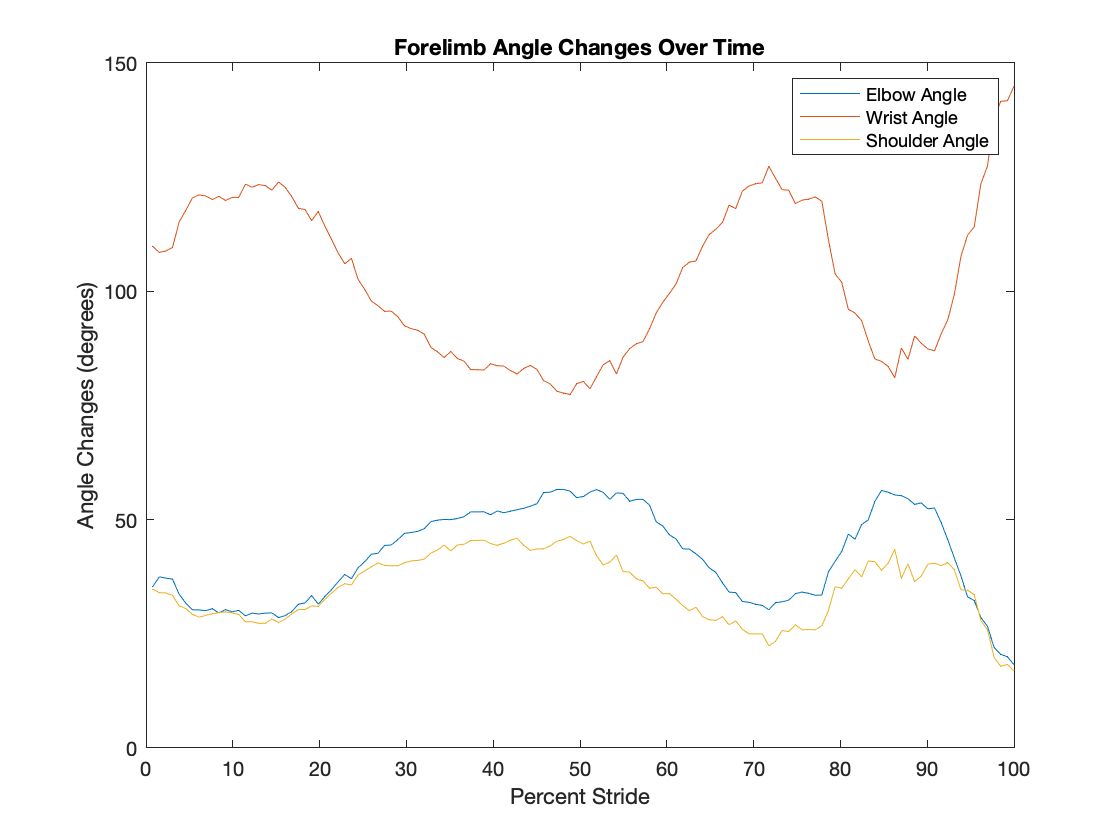

exportgraphics(ax, graphname1,'ContentType','vector')

## Vector Based Joint Angle Calculations

Va = vector from the elbow to the shoulder (pt 4 and pt 3)

Vb = vector from the elbow to the wrist (pt 4 and pt 5)

A = [pt3_X_s1 pt3_Y_s1 pt3_Z_s1];    % shoulder
B = [pt4_X_s1 pt4_Y_s1 pt4_Z_s1];   % elbow
C = [pt5_X_s1 pt5_Y_s1 pt5_Z_s1];    % wrist
Va = B-A;    % pt3- pt4; vector from shoulder to elbow
Vb = C-A;    % pt5-pt4; vector from wrist to elbow
dot_V = sum((Va.*Vb),2); % dot product; squares v's and take the same across the matrix

% product of vector magnitude
sv_Va = Va.*Va;
dp_Va = sum((sv_Va),2);
mag_Va = sqrt(dp_Va);

sv_Vb = Vb.*Vb;
dp_Vb = sum((sv_Vb),2);
mag_Vb = sqrt(dp_Vb);
theta = acosd(dot_V./(mag_Va.*mag_Vb));

Displaying Fl angle change over time

figure(2)
plot(p_stride1,theta)
xlabel('Percent Stride')
ylabel('Elbow Angle Changes (degrees)')
legend({'Elbow Angle'})
title('FL Angle Changes Over Time')

Va = vector from the knee to the hip (pt 8 and pt 7)

Vb = vector from the knee to the ankle (pt 8 and pt 9)

A = [pt7_X_s1 pt7_Y_s1 pt7_Z_s1];    % hip
B = [pt8_X_s1 pt8_Y_s1 pt8_Z_s1];    % knee
C = [pt6_X_s1 pt6_Y_s1 pt6_Z_s1];    % ankle
Va = B-A;    % pt7- pt8; vector from hip to knee
Vb = C-A;    % pt6-pt8; vector from ankle to knee
dot_V = sum((Va.*Vb),2); % dot product; squares v's and take the same across the matrix
% product of vector magnitude
sv_Va = Va.*Va;
dp_Va = sum((sv_Va),2);
mag_Va = sqrt(dp_Va);
sv_Vb = Vb.*Vb;
dp_Vb = sum((sv_Vb),2);
mag_Vb = sqrt(dp_Vb);
theta = acosd(dot_V./(mag_Va.*mag_Vb));

Displaying Hl angle change over time

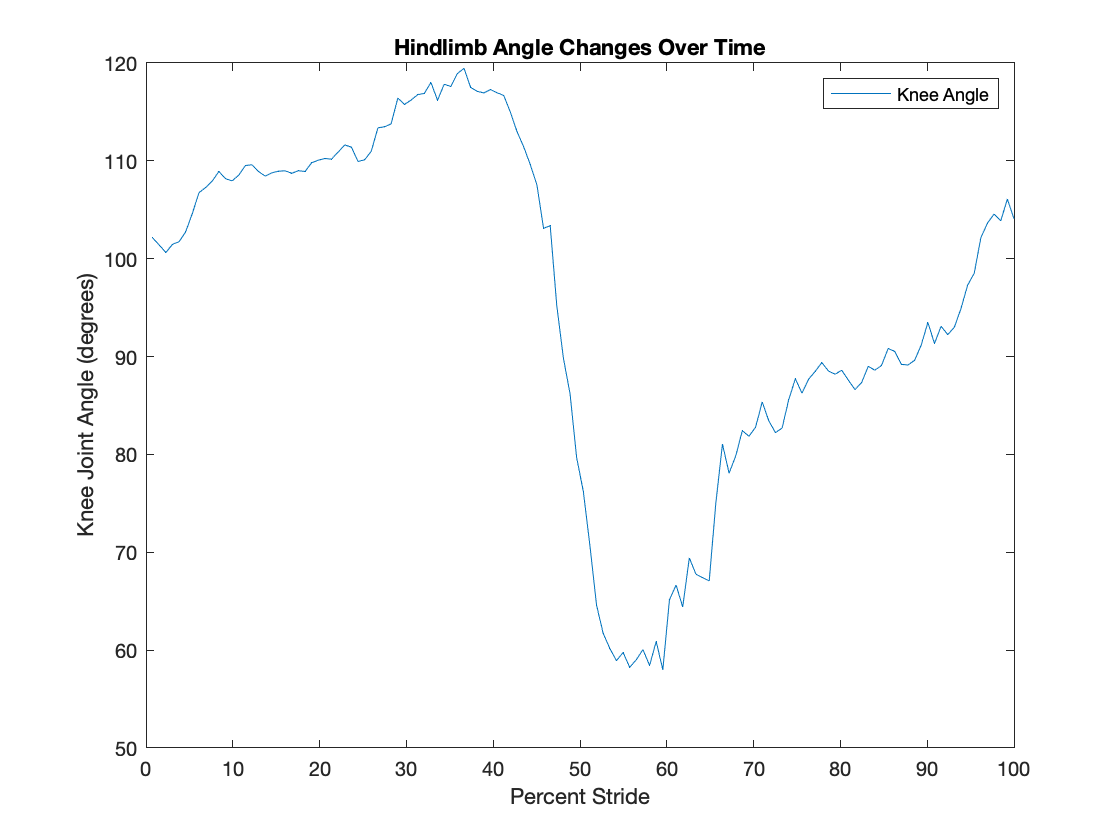


figure(3)
plot(p_stride1,theta)
xlabel('Percent Stride')
ylabel('Knee Joint Angle (degrees)')
legend({'Knee Angle'})
title('Hindlimb Angle Changes Over Time')

## Finding Angle Measurements In The Hind Limb

In this section we will manipulate the distance formula given above to match the data information. Here, K will indicate knee angle, H will indicate hip angle, and A will indicate ankle angle

**Distance Between Hip and Knee**

if HL == 1
    d_h= sqrt((pt7_X-pt8_X).^2+(pt7_Y-pt8_Y).^2+(pt7_Z-pt8_Z).^2);   
end

**Distance Between Knee and Ankle**

if HL == 1
    d_k= sqrt((pt8_X-pt9_X).^2+(pt8_Y-pt9_Y).^2+(pt8_Z-pt9_Z).^2);
end

**Distance Between Hip and Ankle**

if HL == 1
    d_a= sqrt((pt7_X-pt9_X).^2+(pt7_Y-pt9_Y).^2+(pt7_Z-pt9_Z).^2);
end

In order to find the measurements of all of the angles, we need to use a cosine formula when given all of the lengths of the sides. This formula looks like

                                        
$$A = {\frac{ b^2 + c^2 - a^2}{2bc}}\arccos$$


However, this formula will be slightly altered in order to integrate the variables that have been given to us. Now, it looks like this

                                        
$$K = {\frac{ a^2 + h^2 - k^2}{2ah}}\arccos$$


Now the code must be applied to each set of variables to give the angle measurements for the frogs movement over time. Then, the three variables can be plotted on a graph against time.

graphname4 = '20220429_ks1_walk3_HLjointgraph.pdf'

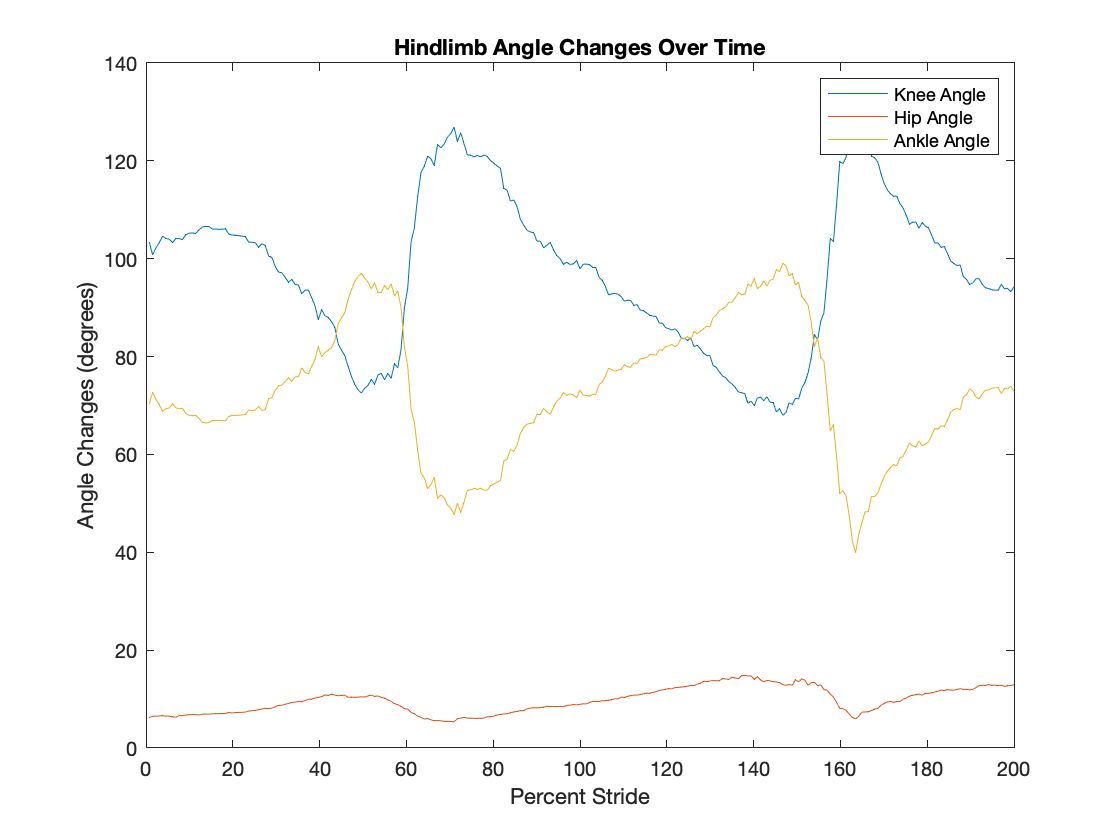

if HL == 1
    H= acosd((d_k.^2+d_a.^2-d_h.^2)./(2.*d_a.*d_k));
    K= acosd((d_a.^2+d_h.^2-d_k.^2)./(2.*d_a.*d_h));
    A= acosd((d_k.^2+d_h.^2-d_a.^2)./(2.*d_k.*d_h));
    
    figure(4)
    plot(total_digitized_time,K,total_digitized_time, H,total_digitized_time,A)
    xlabel('Percent Stride')
    ylabel('Angle Changes (degrees)')
    legend({'Knee Angle','Hip Angle','Ankle Angle'})
    title('Hindlimb Angle Changes Over Time')
    graphname4 = append(walk_seq, '_HLjointgraph.pdf')
    ax1 = gca;
    exportgraphics(ax1, graphname4,'ContentType','vector')
end

# Analysing Force Plate Data

This code analyses the force and kinematic data that was taken as the frogs (mutiple species)  walked across a force plate. 

## Converstions from video time to ground reaction force time

Finding where the force data is based upon video time calculated in the above section. 

`If else` statements are used to address issues with data wrap around. For example, if the trigger occurs earlier in the data sequence than the forces/stride sequence this suggests the data has wrapped around in time.

% executes the following if only trigger is wrapped around    
if trigger_t < delta_s1_start && trigger_t < delta_s1_end 
    s1_start_force_t = trigger_t-delta_s1_start+10
    s1_end_force_t = trigger_t-delta_s1_end+10
% executes the following if only trigger and part of the start force wrap around    
elseif trigger_t < delta_s1_start || trigger_t < delta_s1_end 
    s1_start_force_t = trigger_t-delta_s1_start+10
    s1_end_force_t = trigger_t-delta_s1_end
% executes if trigger is not wrapped around and all the force data is
% inline  Ideal one to use
else 
    s1_start_force_t = trigger_t-delta_s1_start
    s1_end_force_t = trigger_t-delta_s1_end    
end

s1_start_force_t = 3.9616

s1_end_force_t = 4.4816

Executes the following, `if` trigger occurs before `fl_end` in force time, if not, executes `else` function  

if trigger_t < delta_fl_end 
    fl_end_force_t = trigger_t-delta_fl_end+10   
else    
    fl_end_force_t = trigger_t-delta_fl_end    
end

fl_end_force_t = 4.3736

Executes the following. If the trigger occurs before fl_only_end  when is in contact, if not, execute else function

if trigger_t < delta_fl_only_end 
    fl_end_force_t_only = trigger_t-delta_fl_only_end+10   
else    
    fl_end_force_t_only = trigger_t-delta_fl_only_end    
end

fl_end_force_t_only = 4.3216

Executes the following. If the trigger occurs before hl_only_starts  when is in contact, if not, execute else function

if trigger_t < delta_hl_only_starts 
    hl_start_force_t_only = trigger_t-delta_hl_only_starts+10   
else    
    hl_start_force_t_only = trigger_t-delta_hl_only_starts    
end

hl_start_force_t_only = 4.3776

Executes the following, `if` trigger occurs before `hl_on` in force time, if not, executes `else` function    

if trigger_t < delta_hl_on 
    hl_on_force_t = trigger_t-delta_hl_on+10   
else    
    hl_on_force_t = trigger_t-delta_hl_on   
end  

hl_on_force_t = 4.3256

Executes the following, `if` trigger occurs before `hl_end` in force time, if not, executes `else` funtion

if trigger_t < delta_hl_end 
    hl_end_force_t = trigger_t-delta_hl_end+10    
else    
    hl_end_force_t = trigger_t-delta_hl_end    
end

hl_end_force_t = 4.7056

Executes the following, `if` trigger occurrs before start of *stride 2*, if not, executes `else` function

if endf_s2_sec ~= 0 || startf_s2_sec ~= 0 
    if trigger_t < delta_s2_start 
        s2_start_force_t = trigger_t-delta_s2_start+10    
    else    
        s2_start_force_t = trigger_t-delta_s2_start    
    end
end

s2_start_force_t = 4.4856

Executes the following, `if` trigger occurs before end of stride 2, if not, executes `else` function

if endf_s2_sec ~= 0
    if trigger_t < delta_s2_end 
        s2_end_force_t = trigger_t-delta_s2_end+10    
    else    
        s2_end_force_t = trigger_t-delta_s2_end    
    end 
end

s2_end_force_t = 5.0296

Finding the column in the igor file that each event corresponds to:

*Note:* 10,000 corresponds to the sampling in Igor, 10,000 samples/sec

fl_end_only_t_force_c = round(fl_end_force_t_only.*10000,4)

fl_end_only_t_force_c = 43216

hl_start_only_t_force_c = round(hl_start_force_t_only.*10000,4)

hl_start_only_t_force_c = 43776


s1_start_force_c = round(s1_start_force_t.*10000,4)

s1_start_force_c = 39616

s1_end_force_c = round(s1_end_force_t.*10000,4)

s1_end_force_c = 44816

fl_end_force_c = round(fl_end_force_t.*10000,4)

fl_end_force_c = 43736

hl_on_force_c = round(hl_on_force_t.*10000,4)

hl_on_force_c = 43256

hl_end_force_c = round(hl_end_force_t.*10000,4)

hl_end_force_c = 47056

if startf_s2_sec ~= 0
    s2_start_force_c = round(s2_start_force_t.*10000,4) 
end

s2_start_force_c = 44856

if endf_s2_sec ~= 0
    s2_end_force_c = round(s2_end_force_t.*10000,4) 
end

s2_end_force_c = 50296


% syncronizing force time with video time for fl
fl_t_only_f = (s1_start_force_c :fl_end_only_t_force_c)' ./10000

fl_t_only_f =     3.9616
    3.9617
    3.9618
    3.9619
    3.9620
    3.9621
    3.9622
    3.9623
    3.9624
    3.9625


fl_t_only_f_sec =fl_t_only_f - fl_t_only_f(1) 

fl_t_only_f_sec =          0
    0.0001
    0.0002
    0.0003
    0.0004
    0.0005
    0.0006
    0.0007
    0.0008
    0.0009



%syncronizing force time with video time for fl
hl_t_only_f = (hl_start_only_t_force_c: hl_end_force_c)' ./10000

hl_t_only_f =     4.3776
    4.3777
    4.3778
    4.3779
    4.3780
    4.3781
    4.3782
    4.3783
    4.3784
    4.3785


hl_t_only_f_sec = hl_t_only_f - hl_t_only_f(1)

hl_t_only_f_sec =          0
    0.0001
    0.0002
    0.0003
    0.0004
    0.0005
    0.0006
    0.0007
    0.0008
    0.0009


f = hl_t_only_f_sec(1:40:end)

f =          0
    0.0040
    0.0080
    0.0120
    0.0160
    0.0200
    0.0240
    0.0280
    0.0320
    0.0360


## Extracting Force Data for Stride 1

Importing force data set

cd (['/Volumes/LaCie/JFabianDubon/',date])
filename = append(walk_seq,'_force_data.txt');
datavalues = readmatrix(filename);

If data is wrapped around the `if else` statements will pull out particular chunks and add them together using `cat()`. The `for` statement runs the following chunk if there is no 2nd stride data.    

% if data is normal and only the trigger wraps around, it will execute
% the following section
if trigger_t < delta_s1_start && trigger_t < delta_s1_end 
    f_x_s1 = datavalues(s1_start_force_c:s1_end_force_c, 2);
    f_y_s1 = datavalues(s1_start_force_c:s1_end_force_c, 3);
    f_z_s1 = datavalues(s1_start_force_c:s1_end_force_c, 4);
    m_x_s1 = datavalues(s1_start_force_c:s1_end_force_c, 5);
    m_y_s1 = datavalues(s1_start_force_c:s1_end_force_c, 6);
    m_z_s1 = datavalues(s1_start_force_c:s1_end_force_c, 7);
    f_r_s1 = datavalues(s1_start_force_c:s1_end_force_c, 1);
    trigger_s1 = datavalues(s1_start_force_c:s1_end_force_c, 8);

% executes the following section if all data except stride start wraps around
elseif trigger_t < delta_s1_start && trigger_t > delta_s1_end   % added && 1/3/21    
    f_x1_s1 = datavalues(s1_start_force_c:end, 2);
    f_y1_s1 = datavalues(s1_start_force_c:end, 3);
    f_z1_s1 = datavalues(s1_start_force_c:end, 4);
    m_x1_s1 = datavalues(s1_start_force_c:end, 5);
    m_y1_s1 = datavalues(s1_start_force_c:end, 6);
    m_z1_s1 = datavalues(s1_start_force_c:end, 7);
    f_r1_s1 = datavalues(s1_start_force_c:end, 1);
    trigger1_s1 = datavalues(s1_start_force_c:end, 8);

    f_x2_s1 = datavalues(1:s1_end_force_c, 2);
    f_y2_s1 = datavalues(1:s1_end_force_c, 3);
    f_z2_s1 = datavalues(1:s1_end_force_c, 4);
    m_x2_s1 = datavalues(1:s1_end_force_c, 5);
    m_y2_s1 = datavalues(1:s1_end_force_c, 6);
    m_z2_s1 = datavalues(1:s1_end_force_c, 7);
    f_r2_s1 = datavalues(1:s1_end_force_c, 1);
    trigger2_s1 = datavalues(1:s1_end_force_c, 8);

    f_x_s1 = cat(1,f_x1_s1,f_x2_s1);
    f_y_s1 = cat(1,f_y1_s1,f_y2_s1);
    f_z_s1 = cat(1,f_z1_s1,f_z2_s1);
    m_x_s1 = cat(1,m_x1_s1,m_x2_s1);
    m_y_s1 = cat(1,m_y1_s1,m_y2_s1);
    m_z_s1 = cat(1,m_y1_s1,m_y2_s1);
    f_r_s1 = cat(1,f_r1_s1,f_r2_s1);
    trigger_s1 = cat(1,trigger1_s1,trigger2_s1);
    
% executes if data is normal and trigger is at the end of the force trace
elseif trigger_t > delta_s1_start && trigger_t > delta_s1_end     
    f_x_s1 = datavalues(s1_start_force_c:s1_end_force_c, 2);
    f_y_s1 = datavalues(s1_start_force_c:s1_end_force_c, 3);
    f_z_s1 = datavalues(s1_start_force_c:s1_end_force_c, 4);
    m_x_s1 = datavalues(s1_start_force_c:s1_end_force_c, 5);
    m_y_s1 = datavalues(s1_start_force_c:s1_end_force_c, 6);
    m_z_s1 = datavalues(s1_start_force_c:s1_end_force_c, 7);
    f_r_s1 = datavalues(s1_start_force_c:s1_end_force_c, 1);
    trigger_s1 = datavalues(s1_start_force_c:s1_end_force_c, 8);     
end




## Extracting Force Data for Stride 2

If data is wrapped around the `if else` statements will pull out particular chunks and add them together using `cat()`. The `for` statement runs the following chunk if there is 2nd stride data. *The data ran in this section only applies to videos that have two complete strides.*

if endf_s2_sec ~= 0  % if 2nd stride does not equal 0
    
    % if data is normal and only the trigger wraps around, it will execute
    % the following section
    if trigger_t < delta_s2_start && trigger_t < delta_s2_end     
        f_x_s2 = datavalues(s2_start_force_c:s2_end_force_c, 2);
        f_y_s2 = datavalues(s2_start_force_c:s2_end_force_c, 3);
        f_z_s2 = datavalues(s2_start_force_c:s2_end_force_c, 4);
        m_x_s2 = datavalues(s2_start_force_c:s2_end_force_c, 5);
        m_y_s2 = datavalues(s2_start_force_c:s2_end_force_c, 6);
        m_z_s2 = datavalues(s2_start_force_c:s2_end_force_c, 7);
        f_r_s2 = datavalues(s2_start_force_c:s2_end_force_c, 1);
        trigger_s2 = datavalues(s2_start_force_c:s2_end_force_c, 8);
    
   % executes the following section if all data except stride start wraps around
    elseif trigger_t < delta_s2_start         
        f_x1_s2 = datavalues(s2_start_force_c:end, 2);
        f_y1_s2 = datavalues(s2_start_force_c:end, 3);
        f_z1_s2 = datavalues(s2_start_force_c:end, 4);
        m_x1_s2 = datavalues(s2_start_force_c:end, 5);
        m_y1_s2 = datavalues(s2_start_force_c:end, 6);
        m_z1_s2 = datavalues(s2_start_force_c:end, 7);
        f_r1_s2 = datavalues(s2_start_force_c:end, 1);
        trigger1_s2 = datavalues(s2_start_force_c:end, 8);
    
        f_x2_s2 = datavalues(1:s2_end_force_c, 2);
        f_y2_s2 = datavalues(1:s2_end_force_c, 3);
        f_z2_s2 = datavalues(1:s2_end_force_c, 4);
        m_x2_s2 = datavalues(1:s2_end_force_c, 5);
        m_y2_s2 = datavalues(1:s2_end_force_c, 6);
        m_z2_s2 = datavalues(1:s2_end_force_c, 7);
        f_r2_s2 = datavalues(1:s2_end_force_c, 1);
        trigger2_s2 = datavalues(1:s2_end_force_c, 8);
    
        f_x_s2 = cat(1, f_x1_s2, f_x2_s2);
        f_y_s2 = cat(1, f_y1_s2, f_y2_s2);
        f_z_s2 = cat(1, f_z1_s2, f_z2_s2);
        m_x_s2 = cat(1, m_x1_s2, m_x2_s2);
        m_y_s2 = cat(1, m_y1_s2, m_y2_s2);
        m_z_s2 = cat(1, m_y1_s2, m_y2_s2);
        f_r_s2 = cat(1, f_r1_s2, f_r2_s2);
        trigger_s2 = cat(1, trigger1_s2, trigger2_s2);
         
    % executes if data is normal and trigger is at the end of the force trace
    elseif trigger_t > delta_s2_start && trigger_t > delta_s2_end         
        f_x_s2 = datavalues(s2_start_force_c:s2_end_force_c, 2);
        f_y_s2 = datavalues(s2_start_force_c:s2_end_force_c, 3);
        f_z_s2 = datavalues(s2_start_force_c:s2_end_force_c, 4);
        m_x_s2 = datavalues(s2_start_force_c:s2_end_force_c, 5);
        m_y_s2 = datavalues(s2_start_force_c:s2_end_force_c, 6);
        m_z_s2 = datavalues(s2_start_force_c:s2_end_force_c, 7);
        f_r_s2 = datavalues(s2_start_force_c:s2_end_force_c, 1);
        trigger_s2 = datavalues(s2_start_force_c:s2_end_force_c, 8);         
    end
end

Adding stride 1 and stride 2 into one array

if HL == 1
    f_x_all = cat(1, f_x_s1, f_x_s2);
    f_y_all = cat(1, f_y_s1, f_y_s2);
    f_z_all = cat(1, f_z_s1, f_z_s2);
    m_x_all = cat(1, m_x_s1, m_x_s2);
    m_y_all = cat(1, m_y_s1, m_y_s2);
    m_z_all = cat(1, m_z_s1, m_z_s2);
    f_r_all = cat(1, f_r_s1, f_r_s2);
elseif FL == 1 && HL_salvage == 0
    f_x_all = f_x_s1;
    f_y_all = f_y_s1;
    f_z_all = f_z_s1;
    m_x_all = m_x_s1;
    m_y_all = m_y_s1;
    m_z_all = m_z_s1;
    f_r_all = f_r_s1;
end

Importing force data sets to create new pts where the it takes values only wher ethe FL is in contact

%new points with data values where only the fl is touching the force plate (for
%the calculation of rs, re, and rw

if FL ==1 
    % pt10 fl toe
    new_pt10_Z_ = xyzpts.data(startf_s1: fl_only_ends,30);
    
%     %pt1 eye
%     new_pt1_Z_fl = xyzpts.data(startf_s1: fl_only_ends,3);     NOT NEEDED
     
    %pt3  shoulder  
    new_pt3_X_ = xyzpts.data(startf_s1: fl_only_ends,7);
    new_pt3_Y_ = xyzpts.data(startf_s1: fl_only_ends,8);
    new_pt3_Z_ = xyzpts.data(startf_s1: fl_only_ends,9);
    
    %pt4 elbow
    new_pt4_X_ = xyzpts.data(startf_s1: fl_only_ends,10);
    new_pt4_Y_ = xyzpts.data(startf_s1: fl_only_ends,11);
    new_pt4_Z_ = xyzpts.data(startf_s1: fl_only_ends,12);
    
    %pt5 wrist
    new_pt5_X_ = xyzpts.data(startf_s1: fl_only_ends,13);
    new_pt5_Y_ = xyzpts.data(startf_s1: fl_only_ends,14);
    new_pt5_Z_ = xyzpts.data(startf_s1: fl_only_ends,15);
end 

Importing force data sets to create new pts where the it takes values only wher ethe Hl is in contact

%new points with data values where only the fl is touching the force plate (for
%the calculation of rh, rk, and ra
if HL ==1 
    %pt9 Hl toe
    new_pt9_Z_ = xyzpts.data(hl_only_starts: hl_end,27);
    
    % %pt1 eye
    % new_pt1_Z_hl = xyzpts.data(hl_only_starts: hl_end,3);   NOT NEEDED
    
    %pt6 hip
    new_pt6_X_ = xyzpts.data(hl_only_starts: hl_end,16);
    new_pt6_Y_ = xyzpts.data(hl_only_starts: hl_end,17);
    new_pt6_Z_ = xyzpts.data(hl_only_starts: hl_end,18);
    
    %pt7 knee
    new_pt7_X_ = xyzpts.data(hl_only_starts: hl_end,19);
    new_pt7_Y_ = xyzpts.data(hl_only_starts: hl_end,20);
    new_pt7_Z_ = xyzpts.data(hl_only_starts: hl_end,21);
    
    %pt8 ankle
    new_pt8_X_ = xyzpts.data(hl_only_starts: hl_end,22);
    new_pt8_Y_ = xyzpts.data(hl_only_starts: hl_end,23);
    new_pt8_Z_ = xyzpts.data(hl_only_starts: hl_end,24);
end 


## Separating out FL only Force Plot

In the case that both FL and HL are in contact with the force plate, this occurs at the start of the stride 1 and ends before the HL makes first contact.

In the case that only the FL is in contact and there is no overlap from the HL, this occurs at the start of stride 1 and ends once the FL has left contact with the force plate.

Figure out how long the FL is in contact with the force plate along the length of the force array

applies `if` the force is wrapped around in addition to the trigger

if Overlap == 0 && FL == 1
    if s1_start_force_c > fl_end_force_c
        [~, length1] = size(s1_start_force_c:igor_sr)
        [~, length2] = size(1:fl_end_force_c)
        arraylength_fl = length1+length2
    else
        [~, arraylength_fl] = size(s1_start_force_c:fl_end_force_c)
    end
elseif Overlap == 1
    if s1_start_force_c > (hl_on_force_c-1)     
        [~, length1] = size(s1_start_force_c:igor_sr)
        [~, length2] = size(1:(hl_on_force_c-1))
        arraylength_fl = length1+length2    
    else
        [~,arraylength_fl] = size((s1_start_force_c:(hl_on_force_c-1)))    
    end
end

arraylength_fl = 3640

Parcing out the FL data

if FL == 1
    f_x_fl = f_x_s1(1:arraylength_fl);
    f_y_fl = f_y_s1(1:arraylength_fl);
    f_z_fl = f_z_s1(1:arraylength_fl);
    m_x_fl = m_x_s1(1:arraylength_fl);
    m_y_fl = m_y_s1(1:arraylength_fl);
    m_z_fl = m_z_s1(1:arraylength_fl);
    f_r_fl = f_r_s1(1:arraylength_fl);
end

## Plotting FL and HL Force Overlap

This occurs at the moment the HL makes contact to right before the FL leaves

figuring out the **factor** to add before HL makes contact  (`arraylength_3` and `arraylength_fl` should be one off??)

%applies if the force is wrapped around in addition to the trigger
if FL == 1 || fl_end ~= -1 
    if s1_start_force_c > hl_on_force_c
        [~, length2] = size(s1_start_force_c:igor_sr);
        [~, length3] = size(1:(hl_on_force_c-1));
        arraylength_3 = length2+length3;
    elseif Overlap ~= 0 
        [~, arraylength_3] = size((s1_start_force_c:(hl_on_force_c-1))) ;% factor you add before HL contact
    end 
end

figuring out how long the FL and HL makes contact

% if the data loops around   
if FL == 1 || fl_end ~= -1
    if hl_on_force_c > fl_end_force_c 
        [~, length4] = size(hl_on_force_c:igor_sr);
        [~, length5] = size(1:fl_end_force_c);
        arraylength_overlap = length4+length5+arraylength_3;
    elseif Overlap ~= 0    
        [~,arraylength_4] = size((hl_on_force_c:fl_end_force_c));
        arraylength_overlap = arraylength_4+arraylength_3;
    end
end

Parcing out FL/HL Overlap

applies `if` the FL end force occurs within the 2nd stride

if Overlap ~= 0 && FL == 1 
    f_x_overlap = f_x_all(arraylength_3:arraylength_overlap);
    f_y_overlap = f_y_all(arraylength_3:arraylength_overlap);
    f_z_overlap = f_z_all(arraylength_3:arraylength_overlap);
    m_x_overlap = m_x_all(arraylength_3:arraylength_overlap);
    m_y_overlap = m_y_all(arraylength_3:arraylength_overlap);
    m_z_overlap = m_z_all(arraylength_3:arraylength_overlap);
    f_r_overlap = f_r_all(arraylength_3:arraylength_overlap);   
end

## **Plotting HL force contact**

This occurs the moment the FL leaves contact with the force plate, until the HL leaves contact. This time frame most likely happens from the end of stride 1, up until the beginning of stride 2. 

figuring out the **factor** to add before HL contact

% applies if the fl end force is wrapped around in addition to the trigger
if Overlap == 1
    if s1_start_force_c > fl_end_force_c
        [~, length6] = size(s1_start_force_c:igor_sr);
        [~, length7] = size(1:fl_end_force_c);
        arraylength_5 = length6+length7+1;
    else 
        [~, arraylength_5] = size((s1_start_force_c:(fl_end_force_c+1))) ;% factor you add before HL contact
    end 
else
    if s1_start_force_c > (hl_on_force_c-1)
        [~, length6] = size(s1_start_force_c:igor_sr);
        [~, length7] = size(1:(hl_on_force_c-1));
        arraylength_5 = length6+length7+1;
    else
        [~, arraylength_5] = size(s1_start_force_c:(hl_on_force_c-1)) ;% factor you add before HL contact
    end 
end

applies `if` part of the HL force is wrapped around 

if Overlap == 1 
    if (fl_end_force_c+1) > hl_end_force_c    
        [~, length8] = size((fl_end_force_c+1):igor_sr);
        [~, length9] = size(1:hl_end_force_c);
        arraylength_hl = length8+length9+arraylength_5;
    else
        [~,arraylength_6] = size((fl_end_force_c+1):hl_end_force_c);
        arraylength_hl = arraylength_5+arraylength_6;
    end
else 
    if hl_on_force_c > hl_end_force_c    
        [~, length8] = size(hl_on_force_c:igor_sr);
        [~, length9] = size(1:hl_end_force_c);
        arraylength_hl = length8+length9+arraylength_5;
    else
        [~,arraylength_6] = size(hl_on_force_c:hl_end_force_c);
        arraylength_hl = arraylength_5+arraylength_6;
    end
end

Parcing out HL contact across stride 1 and 2 (if then statements here might be redundant)

if  HL == 1 && Overlap == 0 % if either operation is true
    if HL == 1
        f_x_hl = f_x_all(arraylength_5:arraylength_hl);
        f_y_hl = f_y_all(arraylength_5:arraylength_hl) ; 
        f_z_hl = f_z_all(arraylength_5:arraylength_hl);
        m_x_hl = m_x_all(arraylength_5:arraylength_hl);
        m_y_hl = m_y_all(arraylength_5:arraylength_hl);
        m_z_hl = m_z_all(arraylength_5:arraylength_hl);
        f_r_hl = f_r_all(arraylength_5:arraylength_hl);
    elseif HL == 0 && HL_salvage == 1
        f_x_hl = f_x_all(arraylength_5:end);
        f_y_hl = f_y_all(arraylength_5:end) ; 
        f_z_hl = f_z_all(arraylength_5:end);
        m_x_hl = m_x_all(arraylength_5:end);
        m_y_hl = m_y_all(arraylength_5:end);
        m_z_hl = m_z_all(arraylength_5:end);
        f_r_hl = f_r_all(arraylength_5:end);
    end
    else 
        f_x_hl = f_x_all(arraylength_5:arraylength_hl);
        f_y_hl = f_y_all(arraylength_5:arraylength_hl); 
        f_z_hl = f_z_all(arraylength_5:arraylength_hl);
        m_x_hl = m_x_all(arraylength_5:arraylength_hl);
        m_y_hl = m_y_all(arraylength_5:arraylength_hl);
        m_z_hl = m_z_all(arraylength_5:arraylength_hl);
        f_r_hl = f_r_all(arraylength_5:arraylength_hl);
%     end
end


## Creating Percent Stride for Force Data

Finding percent stride for stride 1 and 2

`if` statment applies of the force is wrapped around in addition to the trigger

[arraylength_s1, ~] = size(f_x_s1);
p_stride1_f = ((1:arraylength_s1)')/arraylength_s1*100;

if endf_s2_sec ~= 0
    [arraylength_s2, ~] = size(f_x_s2);
    p_stride2_f = ((1:arraylength_s2)')/arraylength_s2*100+100;
    p_strides_f = cat(1, p_stride1_f, p_stride2_f);
end

Finding percent stride for strides with only **forelimb **data

if FL == 1
    if endf_s2_sec ~= 0
        p_stride_fl_f = p_strides_f(1:arraylength_fl);
    else     
        p_stride_fl_f = p_stride1_f(1:arraylength_fl);
    end
end

Finding percent stride for** FL/HL overlap**

if FL == 1 || fl_end ~= -1
    if endf_s2_sec ~= 0
        p_stride_overlap_f = p_strides_f(arraylength_3:arraylength_overlap);
    elseif Overlap ~= 0
        p_stride_overlap_f = p_stride1_f(arraylength_3:arraylength_overlap);
    end
end

Finding percent stride for stride 2 for only **hindlimb **data

if endf_s2_sec ~= 0
if  HL == 1   % if either operation is true
    if HL == 1
        p_stride_hl_f = p_strides_f(arraylength_5:arraylength_hl);
    elseif HL == 0 && HL_salvage == 1   % if error is thrown comment out
        p_stride_hl_f = p_strides_f(arraylength_5:end);  % if error is thrown comment out
    end
end
end


% %NOT NEEDED
% if FL == 1              
% s1_t_force = datavalues(s1_start_force_c: s1_end_force_c, 1 );
% 
% s1_force_time= s1_t_force ./10000;
% end
% 
% if HL==1 
% s2_t_force = datavalues(s2_start_force_c: s2_end_force_c, 1 );
% s2_force_time= s2_t_force ./10000;
% 
% end



### **Calculating Force theta angLe (F_**θ**x, F_**θ**y  and F_**θz)  **for the Fore Limb in Stride 1**

In this section, we will calculate the force theta angles (F_0x, F_0y, F_0z) using the following formula:

    F_0x = acos(f_x_fl / f_r_fl)

    F_0y = acos(f_y_fl / f_r_fl)

    F_0z = acos(f_z_fl / f_r_fl)

**Calculating angles for Fl**

if FL==1

    fl_f_0x = acos(f_x_fl ./ f_r_fl);
    fl_f_0y = acos(f_y_fl ./ f_r_fl);
    fl_f_0z = acos(f_z_fl ./ f_r_fl);

end

**Calculating angles for Fl**

if HL ==1

    hl_f_0x = acos(f_x_hl ./ f_r_hl);
    hl_f_0y = acos(f_y_hl ./ f_r_hl);
    hl_f_0z = acos(f_z_hl ./ f_r_hl);

end 

## Normalizing Forces with Body Weight.

*bw =body weight

In order to display the resuts, we need to normalized the data with the body weight of the frog. To do this, we used the forces x, y, z and divide them by the frog's body weight mass (g).

**Normalizing forces for the Fl**

bod_weight_N = 9.81 .* (body_weight ./ 1000);

if FL==1 
    fl_Fx_bw = f_x_fl ./bod_weight_N;
    fl_Fy_bw = f_y_fl ./bod_weight_N;
    fl_Fz_bw = f_z_fl ./bod_weight_N;
end 

%normalizing Fr for the Fl and Hl

fl_Fr_bw = f_r_fl./bod_weight_N

fl_Fr_bw =     0.1248
    0.1253
    0.1258
    0.1264
    0.1269
    0.1275
    0.1280
    0.1285
    0.1291
    0.1296


hl_Fr_bw = f_r_hl ./ bod_weight_N

hl_Fr_bw =     0.4195
    0.4207
    0.4218
    0.4230
    0.4241
    0.4253
    0.4264
    0.4275
    0.4287
    0.4298


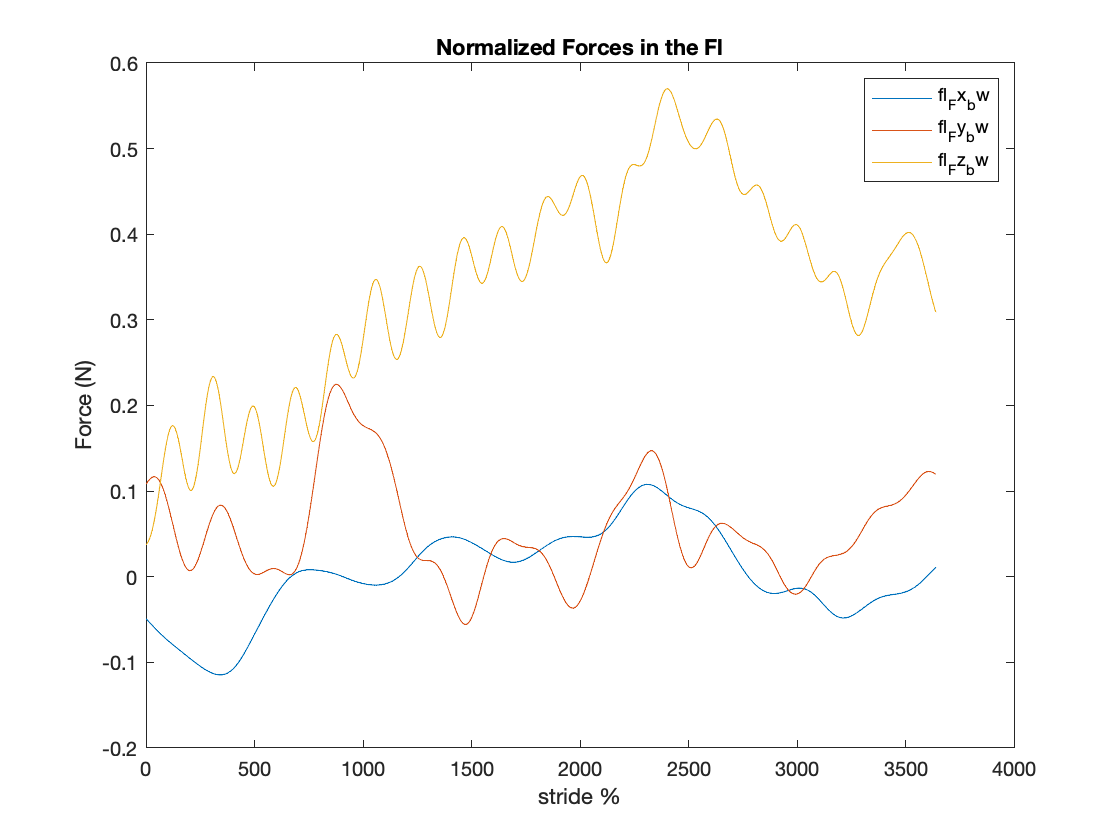



figure(5);
plot(fl_Fx_bw);
hold on
plot(fl_Fy_bw);
hold on
plot(fl_Fz_bw);
xlabel('stride %')
ylabel('Force (N)')
legend({'fl_Fx_bw', 'fl_Fy_bw', 'fl_Fz_bw'});
title('Normalized Forces in the Fl');
GraphName5 = append(walk_seq,'_Normalized_fl_Forces.pdf');
% saveas(gca,GraphName3)
ax1 = gca;
exportgraphics(ax1, GraphName5,'ContentType','vector');

**Normalizing forces for the Hl**

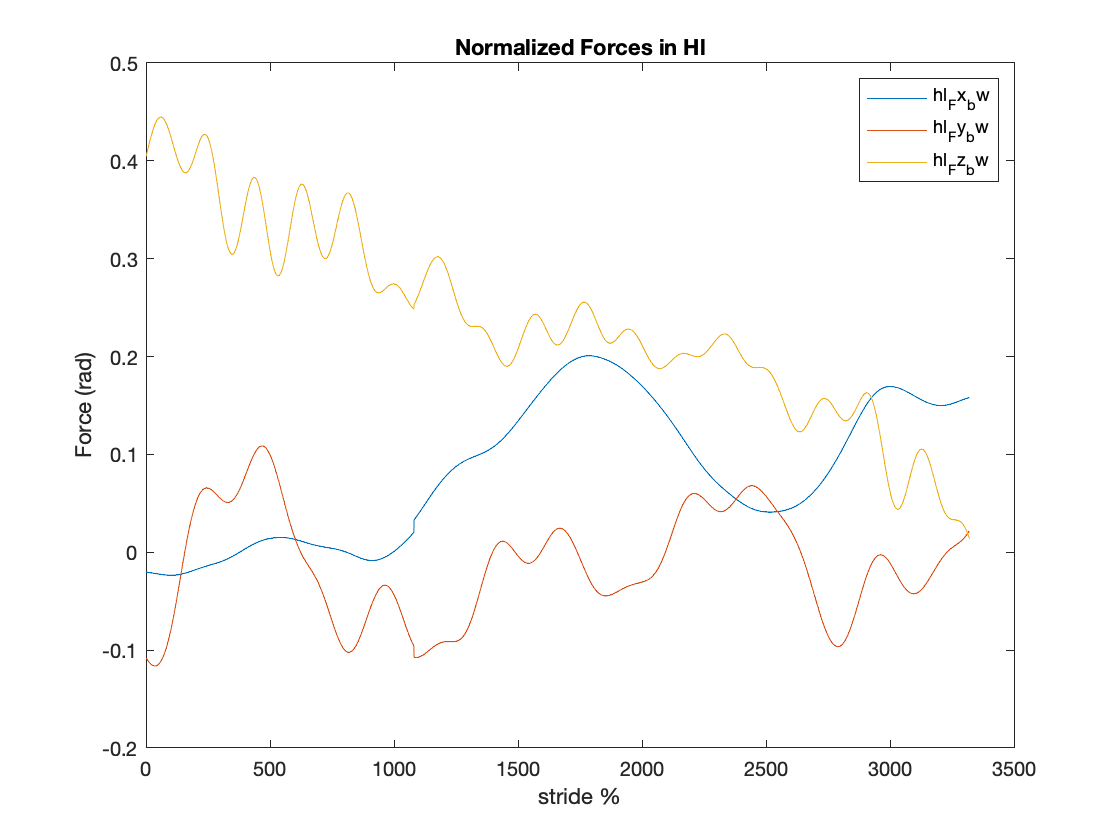

if HL ==1 
    hl_Fx_bw = f_x_hl ./bod_weight_N;
    hl_Fy_bw = f_y_hl ./bod_weight_N;
    hl_Fz_bw = f_z_hl ./bod_weight_N;
end

figure(6)
plot( hl_Fx_bw);
hold on
plot( hl_Fy_bw);
hold on
plot( hl_Fz_bw);
xlabel('stride %')
ylabel('Force (rad)')
legend({'hl_Fx_bw', 'hl_Fy_bw', 'hl_Fz_bw'});
title('Normalized Forces in Hl');
GraphName6 = append(walk_seq,'_Normalized_hl_Forces.pdf');
% saveas(gca,GraphName3)
ax1 = gca;
exportgraphics(ax1, GraphName6,'ContentType','vector');

## **Converting Force angles from radian to degrees**

This section converts the forces from the original results in radian to degree angles 

**Radians to degrees for Fl**

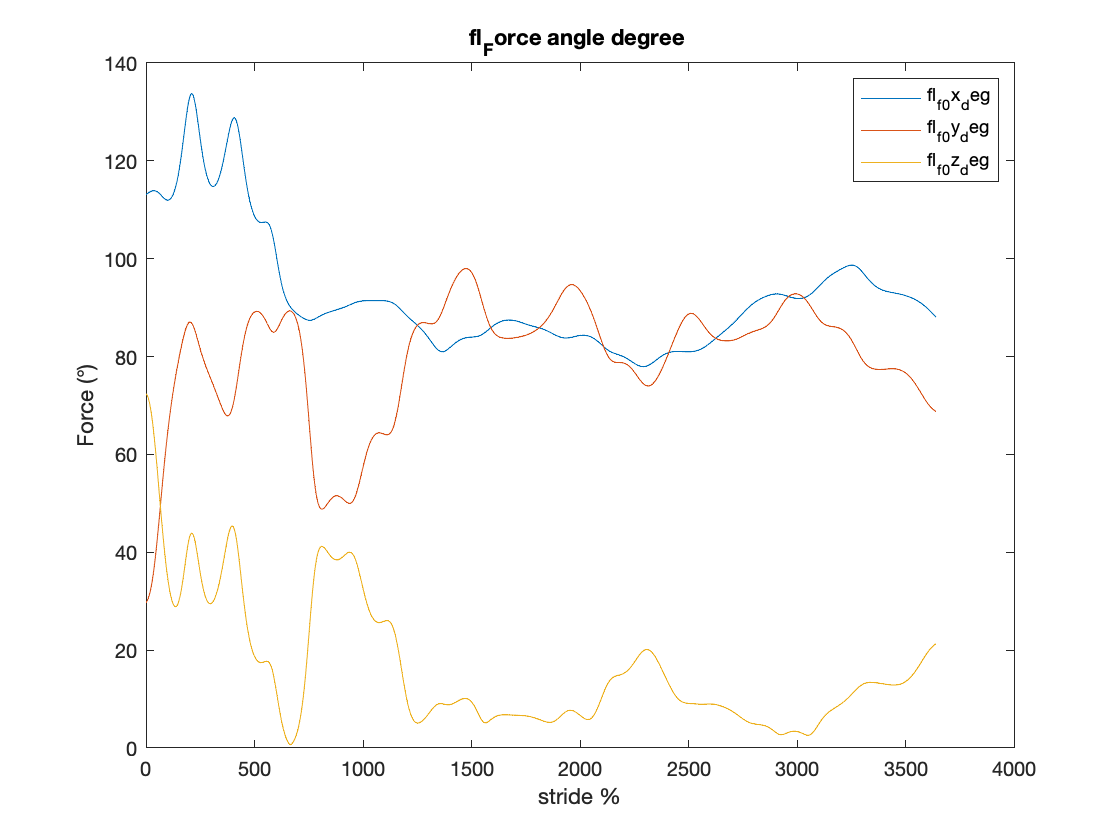

if FL ==1
    fl_f_0x_deg = rad2deg(fl_f_0x);
    fl_f_0y_deg = rad2deg(fl_f_0y);
    fl_f_0z_deg = rad2deg(fl_f_0z);
end 

figure(7)
plot( fl_f_0x_deg);
hold on
plot( fl_f_0y_deg);
hold on 
plot( fl_f_0z_deg);
xlabel('stride %');
ylabel('Force (°)');
legend({'fl_f_0x_deg', 'fl_f_0y_deg', 'fl_f_0z_deg'});
title('fl_Force angle degree ');
GraphName7 = append(walk_seq,'_fl_Force _0_deg.pdf');
% saveas(gca,GraphName3)
ax1 = gca;
exportgraphics(ax1, GraphName7,'ContentType','vector');

**Radians to degrees for Hl**

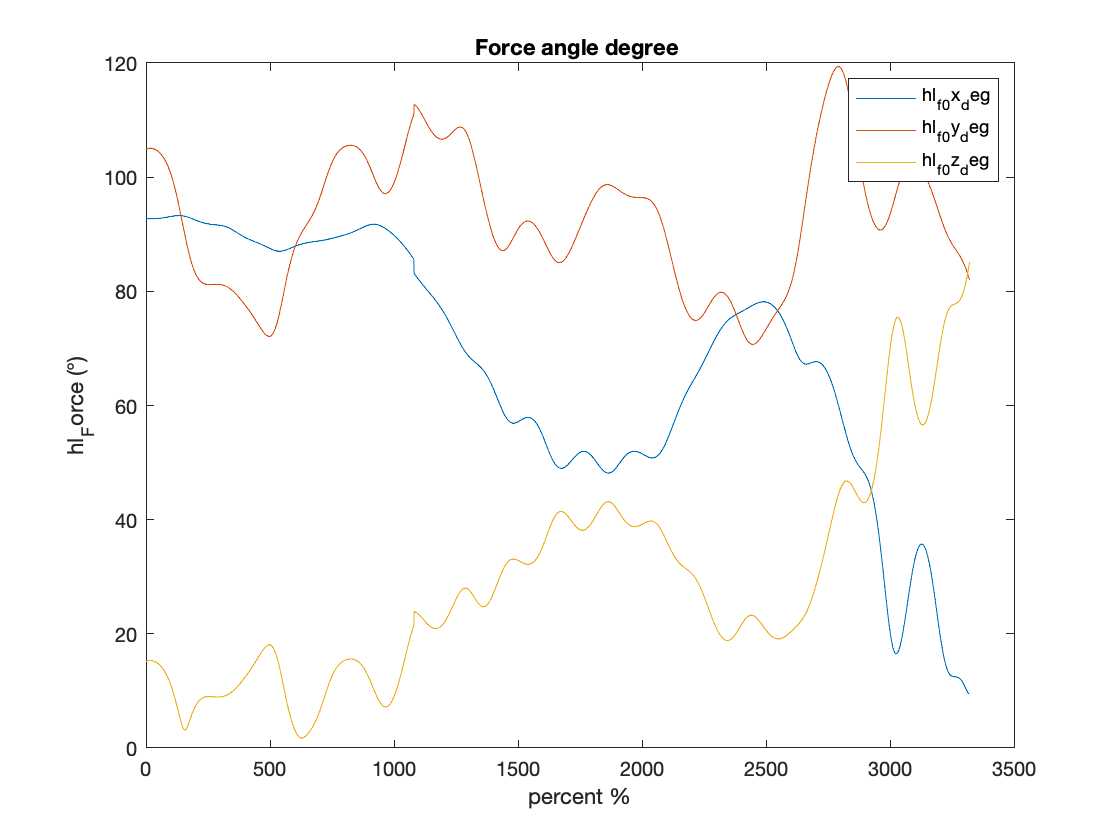

if HL ==1
    hl_f_0x_deg = rad2deg(hl_f_0x);
    hl_f_0y_deg = rad2deg(hl_f_0y);
    hl_f_0z_deg = rad2deg(hl_f_0z);
end 

figure(8)
plot( hl_f_0x_deg);
hold on
plot( hl_f_0y_deg);
hold on 
plot( hl_f_0z_deg);
xlabel('percent %');
ylabel('hl_Force (°)');
legend({'hl_f_0x_deg', 'hl_f_0y_deg', 'hl_f_0z_deg'});
title('Force angle degree ');
GraphName8 = append(walk_seq,'_hl_Force _0_deg.pdf');
% saveas(gca,GraphName3)
ax1 = gca;
exportgraphics(ax1, GraphName8,'ContentType','vector');

## Graphing Force  vs Percent Stride for FL and HL  (Fx, Fy, Fz)

Graphing Force for the x axis in the Fl  and Hl across the stride using normalized force

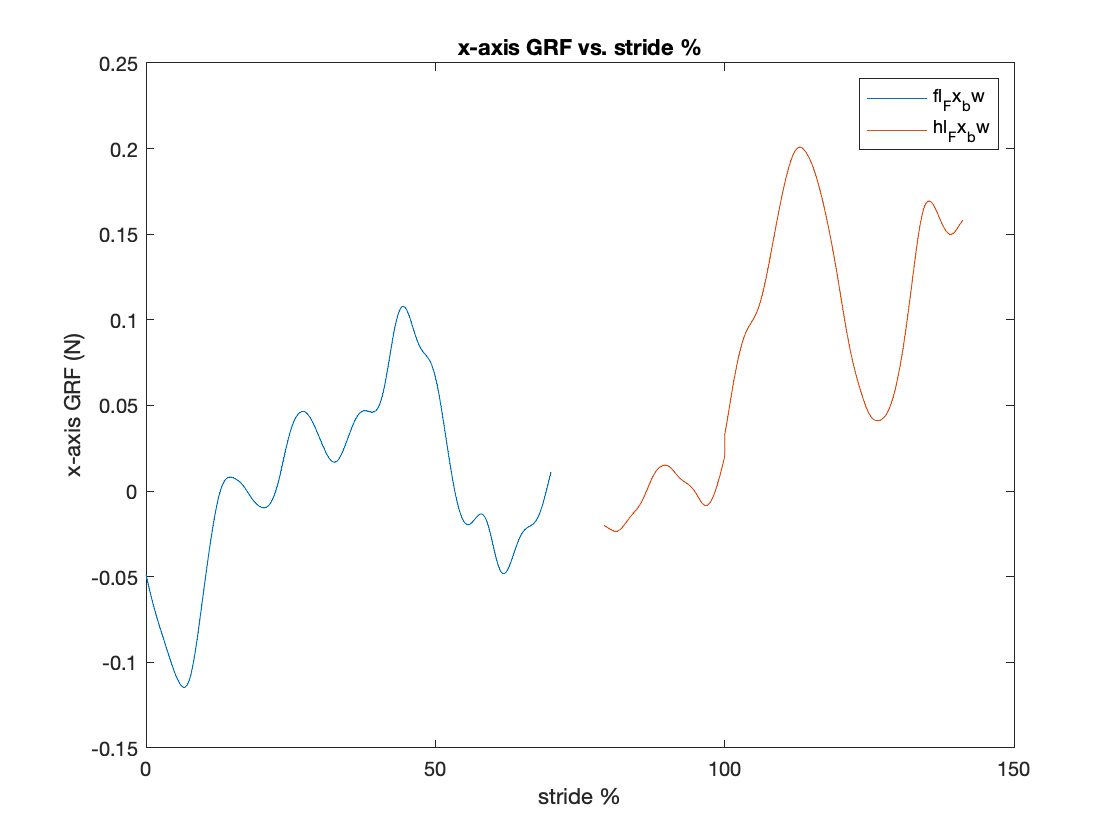

figure (9)
if s1_start_force_c  > 0 && s2_start_force_c > 0
    plot(p_stride_fl_f,fl_Fx_bw, p_stride_hl_f,hl_Fx_bw);
    xlim([0 150]);
else
    plot(p_stride_fl_f,fl_Fx_bw, p_stride_hl_f,hl_Fx_bw);
    xlim([0 100]);
end

xlabel('stride %');
ylabel('x-axis GRF (N)');
legend({'fl_Fx_bw', 'hl_Fx_bw'});
title('x-axis GRF vs. stride %');
GraphName9 = append(walk_seq,'_x-axis_pstride.pdf');
% saveas(gca,GraphName3)
ax1 = gca;
exportgraphics(ax1, GraphName9,'ContentType','vector');

**Graphing Force for the y-axis in the Fl  and Hl across the stride using normalized force**

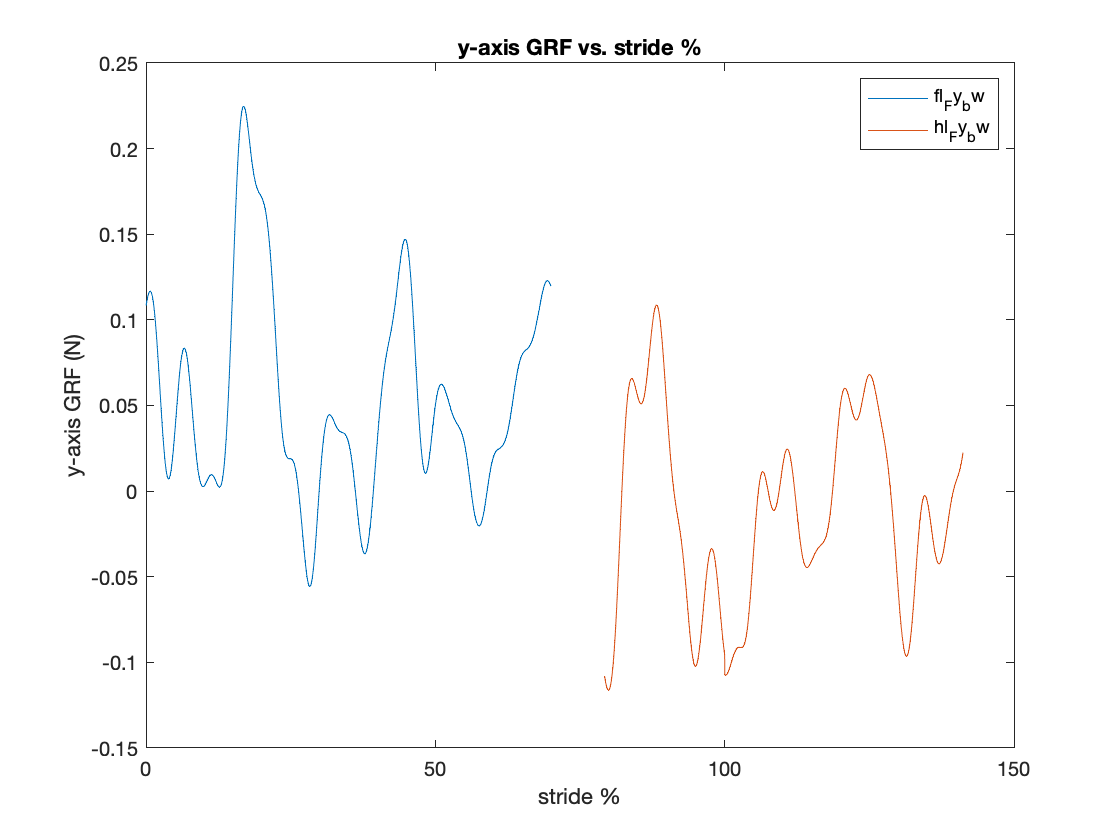

figure(10)
if s1_start_force_c  > 0 && s2_start_force_c > 0
    plot(p_stride_fl_f,fl_Fy_bw,p_stride_hl_f,hl_Fy_bw);
    xlim([0 150]);
else
    plot(p_stride_fl_f,fl_Fy_bw, p_stride_hl_f,hl_Fy_bw);
    xlim([0 100]);
end

title('y-axis GRF vs. stride %');
xlabel('stride %');
ylabel('y-axis GRF (N)');
legend({'fl_Fy_bw', 'hl_Fy_bw'});
GraphName10 = append(walk_seq,'_y-axis_pstride.pdf');
% saveas(gca,GraphName3)
ax1 = gca;
exportgraphics(ax1, GraphName10,'ContentType','vector');

**Graphing Force for the z-axis in the Fl  and Hl across the stride using normalized force**

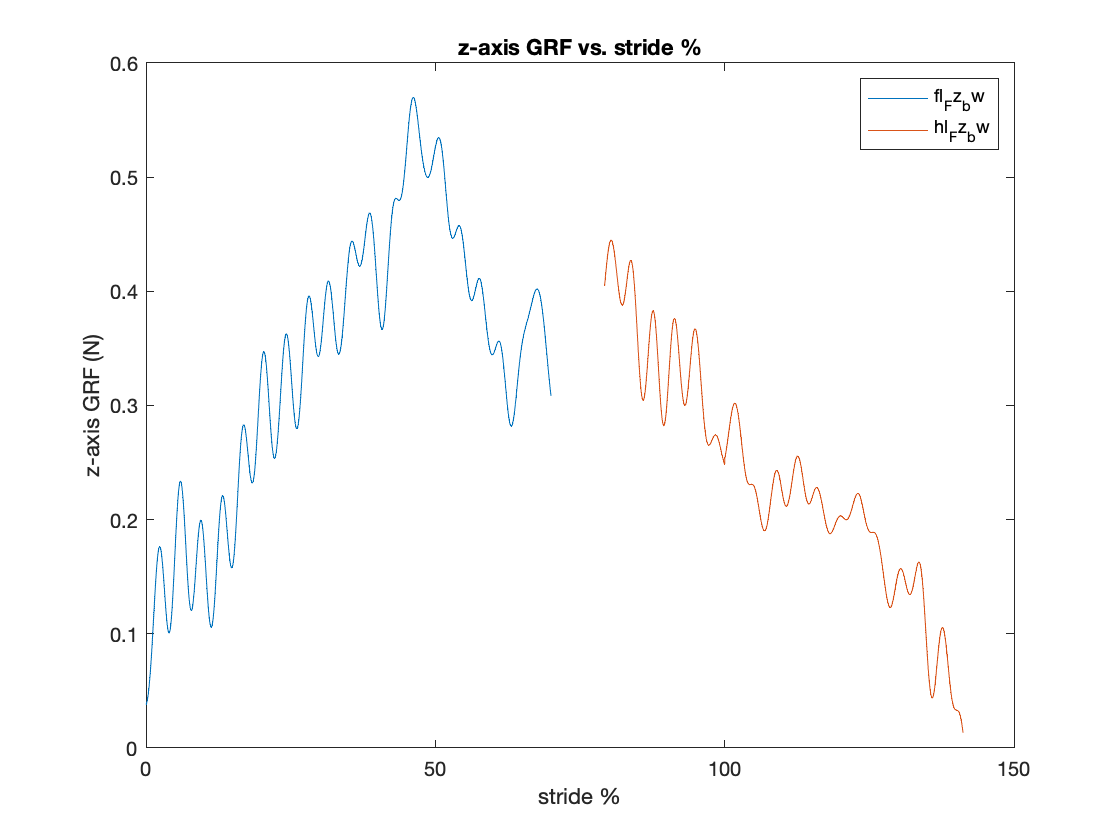

figure(11)
if s1_start_force_c  > 0 && s2_start_force_c > 0
    plot(p_stride_fl_f,fl_Fz_bw, p_stride_hl_f,hl_Fz_bw);
    xlim([0 150]);
else
    plot(p_stride_fl_f,fl_Fz_bw, p_stride_hl_f,hl_Fz_bw);
    xlim([0 100]);
end

title('z-axis GRF vs. stride %');
xlabel('stride %');
ylabel('z-axis GRF (N)');
legend({'fl_Fz_bw','hl_Fz_bw' });
GraphName11 = append(walk_seq,'_z-axis_pstride.pdf');
% saveas(gca,GraphName3)
ax1 = gca;
exportgraphics(ax1, GraphName11,'ContentType','vector');

**Graphing Force for the z-axis in the Fl  and Hl across the stride using normalized force**

figure(8)
if s1_start_force_c  > 0 && s2_start_force_c > 0
    plot(p_stride_fl_f,fl_Fr_bw, p_stride_hl_f,hl_Fr_bw)
    xlim([0 150])
else
    plot(p_stride_fl_f,fl_Fr_bw, p_stride_hl_f,hl_Fr_bw)
    xlim([0 100])
end

title('r-axis GRF vs. stride')
xlabel('stride %')
ylabel('r-axis GRF')
legend({'f_r_fl', 'f_r_hl'})
GraphName8 = append(walk_seq,'_r-axis_pstride.pdf')

GraphName8 = '20220429_ks1_walk3_r-axis_pstride.pdf'

% saveas(gca,GraphName3)
ax1 = gca

ax1 =   Axes (r-axis GRF vs. stride) with properties:

             XLim: [0 150]
             YLim: [0 120]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


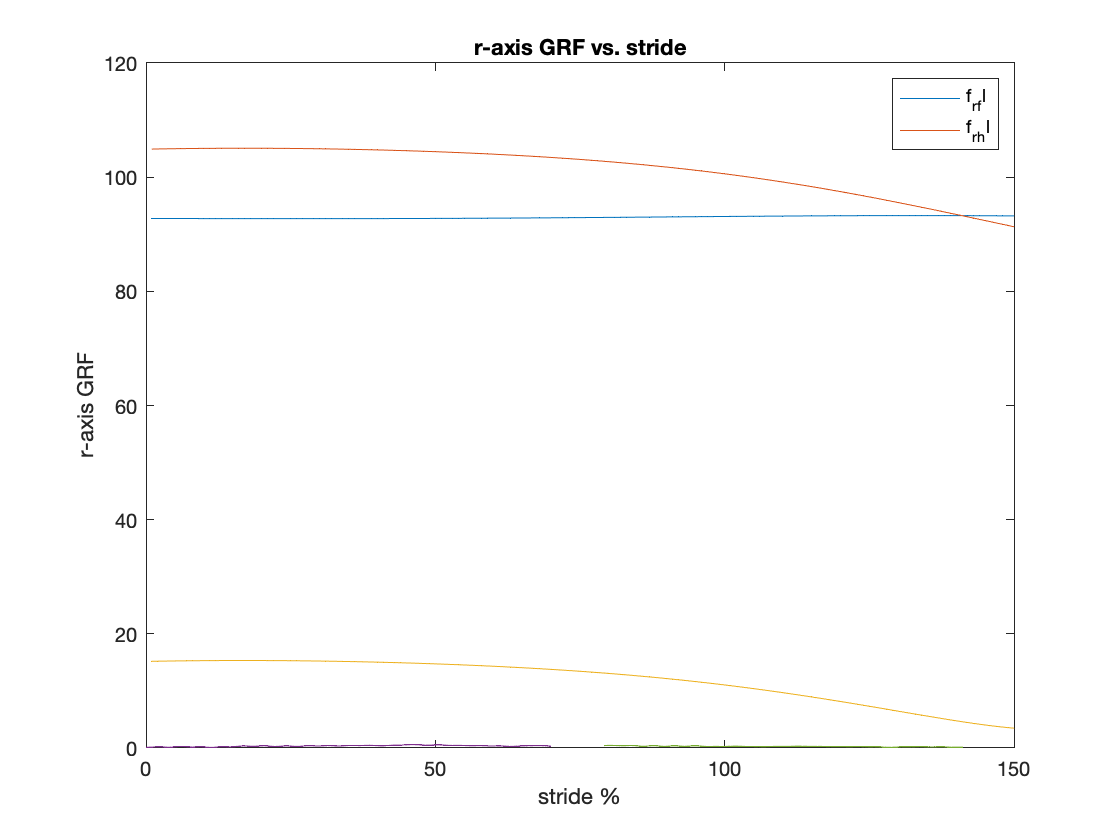

exportgraphics(ax1, GraphName8,'ContentType','vector')

## Calculation Force Plate A, B, C, D midpoints to find (Xmid, Ymid)

***(MIDPOINTS ARE NO LONGER NEEDED FOR THIS DATA ANALYSIS)***

**Formula to calculate midpoints **

(x_m, y_m) = ({x_1 + x_2 / 2}, {y_1 + y_2 / 2})\

**Pnt A  and C midppoints**

% AC_x_mid = ((pnt_A_x + pnt_C_x) ./2) 
% AC_y_mid = ((pnt_A_y + pnt_C_y) ./2)

**Pnt C  and D midpoints**

% CD_x_mid = ((pnt_C_x + pnt_D_x) ./2) 
% CD_y_mid = ((pnt_C_y + pnt_D_y) ./2)    

**absolute _COP X_mid , Ymid and Zmid**

% abs_COP_X_mid = ((pnt_C_x + pnt_D_x) ./2)
% abs_COP_Y_mid = ((pnt_A_y + pnt_C_y) ./2)
% abs_COP_Z_mid = ((pnt_A_z + pnt_D_z) ./2)


**Calculating and normalizing all digitazing points with the absolute COP midpoints (excepts the eye point)**

**COM**

% %center of mass
%     new_pnt_2 = [pt2_X, pt2_Y, pt2_Z] -[abs_COP_X_mid, abs_COP_Y_mid, abs_COP_Z_mid]  

**Fl points**

% if FL == 1     
%     
%     %shoulder 
%     new_pnt_3 = [pt3_X, pt3_Y, pt3_Z] -[abs_COP_X_mid, abs_COP_Y_mid, abs_COP_Z_mid]
% 
%     %elbow
%     new_pnt_4 = [pt4_X, pt4_Y, pt4_Z] -[abs_COP_X_mid, abs_COP_Y_mid, abs_COP_Z_mid]
% 
%     %wrist 
%     new_pnt_5 = [pt5_X, pt5_Y, pt5_Z] -[abs_COP_X_mid, abs_COP_Y_mid, abs_COP_Z_mid]
% 
%     %Longest phalange (fore L limb) (toe)
%     new_pnt_10 = [pt10_X, pt10_Y, pt10_Z] -[abs_COP_X_mid, abs_COP_Y_mid, abs_COP_Z_mid]  
% 
% end

**Hl points**

% if HL == 1     
%    
%     %Hip
%     new_pnt_6 = [pt6_X, pt6_Y, pt6_Z] -[abs_COP_X_mid, abs_COP_Y_mid, abs_COP_Z_mid]
% 
%     %Knee
%     new_pnt_7 = [pt7_X, pt7_Y, pt7_Z] -[abs_COP_X_mid, abs_COP_Y_mid, abs_COP_Z_mid]
% 
% 
%     %Torso/ankle 
%     new_pnt_8 = [pt8_X, pt8_Y, pt8_Z] -[abs_COP_X_mid, abs_COP_Y_mid, abs_COP_Z_mid]
% 
%     %Longest phalange (hind L limb) (toe)
%     new_pnt_10 = [pt9_X, pt9_Y, pt9_Z] -[abs_COP_X_mid, abs_COP_Y_mid, abs_COP_Z_mid]  
% 
% end


## Characterizing the Center of Pressure of the animal relative to the force plate.

Using the M values from igor, we can calculate where the center of that force is along the force plate. The force plate measures the force Fz and the associated Mx and My moments generated about the force plate's x and y axes. 

**Equation to find the X_cp **

    Xcp = - My / Fz 

**Equation to find the Y_cp**

    Ycp = Mx / Fz

### Calculating the X_cp and Y_cp for  FL 

if FL == 1 && s1_start_force_c  > 0
    
    %normalized moment points  (WE DONT NEED THIS FOR THIS ANALYSIS)
    m_y_fl_bw = m_y_fl ./bod_weight_N;
    m_x_fl_bw = m_x_fl ./bod_weight_N;
    m_z_fl_bw = m_z_fl ./bod_weight_N;

     %Calculating COP along the force plate for Fl
    fl_Xcp = (-m_y_fl ./ f_z_fl);   
    fl_Ycp = (m_x_fl ./ f_z_fl) ;    %these arge the origing COPs for the Fl
    fl_Zcp = 0;

    figure(11);
    plot (p_stride_fl_f,fl_Xcp, p_stride_fl_f,fl_Ycp);
    title('COP vs percent stride in FL');
    xlabel('stride %');
    ylabel('COP');
    legend({'fl_Xcp', 'fl_Ycp' });
    GraphName9 = append(walk_seq,'_fl_COP_pstride.pdf');
    % saveas(gca,GraphName3)
    ax1 = gca;
    exportgraphics(ax1, GraphName9,'ContentType','image');
 end

### Calculating the Xcp and Ycp for the HL

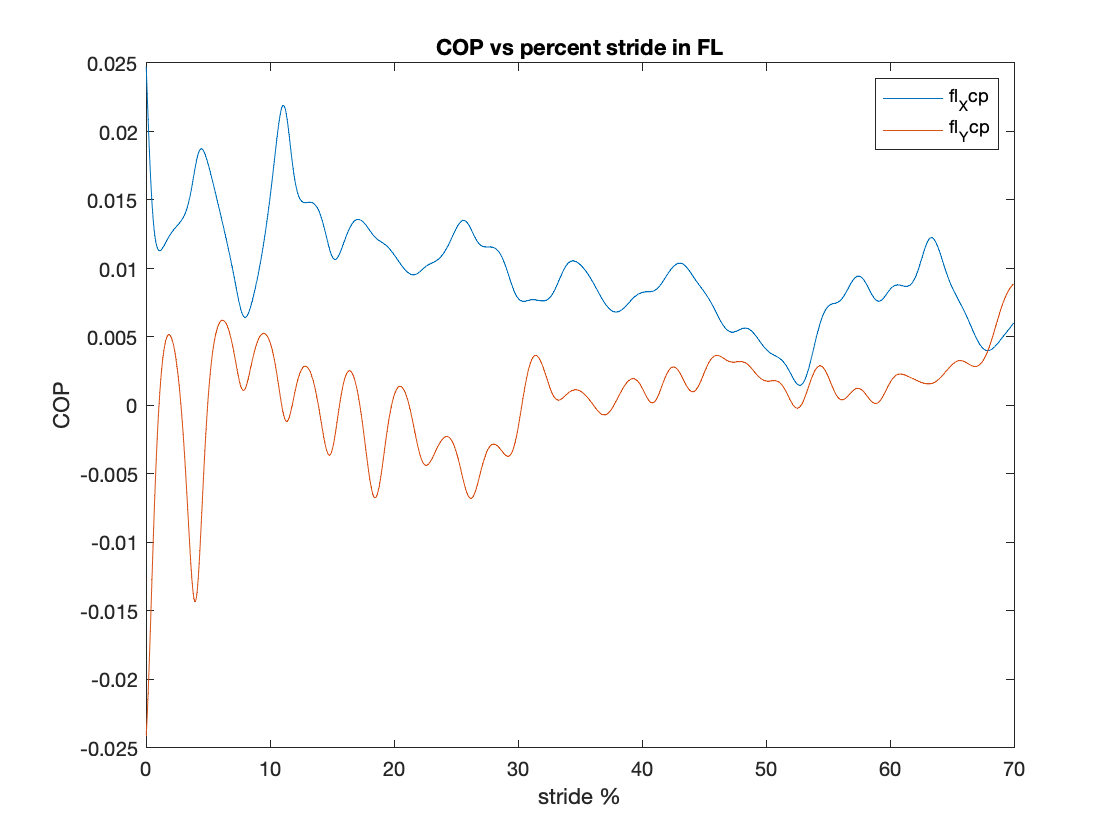

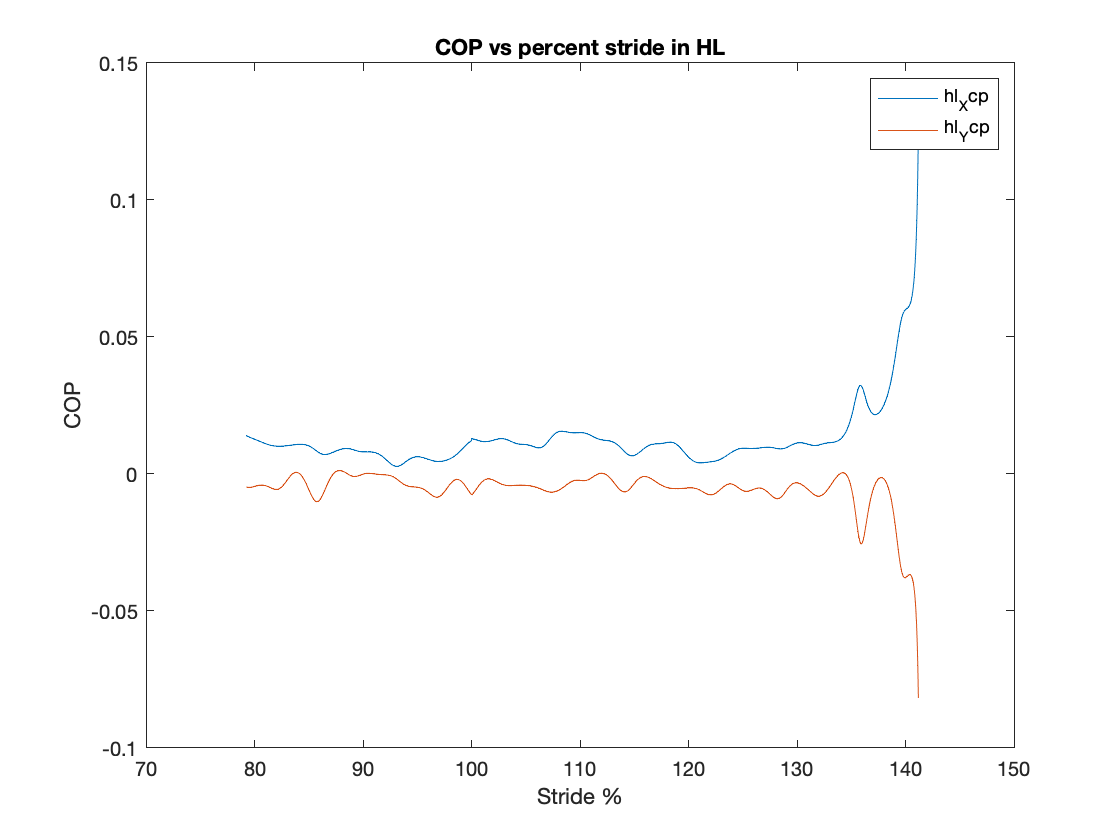

 if HL == 1 && s2_start_force_c  > 0
      
    %normalized moment points   (WE DONT NEED THIS FOR THIS ANALYSIS)
    m_y_hl_bw = m_y_hl ./bod_weight_N; 
    m_x_hl_bw = m_x_hl ./bod_weight_N;   
    m_z_hl_bw = m_z_hl ./bod_weight_N;

    %Calculating COP along the force plate for Fl
    hl_Xcp = (-m_y_hl ./ f_z_hl);
    hl_Ycp = (m_x_hl ./ f_z_hl);       %these arge the origing COPs for the Fl
    hl_Zcp = 0  ;

    figure(10) 
    plot (p_stride_hl_f,hl_Xcp, p_stride_hl_f,hl_Ycp);
    title('COP vs percent stride in HL');
    xlabel('Stride %');
    ylabel('COP')            ;                                                                                                                                                                                                                  
    legend({'hl_Xcp', 'hl_Ycp' });
    GraphName10= append(walk_seq,'_hl_COP_pstride.pdf');
    % saveas(gca,GraphName3)
    ax1 = gca;
    exportgraphics(ax1, GraphName10,'ContentType','image');
 end

## Calculating Delta change to obtain the COP progress along the video time

To know where in the video data the COP is, we first need to aling the Force plate data with the video frame. This part of the code does this.

% calculates the difference between the COP relative to the force plates
% for FL
     diff_Xcp_fl = diff(fl_Xcp) .*1000;    
     diff_Ycp_fl = diff(fl_Ycp) .*1000;
     diff_Zcp_fl = diff(fl_Zcp) .*1000;

% for HL
     diff_Xcp_hl = diff(hl_Xcp) .*1000;    
     diff_Ycp_hl = diff(hl_Ycp) .*1000;  
     diff_Zcp_hl = diff(hl_Zcp) .*1000;

**Calculating the COP forces relative to the force plate in Xcp for Fl**

 diff_Xcp_0_fl = [0; diff_Xcp_fl] ; 
 diff_xcp_array_fl = (diff_Xcp_0_fl)';    
 b_xcp_fl = 0

b_xcp_fl = 0

 delta_diff_xcp_fl = diff_xcp_array_fl;

%For loop that takes the values form the COP Xcp and returns the sum 
% of every two nubers and adds them to the main results in the array.

for index = 1:length(diff_xcp_array_fl)
    b_xcp_fl = b_xcp_fl + delta_diff_xcp_fl(index) ;    
    delta_diff_xcp_fl(index )= b_xcp_fl;

end
d_diff_xcp_array_fl = delta_diff_xcp_fl'  

d_diff_xcp_array_fl =          0
   -0.4885
   -0.9765
   -1.4632
   -1.9473
   -2.4280
   -2.9044
   -3.3754
   -3.8401
   -4.2977


**Calculating the COP forces relative to the force plate in Ycp for Fl **

diff_Ycp_0_fl = [0; diff_Ycp_fl] ; 
diff_ycp_array_fl = (diff_Ycp_0_fl)';    
b_ycp_fl = 0

b_ycp_fl = 0

delta_diff_ycp_fl = diff_ycp_array_fl;

%For loop that takes the values form the COP Xcp and returns the sum 
% of every two nubers and adds them to the main results in the array.

for index = 1:length(diff_ycp_array_fl)
    b_ycp_fl = b_ycp_fl + delta_diff_ycp_fl(index) ;    
    delta_diff_ycp_fl(index )= b_ycp_fl;

end
d_diff_ycp_array_fl = delta_diff_ycp_fl'

d_diff_ycp_array_fl =          0
    0.3172
    0.6544
    1.0109
    1.3862
    1.7795
    2.1900
    2.6170
    3.0594
    3.5164


**Calculating the COP forces relative to the force plate in Xcp for Hl**

 diff_Xcp_0_hl = [0; diff_Xcp_hl] ; 
 diff_xcp_array_hl = (diff_Xcp_0_hl)';    
 b_xcp_hl = 0

b_xcp_hl = 0

 delta_diff_xcp_hl = diff_xcp_array_hl;

%For loop that takes the values form the COP Xcp and returns the sum 
% of every two nubers and adds them to the main results in the array.

for index = 1:length(diff_xcp_array_hl)
    b_xcp_hl = b_xcp_hl + delta_diff_xcp_hl(index) ;    
    delta_diff_xcp_hl(index )= b_xcp_hl;

end
d_diff_xcp_array_hl = delta_diff_xcp_hl'

d_diff_xcp_array_hl =          0
   -0.0375
   -0.0746
   -0.1113
   -0.1476
   -0.1835
   -0.2190
   -0.2541
   -0.2889
   -0.3234


**Calculating the COP forces relative to the force plate in Ycp for Hl **

diff_Ycp_0_hl = [0; diff_Ycp_hl] ; 
diff_ycp_array_hl = (diff_Ycp_0_hl)';    
b_ycp_hl = 0

b_ycp_hl = 0

delta_diff_ycp_hl = diff_ycp_array_hl;

%For loop that takes the values form the COP Xcp and returns the sum 
% of every two nubers and adds them to the main results in the array.

for index = 1:length(diff_ycp_array_hl)
    b_ycp_hl = b_ycp_hl + delta_diff_ycp_hl(index) ;    
    delta_diff_ycp_hl(index )= b_ycp_hl;

end
d_diff_ycp_array_hl = delta_diff_ycp_hl'

d_diff_ycp_array_hl =          0
   -0.0203
   -0.0388
   -0.0557
   -0.0709
   -0.0844
   -0.0962
   -0.1064
   -0.1151
   -0.1221


This section creates a time array for Xcp, Ycp and Zcp COP that converts the frames into time in seconds for the Fl

if FL==1 
     %Xcp_fl array 
    [total_rows_xcp_fl, ~ ]= size(d_diff_xcp_array_fl);         %gets the total size of the Xcp COP
    xcp_f_t0_fl = (1:total_rows_xcp_fl)' ./10000;        %array of frames relative to time

    %Ycp_fl array 
    [total_rows_ycp_fl, ~ ]= size(d_diff_ycp_array_fl);         %gets the total size of the Xcp COP
    ycp_f_t0 = (1:total_rows_ycp_fl)' ./10000;   

    %Xcp for fl
    new_diff_Xcp_fl= d_diff_xcp_array_fl(40:40:end);         %gets the COP relatively to the time the force plate is in contact 
   [new_Xcp_time_s_fl, ~] = size(new_diff_Xcp_fl);

    %Ycp for fl
    new_diff_Ycp_fl= d_diff_ycp_array_fl(40:40:end);         %gets the COP relatively to the time the force plate is in contact 
    [new_Ycp_time_s_fl, ~] = size(new_diff_Ycp_fl);

    %Zcp for fl
    new_diff_Zcp_fl= diff_Zcp_fl(40:40:end);         %gets the COP relatively to the time the force plate is in contact  
    [new_Zcp_time_s_fl, ~] = size(new_diff_Zcp_fl);
end



    new_fl_t_only_f_sec = fl_t_only_f_sec(1:40:end); %NOT NEEDED!!
     n_fl_t_only = size(new_fl_t_only_f_sec)

n_fl_t_only =     91     1



     new_hl_t_only_f_sec = hl_t_only_f_sec(1:40:end); 
         n_hl_t_only = size(new_hl_t_only_f_sec)

n_fl_t_only =     83     1


This section creates a new variable that takes the COP for the Fl (pt10) from the video datavalues and syncronizes it with the new forces Xcp, Ycp and Zcp in time value. Pt10 is when the longest toe first touches the force plate 

pt10_fl_xcp =    11.7252
   11.7301
   11.5507
   10.9591
   10.7131
   10.6167
   10.6010
   10.6155
   10.5937
   10.6071


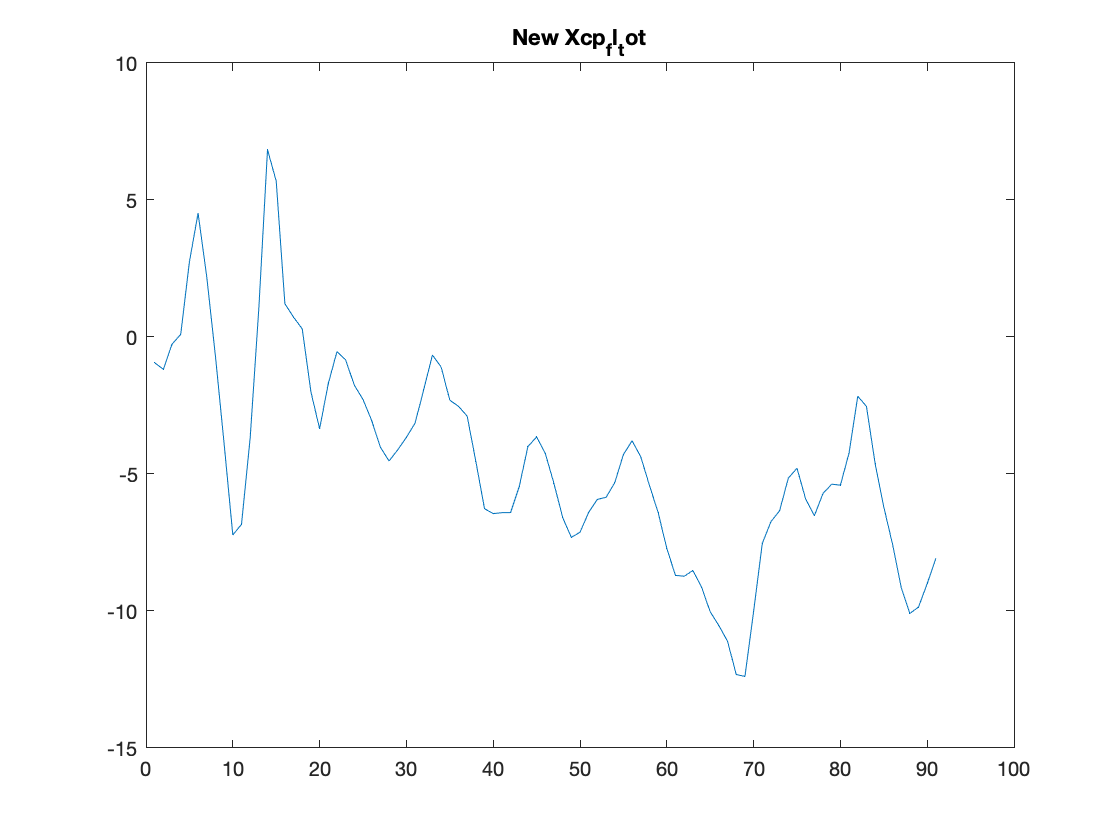

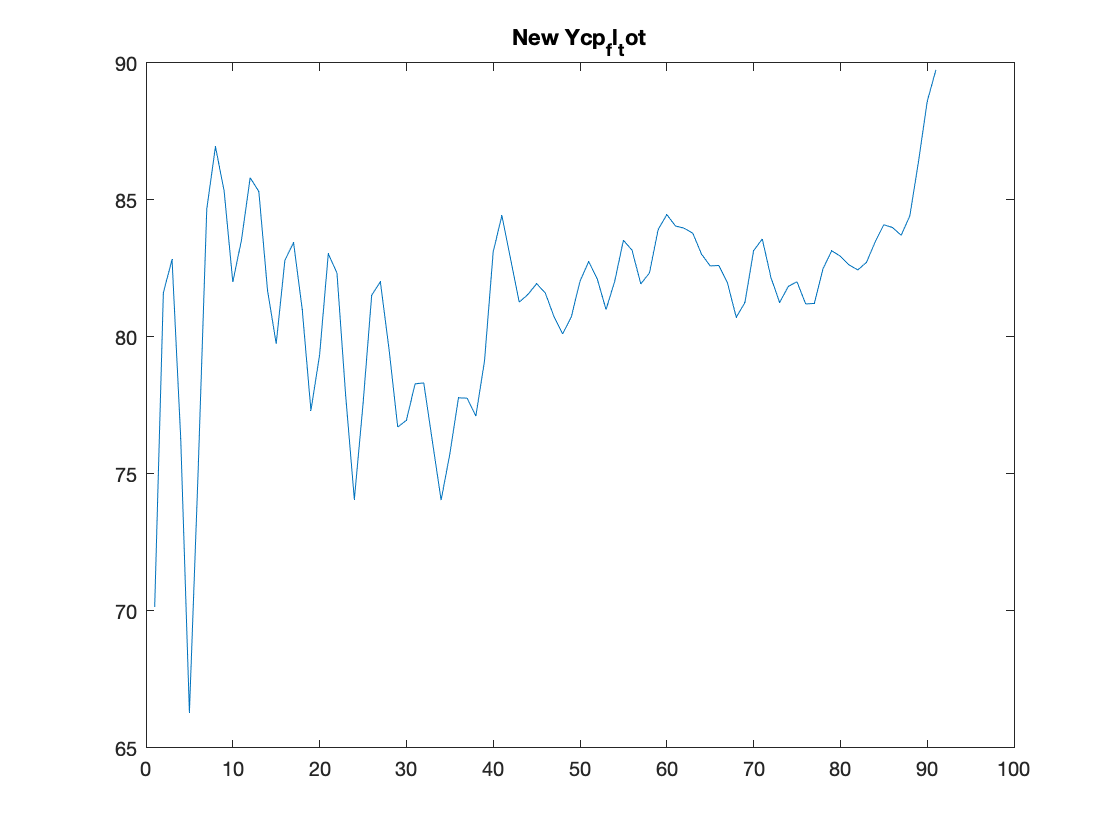

pt10_fl_zcp =   119.3328
  119.7308
  120.1729
  121.1950
  121.5430
  121.5367
  121.5617
  121.5612
  121.5160
  121.4775


if FL ==1

    %pt10 Longest phalange (fore L limb)
    %Xcp
    pt10_fl_xcp = pt10_X(1:new_Xcp_time_s_fl )
    pt10_fl_Xcp_tot =pt10_fl_xcp + new_diff_Xcp_fl;
    figure
    plot( pt10_fl_Xcp_tot)
     title('New Xcp_fl_tot');                                                                                                                                                                                                              
   
     %Ycp
    pt10_fl_ycp = pt10_Y(1:new_Ycp_time_s_fl);
    pt10_fl_Ycp_tot = pt10_fl_ycp + new_diff_Ycp_fl;
    figure
    plot(pt10_fl_Ycp_tot);
    title('New Ycp_fl_tot')

    %Zcp
    pt10_fl_zcp = new_pt10_Z_

end

This section creates a time array for Xcp, Ycp and Zcp COP that converts the frames into time in seconds for the Fl

 if HL==1  
    %Xcp_hl array
    [total_rows_xcp_hl, ~ ]= size(d_diff_xcp_array_hl);               %gets the total size of the Xcp COP
    xcp_f_t0_hl = (1:total_rows_xcp_hl)' ./10000;        %array of frames relative to time

    %Ycp_hl array
    [total_rows_ycp_hl, ~ ]= size(d_diff_ycp_array_hl);               %gets the total size of the Xcp COP
    ycp_f_t0_hl = (1:total_rows_ycp_hl)' ./10000;
    
    
    %Xcp for Hl
    new_diff_Xcp_hl= d_diff_xcp_array_hl(40:40:end);         %gets the COP relatively to the time the force plate is pressed?
    [new_Xcp_time_s_hl, ~] = size(new_diff_Xcp_hl);

    %Ycp for Hl
    new_diff_Ycp_hl= d_diff_ycp_array_hl(40:40:end);         %gets the COP relatively to the time the force plate is pressed?
    [new_Ycp_time_s_hl, ~] = size(new_diff_Ycp_hl);

    %Zcp for Hl
    new_diff_Zcp_hl= diff_Zcp_hl(40:40:end);         %gets the COP relatively to the time the force plate is pressed?
    [new_Zcp_time_s_hl, ~] = size(new_diff_Zcp_hl);

 end 

This section creates a new variable that takes the COP for the Hl (pt9) from the video datavalues and syncronizes it with the new forces Xcp, Ycp and Zcp in time value. Pt9 is when the longest toe first touches the force plate 

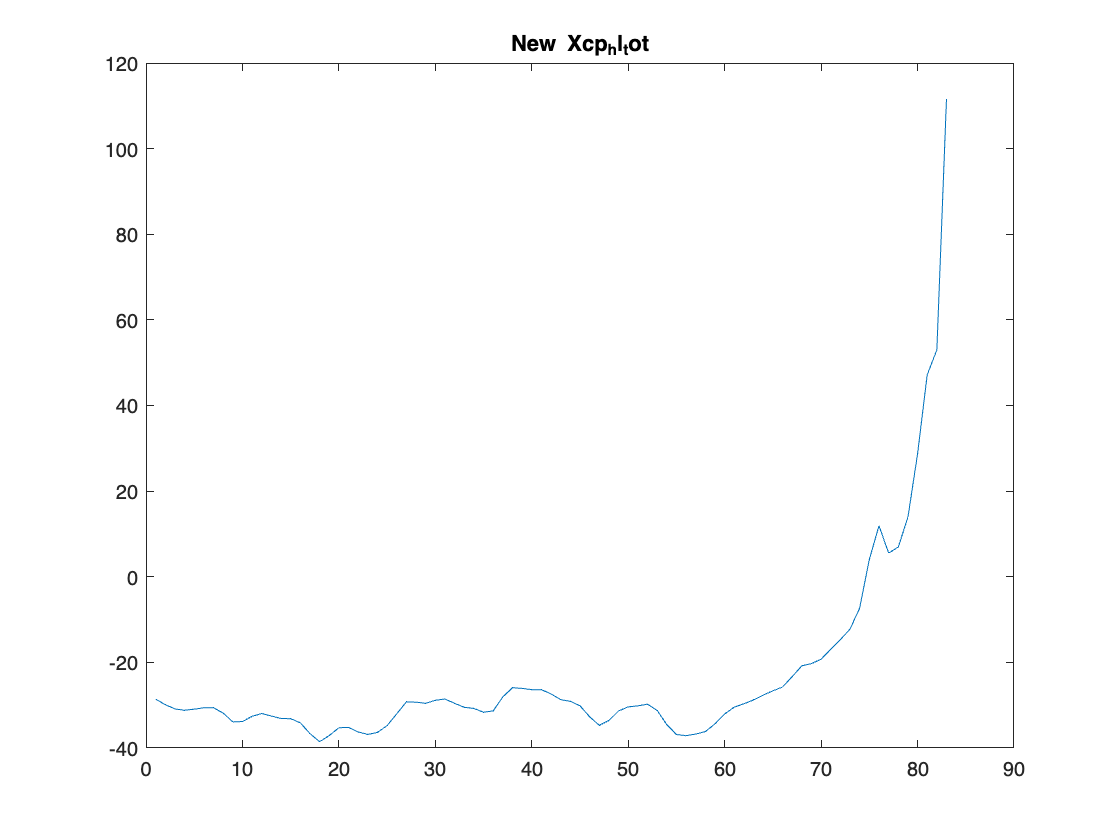

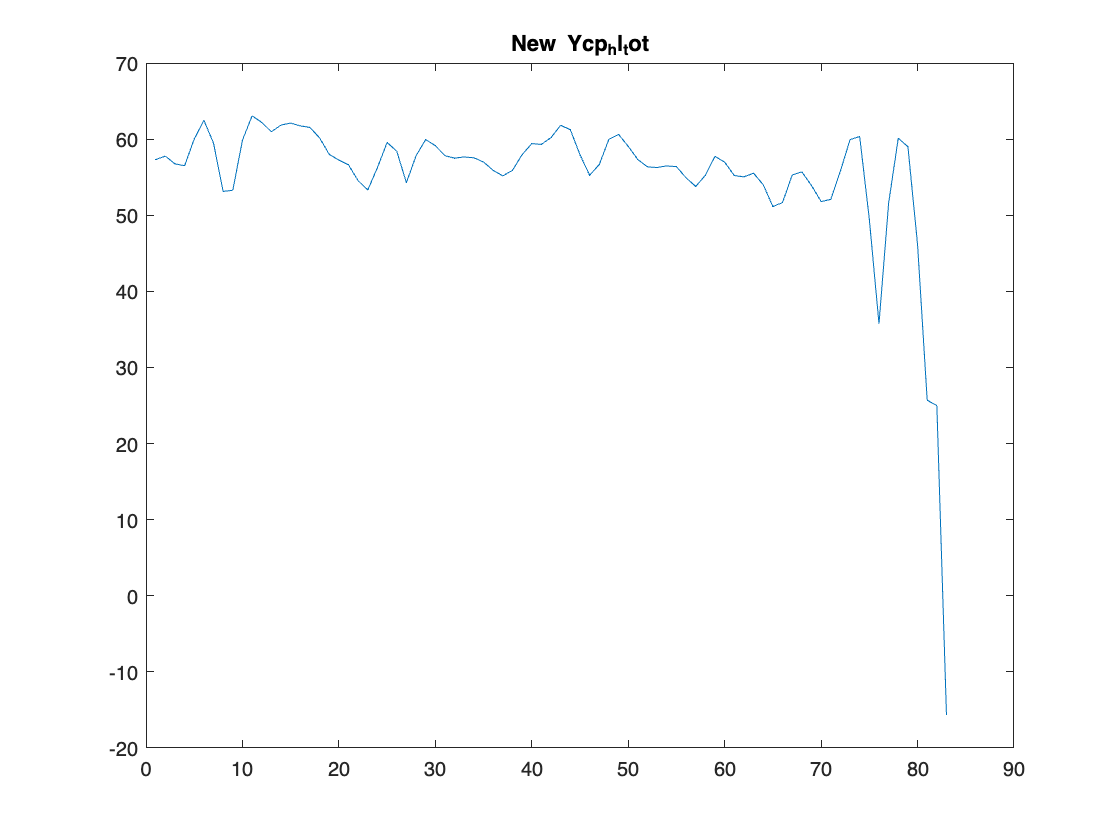

pt9_hl_zcp =   121.3117
  121.3744
  121.4673
  121.4673
  121.6308
  121.5723
  121.5403
  121.5410
  121.5341
  121.5239


if HL ==1

    %pt9 Longest phalange (hind L limb)
    %Xcp
    pt9_hl_xcp = pt9_X(1:new_Xcp_time_s_hl );
    pt9_hl_Xcp_tot =pt9_hl_xcp + new_diff_Xcp_hl;
    figure
    plot(pt9_hl_Xcp_tot)
    title('New Xcp_hl_tot')

    %Ycp
    pt9_hl_ycp = pt9_Y(1:new_Ycp_time_s_hl );
    pt9_hl_Ycp_tot =pt9_hl_ycp + new_diff_Ycp_hl;
    figure
    plot(pt9_hl_Ycp_tot)
    title('New Ycp_hl_tot')

    %Zcp
    pt9_hl_zcp = new_pt9_Z_
end

# Analysing Joint Torque Variation In Forward Locomotion

This code will go through:

- Creating new set points for  Fl that are normalized to be in a same sized array and will only contain the data values from when only the Fl is in contact with the force plate

- Creating new set points for Hl that are normalized to be in a same sized array and will only contain the data values from when only the Hl is in contact with the force plate

- Use the new set points to calculate for the  moments arm ( r ) in oder to  calulate for the joint toque   

- Calulate for f_r (force_r results) using the data values from the force plate data sets

- Once (r) is obtained, use the results to calculate for joint torque using the equation  **t = r * f_r**

**Calculating for Torque formula **

**t = r * f_r**

t =torque

r =moment arms

f_r = force int results 

## **Calculating r**

In order to calculate for joint torque, we must first calculate for r for each of the pts for FL and Hl. To do so, we need to create a variable x_0 that holds the datavalues required for each of the pts. 

**Identifying r's for the FL **

- rs = shoulder point(pt3)

- re = elbow point(pt4)

- rw = wrist point(pt5)

**Identifying r's for the HL **

- rh = hip point(pt6)

- rk = elbow point(pt7)

- ra = ankle point(pt8)

**Formula to calculate for r (**Point-Line Distance--3-Dimensional)

**r = **`(x0 - x1) * (x0-x2)`** / | x2 - x1|**

r= arms moment

x0 = the normalized new pts (new_pt'_'_x0_fl) 

x1= COP normalized new ptys (pt10 for Fl, pt9 for Hl)

x2 = normalized force pts(both for the Fl and Hl)

**momens arm variables   *****(THIS SECTION WILL NOT BE USED FOR THE CODE)***

% %new_pt10_Z_fl=pt10_Z(1:new_pt10_Z_)  % use to reshape the number of elements of the array from 268x1 to 101x1
% 
% %eye matrix variable
% x2_fl = [pt10_fl_xcp , pt10_fl_ycp, new_pt1_Z_] 

Calculating variables for the Fl 

% %shoulder (rs)
% pt3_x0_fl = [new_pt3_X_, new_pt3_Y_, new_pt3_Z_ ]
% 
% %elbow (re)
% pt4_x0_fl = [new_pt4_X_, new_pt4_Y_, new_pt4_Z_ ]
% 
% %wrist (rw)
% pt5_x0_fl = [new_pt5_X_, new_pt5_Y_, new_pt5_Z_]

**Calculating rs for the fl pt 3**

% %calculating cross()
% 
% c_A = pt3_x0_fl - x1_fl
% 
% c_B = pt3_x0_fl - x2_fl
% 
% c_result = cross(c_A, c_B)
% 
% c_C = x2_fl - x1_fl
% 
% %d_fl = abs(c_result)./ (abs(x2_fl - x1_fl))
% 
% %d_x = abs( c_C)
% 
% %d_r_fl = d_fl ./ d_x


This section will normalized the forces in a same size array that sincronizes the video frame time to force plate time and will create a variable for x_0, x_1, x_2 for the Fl

%x1 COP (fl toe)
x1_fl = [pt10_fl_xcp, pt10_fl_ycp, pt10_fl_zcp]

x1_fl =    11.7252   51.2932  119.3328
   11.7301   53.0279  119.7308
   11.5507   54.7568  120.1729
   10.9591   55.3831  121.1950
   10.7131   56.1980  121.5430
   10.6167   56.6211  121.5367
   10.6010   56.6407  121.5617
   10.6155   56.6502  121.5612
   10.5937   56.6335  121.5160
   10.6071   56.6466  121.4775



%X2
new_fx_fl_norm= f_x_fl(1:40:end);
new_fy_fl_norm= f_y_fl(1:40:end);
new_fz_fl_norm= f_z_fl(1:40:end);

%x2 new matrix array
new_x2_fl_norm =  [new_fx_fl_norm, new_fy_fl_norm, new_fz_fl_norm];


**Calculating new pts, x0, rs and jointtorque for the shoulder (pt3)**

%normalizing new points  for rs (pt3)
new_pt3_x_norm = new_pt3_X_- pt10_fl_xcp;
new_pt3_y_norm = new_pt3_Y_- pt10_fl_ycp;
new_pt3_z_norm = new_pt3_Z_- pt10_fl_zcp;

%pt3 new matrix array
new_pt3_x0_fl = [new_pt3_x_norm, new_pt3_y_norm, new_pt3_z_norm];

%finding rs
pt3_c_A = new_pt3_x0_fl - x1_fl;
pt3_c_B = new_pt3_x0_fl - new_x2_fl_norm;
pt3_c_result = cross(pt3_c_A, pt3_c_B);

rs_fl = abs(pt3_c_result)./ (abs(new_x2_fl_norm - x1_fl));

%normalizing fr to calculate for joint torque
new_fr_fl_norm= f_r_fl(1:40:end);

%Calculating joint torque
rs_torque = rs_fl .* new_fr_fl_norm;

rs_torque_x = rs_torque(:, 1);
rs_torque_y = rs_torque(:, 2);
rs_torque_z = rs_torque(:, 3);

%converting r from cartician coordinates to spherical coordinates to obtain
%r
[rs_torque_azi, rs_torque_elev, rs_torque_r] = cart2sph(rs_torque_x, rs_torque_y, rs_torque_z) ;


**Calculating new pts, x0, re and jointtorque for the elbow (pt4)**


%normalizing new points  for re (pt4)
new_pt4_x_norm = new_pt4_X_ - pt10_fl_xcp;
new_pt4_y_norm = new_pt4_Y_ - pt10_fl_xcp;
new_pt4_z_norm = new_pt4_Z_ - pt10_fl_xcp;

%pt4 new matrix array
new_pt4_x0_fl = [new_pt4_x_norm, new_pt4_y_norm, new_pt4_z_norm];


%finding re
pt4_c_A = new_pt4_x0_fl - x1_fl;
pt4_c_B = new_pt4_x0_fl - new_x2_fl_norm;
pt4_c_result = cross(pt4_c_A, pt4_c_B);

re_fl = abs(pt4_c_result)./ (abs(new_x2_fl_norm - x1_fl))

re_fl =    29.7973   54.2647    9.7371
   38.0906   53.8954   10.2052
   46.5743   51.5159   10.2647
   44.3843   49.1950    9.9103
   48.2455   47.3058    9.7388
   50.4929   45.9524    9.5884
   50.5208   45.0529    9.3970
   50.5001   44.8972    9.3657
   50.7232   44.3131    9.2397
   50.2388   44.0797    9.2018



% %finding force int for torque
% new_fr_fl_norm= f_r_fl(1:40:end);   (dont need this because it has been stablish in pt3)

%Calculating joint torque
re_torque = re_fl .* new_fr_fl_norm;

re_torque_x = re_torque(:, 1);
re_torque_y = re_torque(:, 2);
re_torque_z = re_torque(:, 3);

%converting r from cartician coordinates to spherical coordinates to obtain
%r
[re_torque_azi, re_torque_elev, re_torque_r] = cart2sph(re_torque_x, re_torque_y, re_torque_z) ;


**Calculating new pts, x0, re and joint torque for the wrist (pt5)**


%setting points for rw
new_pt5_x_norm = new_pt5_X_ - pt10_fl_xcp;
new_pt5_y_norm = new_pt5_Y_ - pt10_fl_xcp;
new_pt5_z_norm = new_pt5_Z_ - pt10_fl_xcp;


%pt5 new matrix array
new_pt5_x0_fl = [new_pt5_x_norm, new_pt5_y_norm, new_pt5_z_norm];


%finding rw
pt5_c_A = new_pt5_x0_fl - x1_fl;
pt5_c_B = new_pt5_x0_fl - new_x2_fl_norm;
pt5_c_result = cross(pt5_c_A, pt5_c_B);

rw_fl = abs(pt5_c_result)./ (abs(new_x2_fl_norm - x1_fl))

rw_fl =    36.0408   40.3273    7.1020
   38.8096   39.2987    7.3353
   43.4658   37.3831    7.3594
   38.4169   34.9353    6.9813
   36.1169   33.8541    6.9571
   37.1392   33.4824    6.9838
   35.7428   32.9083    6.8727
   33.7902   32.6901    6.8420
   34.4035   32.2359    6.7405
   34.8919   32.0139    6.6952



% %finding force int for torque
% new_fr_fl_norm= f_r_fl(1:40:end);

%Calculating joint torque
rw_torque = rw_fl .* new_fr_fl_norm;

rw_torque_x = rw_torque(:, 1);
rw_torque_y = rw_torque(:, 2);
rw_torque_z = rw_torque(:, 3);

%converting r from cartician coordinates to spherical coordinates to obtain
%r
[rw_torque_azi, rw_torque_elev, rw_torque_r] = cart2sph(rw_torque_x, rw_torque_y, rw_torque_z) ;




**Displaying torque_r  for all points in  Fl (rs,re,rw)**

figure (80)
plot(rs_torque_r)
hold on
plot(re_torque_r)
hold on
plot(rw_torque_r)
title('Torque r in FL');  
xlabel(' points');
ylabel('torque (N/mm)');
legend({'rs_torque_r', 're_torque_r', 'rw_torque_r' });

**Displaying force direction in quiver plot for the Fl**

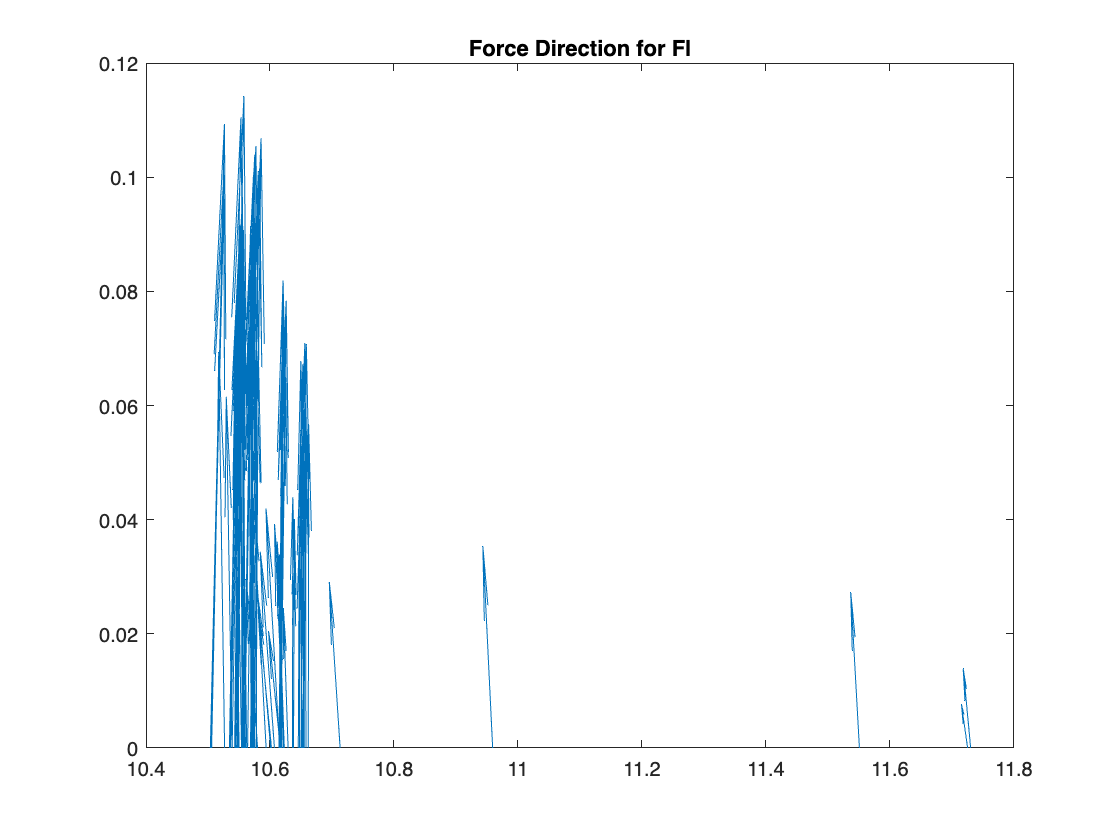

y_array = zeros([91, 1]);
x_quiv = pt10_fl_xcp;
u_quiv = new_fx_fl_norm;
v_quiv = new_fz_fl_norm; 
figure
quiver(x_quiv, y_array, u_quiv, v_quiv )
title('Force Direction for Fl')

This section will normalized the forces in a same size array that sincronizes the video frame time to force plate time and will create a variable for x_0, x_1, x_2 for the Hl

 %x1 COP (hl toe)
x1_hl = [pt9_hl_xcp, pt9_hl_ycp, pt9_hl_zcp]

x1_hl =   -27.3257   57.0864  121.3117
  -27.3664   57.0831  121.3744
  -27.3492   57.1130  121.4673
  -27.3589   57.0467  121.4673
  -27.3456   57.1355  121.6308
  -27.3772   57.1341  121.5723
  -27.3772   57.1341  121.5403
  -27.2566   57.1676  121.5410
  -27.3145   57.1268  121.5341
  -27.3145   57.1268  121.5239



%x2 hl (fx,fy,fz for hl) new matrix
new_fx_hl_norm= f_x_hl(1:40:end);
new_fy_hl_norm= f_y_hl(2:40:end);
new_fz_hl_norm= f_z_hl(2:40:end);

%x2 new matrix array
new_x2_hl_norm = [new_fx_hl_norm, new_fy_hl_norm, new_fz_hl_norm];

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

**Calculating new pts, x0, re and joint torque for the hip (pt6)**


%setting new pt6s hip
new_pt6_x_norm = new_pt6_X_- pt9_hl_xcp;
new_pt6_y_norm = new_pt6_Y_- pt9_hl_ycp;
new_pt6_z_norm = new_pt6_Z_- pt9_hl_zcp;

%pt6 new matrix array
new_pt6_x0_hl = [new_pt6_x_norm, new_pt6_y_norm, new_pt6_z_norm];

%finding rh (hip moment)
pt6_c_A = new_pt6_x0_hl - x1_hl;
pt6_c_B = new_pt6_x0_hl - new_x2_hl_norm;
pt6_c_result = cross(pt6_c_A, pt6_c_B);

rh_hl = abs(pt6_c_result)./ (abs(new_x2_hl_norm - x1_hl));


%finding force int for torque
new_fr_hl_norm= f_r_hl(40:40:end);

%Calculating joint torque
rh_torque = rh_hl .* new_fr_hl_norm;

rh_torque_x = rh_torque(:, 1);
rh_torque_y = rh_torque(:, 2);
rh_torque_z = rh_torque(:, 3);

%converting r from cartician coordinates to spherical coordinates to obtain
%r
[rh_torque_azi, rh_torque_elev, rh_torque_r] = cart2sph(rh_torque_x, rh_torque_y, rh_torque_z) ;


**Calculating new pts, x0, re and joint torque for the knee (pt7)**

%Setting new pts for  knee
new_pt7_x_norm = new_pt7_X_- pt9_hl_xcp;
new_pt7_y_norm = new_pt7_Y_- pt9_hl_ycp;
new_pt7_z_norm = new_pt7_Z_- pt9_hl_zcp;


%pt7 new matrix array
new_pt7_x0_hl = [new_pt7_x_norm, new_pt7_y_norm, new_pt7_z_norm];

%finding rh (hip moment)
pt7_c_A = new_pt7_x0_hl - x1_hl;
pt7_c_B = new_pt7_x0_hl - new_x2_hl_norm;
pt7_c_result = cross(pt7_c_A, pt7_c_B);

rk_hl = abs(pt7_c_result)./ (abs(new_x2_hl_norm - x1_hl));


% %finding force int for torque
% new_fr_hl_norm= f_r_hl(1:40:end);  (Not needed)

%Calculating joint torque
rk_torque = rk_hl .* new_fr_hl_norm;

rk_torque_x = rk_torque(:, 1);
rk_torque_y = rk_torque(:, 2);
rk_torque_z = rk_torque(:, 3);

%converting r from cartician coordinates to spherical coordinates to obtain
%r
[rk_torque_azi, rk_torque_elev, rk_torque_r] = cart2sph(rk_torque_x, rk_torque_y, rk_torque_z) ;



**Calculating new pts, x0, re and joint torque for the ankle (pt8)**

%Setting new pts for  ankle
new_pt8_x_norm = new_pt8_X_- pt9_hl_xcp;
new_pt8_y_norm = new_pt8_Y_- pt9_hl_xcp;
new_pt8_z_norm = new_pt8_Z_- pt9_hl_xcp;


%pt8 new matrix array
new_pt8_x0_hl = [new_pt8_x_norm, new_pt8_y_norm, new_pt8_z_norm];

%finding ra (ankle moment)
pt8_c_A = new_pt8_x0_hl - x1_hl;
pt8_c_B = new_pt8_x0_hl - new_x2_hl_norm;
pt8_c_result = cross(pt8_c_A, pt8_c_B);

ra_hl = abs(pt8_c_result)./ (abs(new_x2_hl_norm - x1_hl));


% %finding force int for torque
% new_fr_hl_norm= f_r_hl(1:40:end);

%Calculating for torque
ra_torque = ra_hl .* new_fr_hl_norm;

ra_torque_x = ra_torque(:, 1);
ra_torque_y = ra_torque(:, 2);
ra_torque_z = ra_torque(:, 3);

%converting r from cartician coordinates to spherical coordinates to obtain
%r
[ra_torque_azi, ra_torque_elev, ra_torque_r] = cart2sph(ra_torque_x, ra_torque_y, ra_torque_z) ;


**Displaying torque_r  for all points in  Fl**

figure (40)
plot(rh_torque_r)
hold on
plot(rk_torque_r)
hold on
plot(ra_torque_r)
title('Torque r in HL');   
xlabel(' points');
ylabel('torque (N/mm)');
legend({'rh_torque_r', 'rk_torque_r', 'ra_torque_r' });

**Displaying force direction in quiver plot for the Fl**

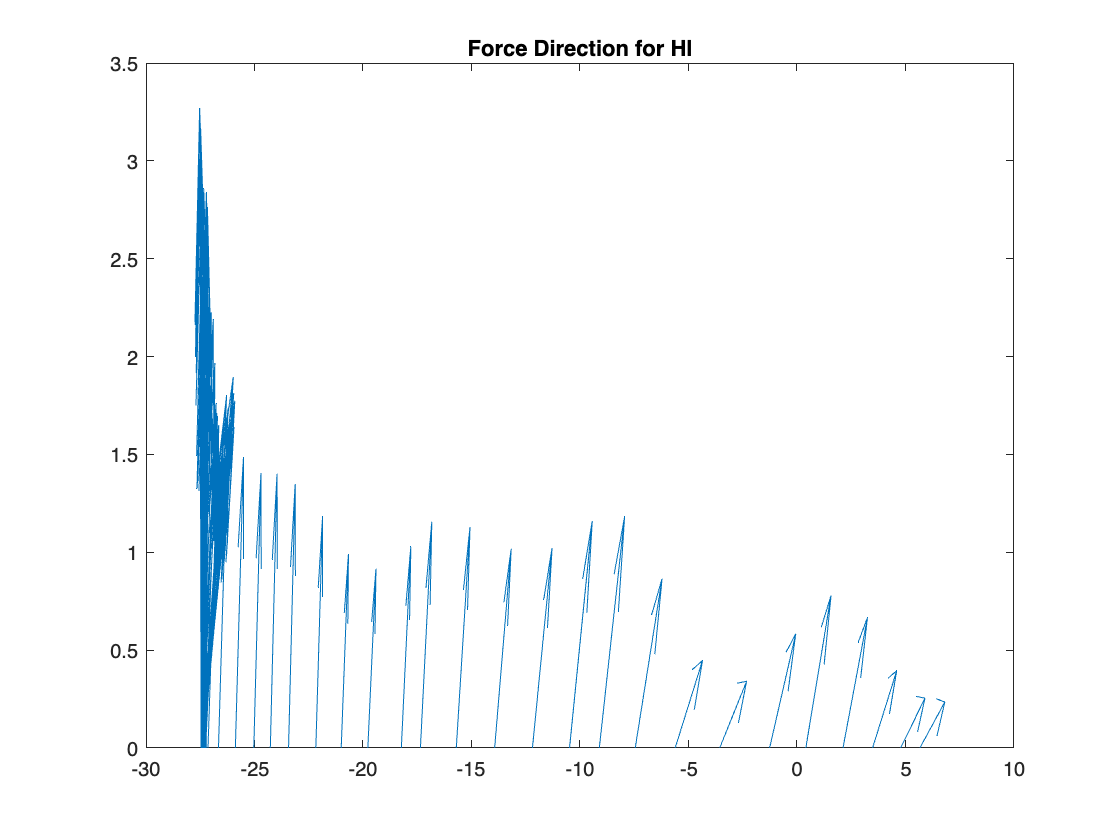

y_array_hl = zeros([83, 1]);
x_quiv_hl = pt9_hl_xcp;
u_quiv_hl = new_fx_hl_norm;
figure
v_quiv_hl = new_fz_hl_norm;
figure
quiver(x_quiv_hl, y_array_hl, u_quiv_hl, v_quiv_hl )
title('Force Direction for Hl')


%digitized points from video (dp)
    total_rows_dp = size(pt10_X)

total_rows_dp =    268     1


    dp_t0 = (1:total_rows_dp)' ./250

dp_t0 =     0.0040
    0.0080
    0.0120
    0.0160
    0.0200
    0.0240
    0.0280
    0.0320
    0.0360
    0.0400





%      pnt10_COP_X_video = pt10_X_s1(2:end) + diff_Xcp
%      pnt10_COP_Y_video = pt10_Y_s1(2:end) + diff_Ycp
%      pnt10_COP_Z_video = pt10_Z_s1 (2:end)+ diff_Zcp
% 
%      plot(p_stride_fl_f,pnt10_COP_X_video,p_stride_fl_f, fl_Xcp )




## **Forces Display for FL in Compass**

**Fl**

 if FL==1   
        fl_Fx_nth = fl_Fx_bw(2:200:end,:);
        fl_f0x_nth = fl_f_0x(2:200:end,:);
         figure (12)
        compass(fl_f0x_nth,fl_Fx_nth );
        title('fl_F_x')
    
        fl_Fy_nth = fl_Fy_bw(2:200:end,:);
        fl_f0y_nth = fl_f_0y(2:200:end,:);
        figure(13) 
        compass(fl_f0y_nth,fl_Fy_nth );
        title('fl_F_y')

        fl_Fz_nth = fl_Fz_bw(2:200:end,:);
        fl_f0z_nth = fl_f_0z(2:200:end,:);
        figure(14)
        compass(fl_f0z_nth,fl_Fz_nth );
        title('fl_F_z')
 end

**Hl**

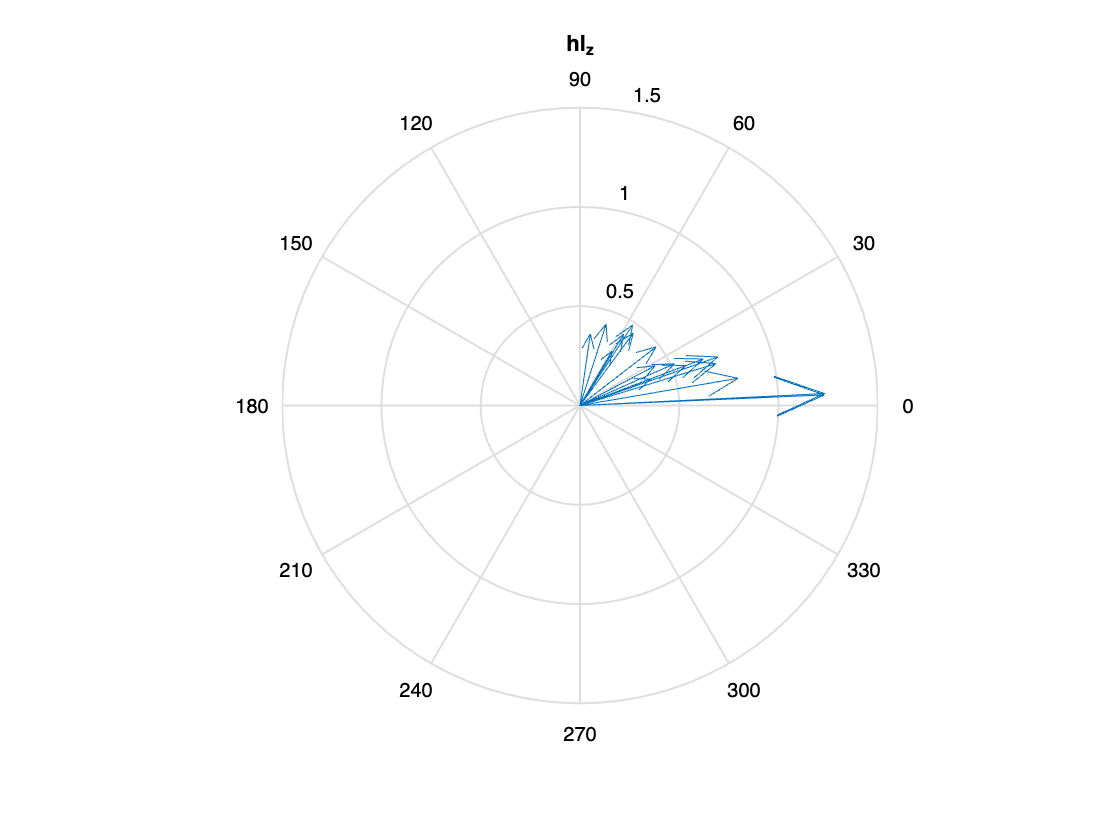

 if HL==1   
        hl_Fx_nth = hl_Fx_bw(2:200:end,:);
        hl_f0x_nth = hl_f_0x(2:200:end,:);
         figure (15)
        compass(hl_f0x_nth,hl_Fx_nth );
        title('hl_F_x')
    
        hl_Fy_nth = hl_Fy_bw(2:200:end,:);
        hl_f0y_nth = hl_f_0y(2:200:end,:);
        figure(16) 
        compass(hl_f0y_nth,hl_Fy_nth );
        title('hl_F_y')

        hl_Fz_nth = hl_Fz_bw(2:200:end,:);
        hl_f0z_nth = hl_f_0z(2:200:end,:);
        figure(17)
        compass(hl_f0z_nth,hl_Fz_nth );
        title('hl_F_z')
 end

**Forces Display for FL in Polar Plots with normalized data**

**Fl**

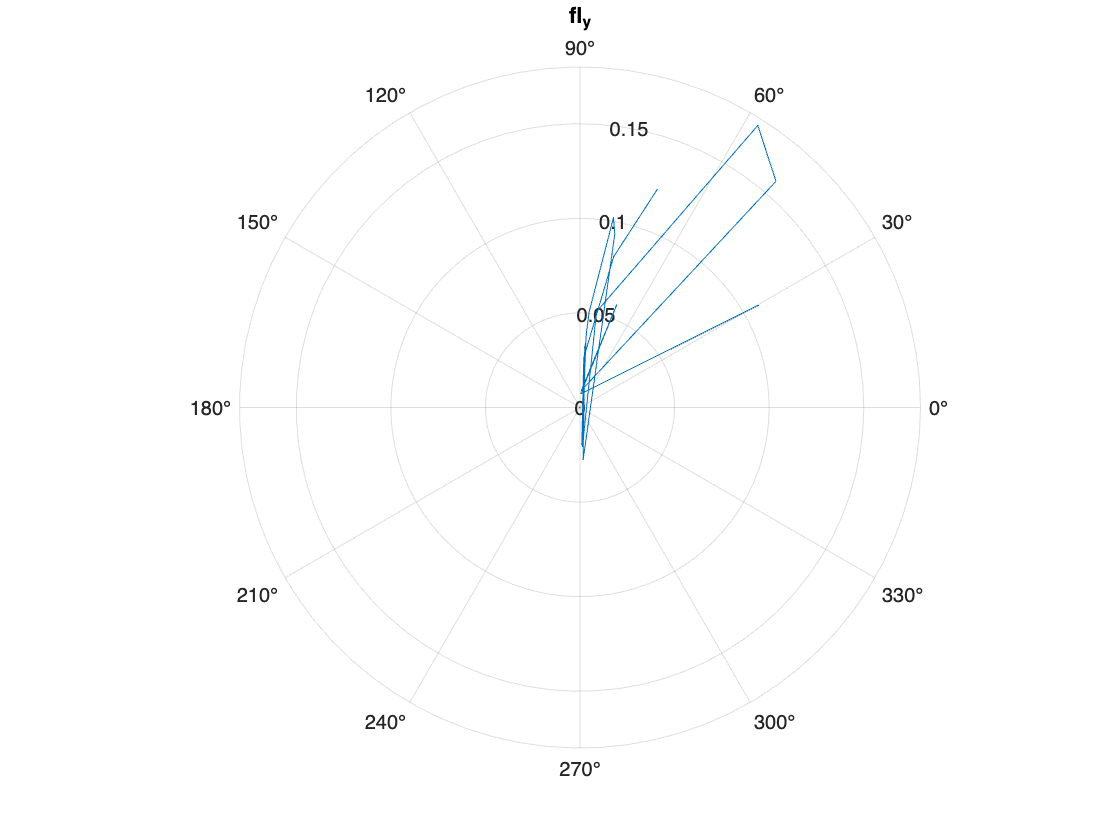

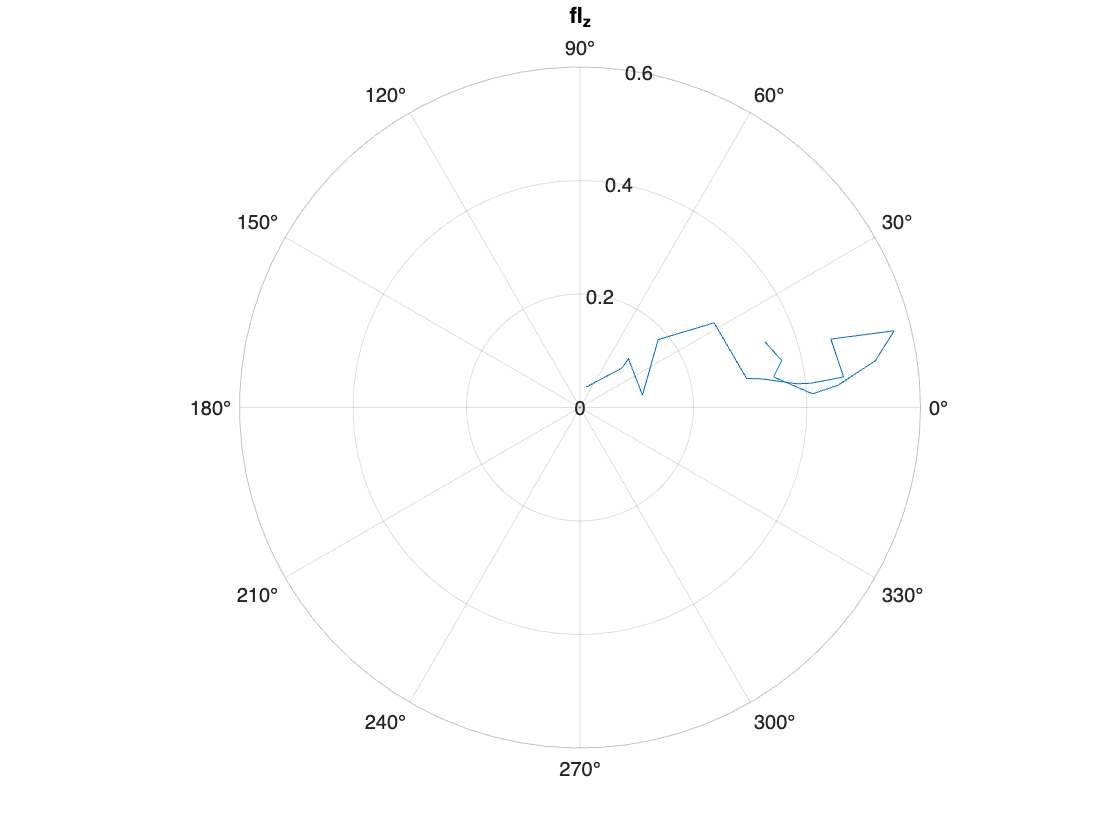

if FL ==1

    figure(18)
    polarplot(fl_f0x_nth,fl_Fx_nth)
    title('fl_F_x')

    figure(19)
    polarplot(fl_f0y_nth,fl_Fy_nth)
    title('fl_F_y')

    figure(20)
    polarplot(fl_f0z_nth,fl_Fz_nth)
    title('fl_F_z')

end

**Hl**

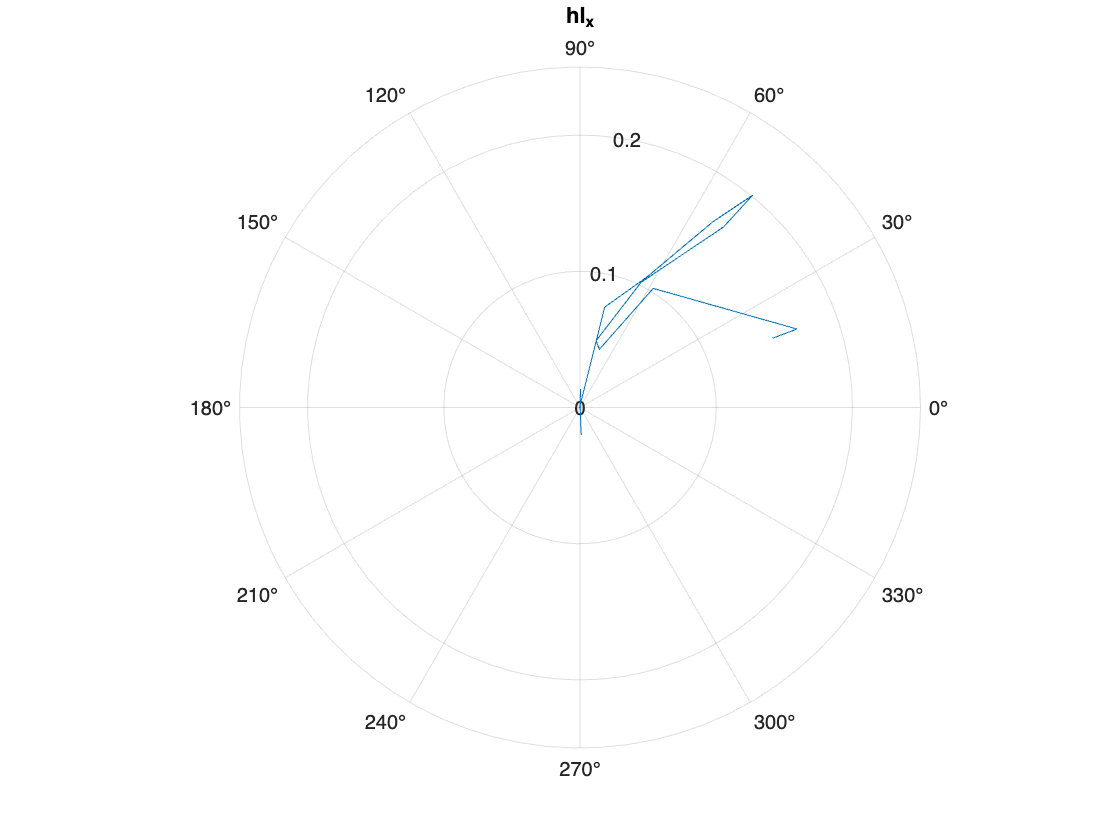

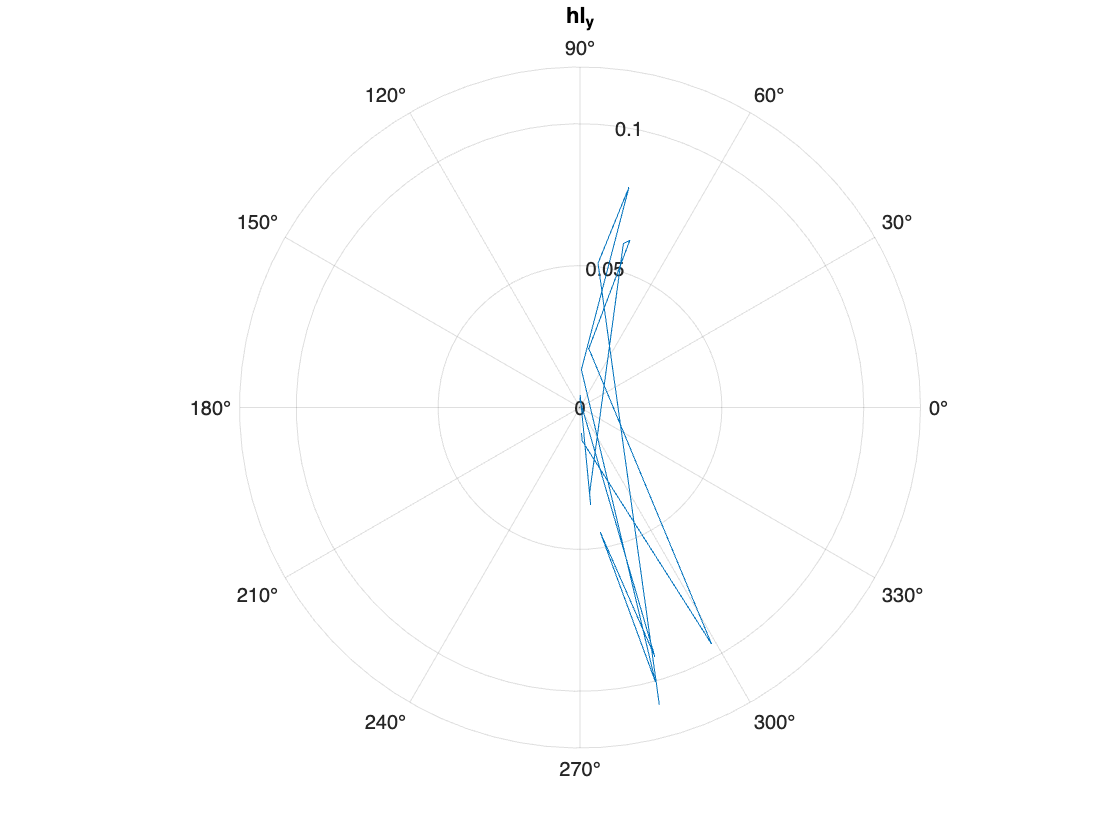

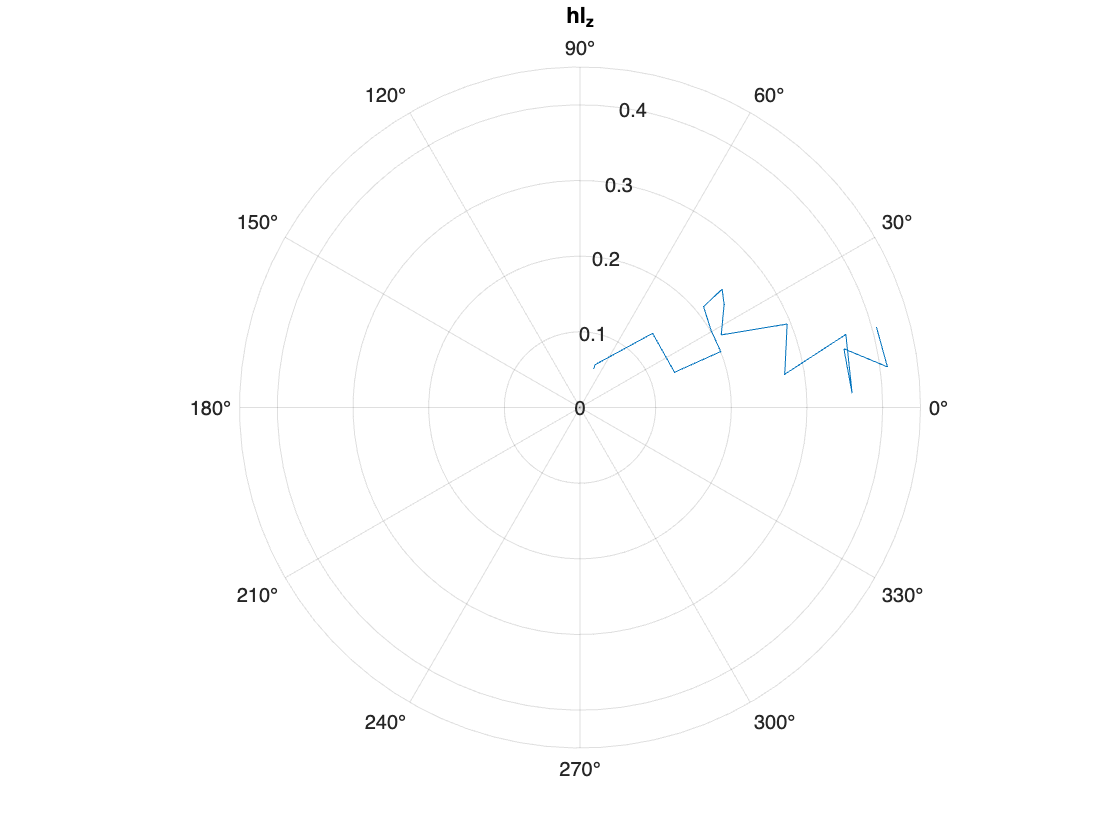

 
 if HL ==1

    figure(21)
    polarplot(hl_f0x_nth,hl_Fx_nth)
    title('hl_F_x')

    figure(22)
    polarplot(hl_f0y_nth,hl_Fy_nth)
    title('hl_F_y')

    figure(23)
    polarplot(hl_f0z_nth,hl_Fz_nth)
    title('hl_F_z')

 end

**Diplay of scaled and normalized data in feather()**

**Fl**

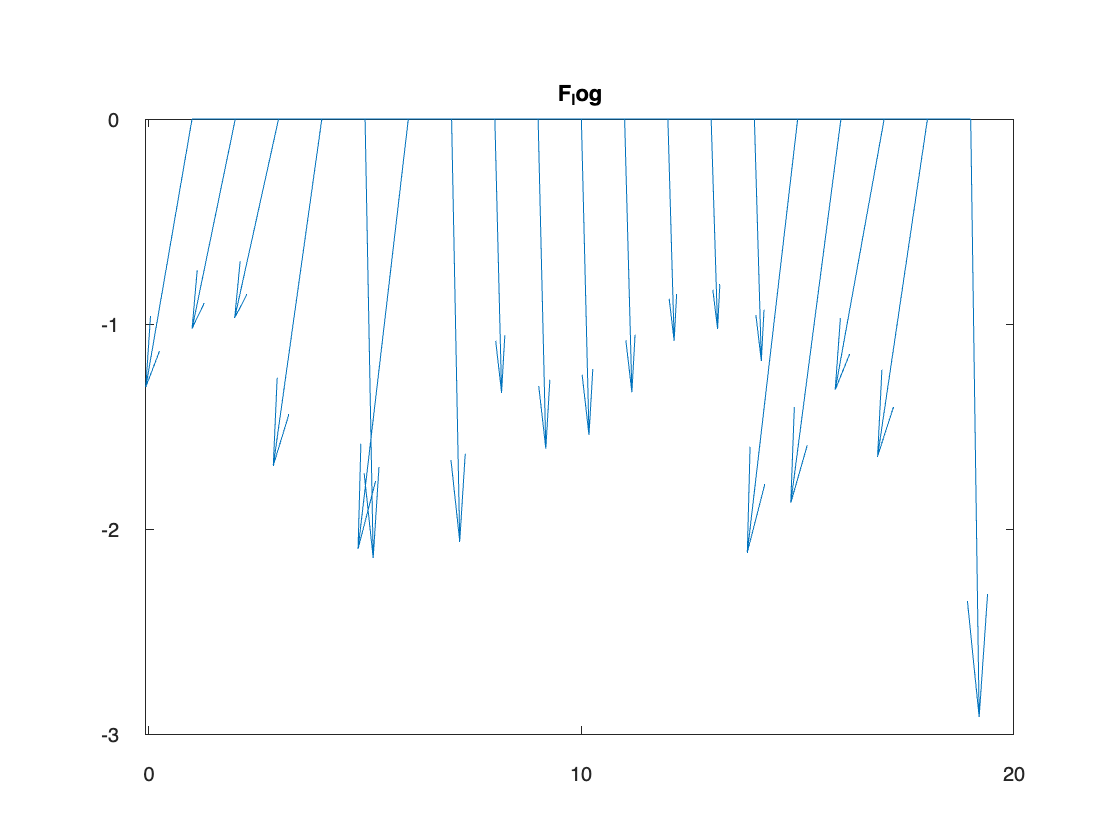

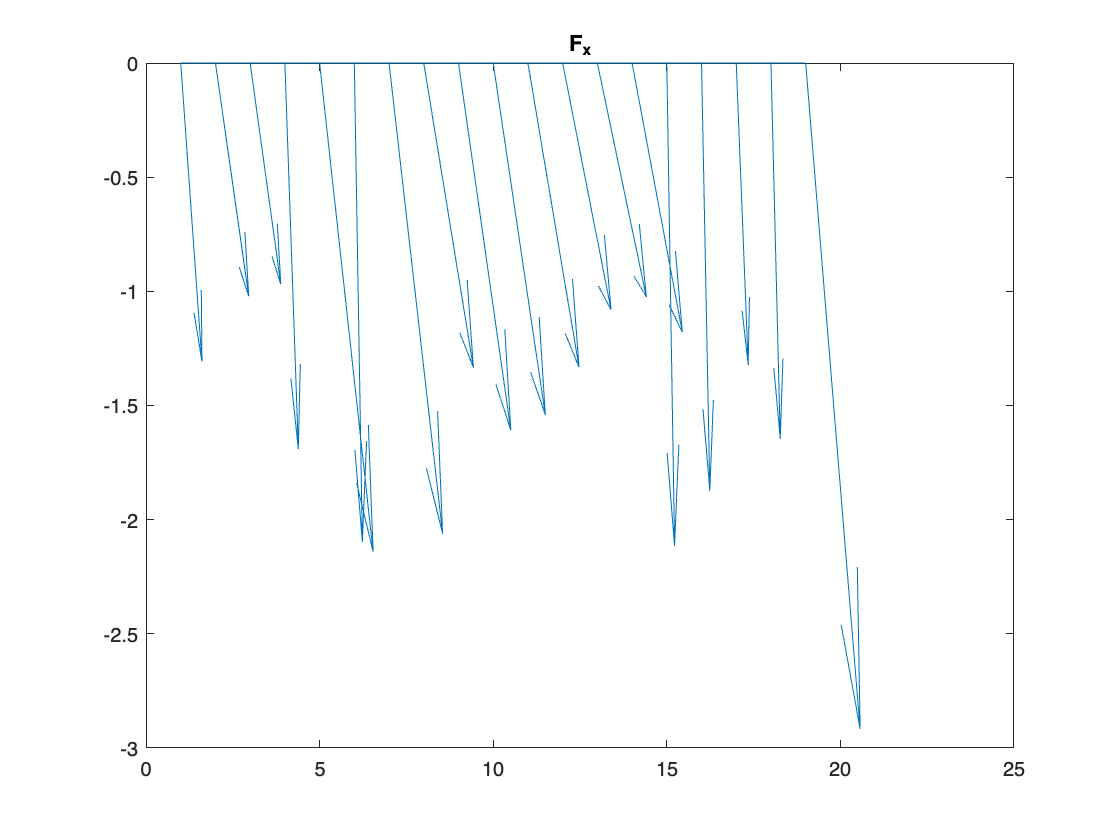

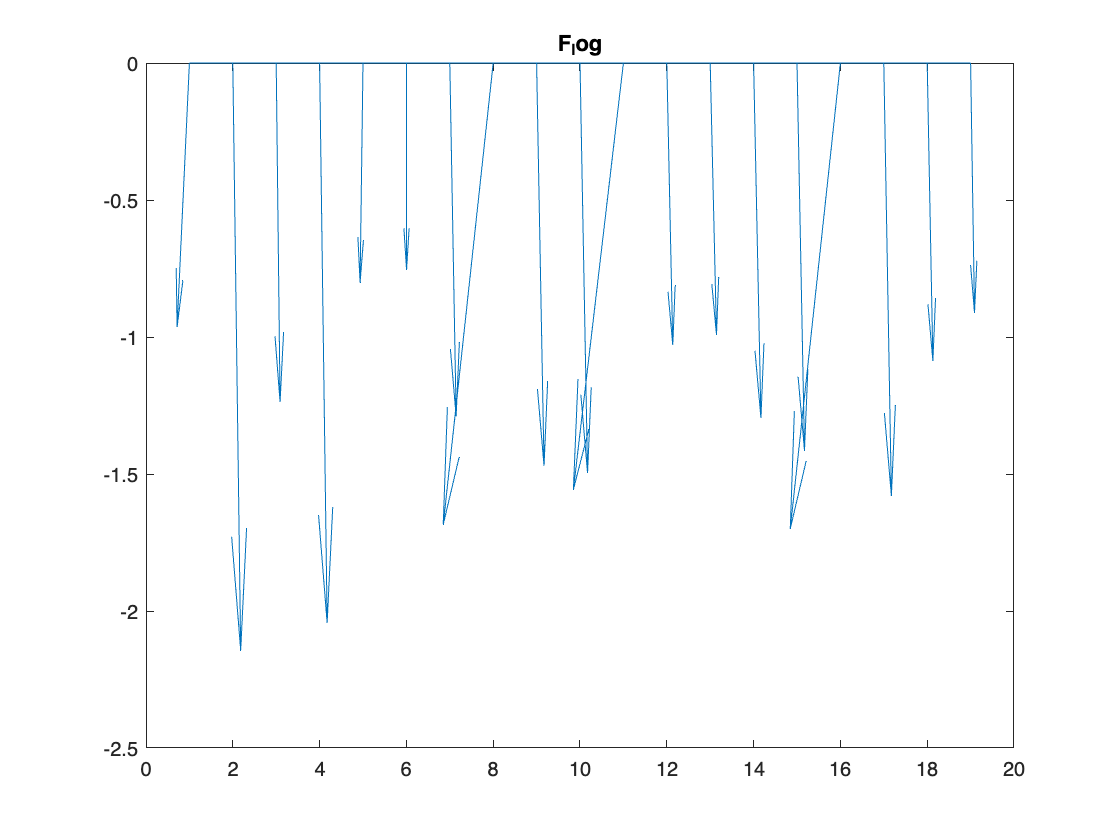

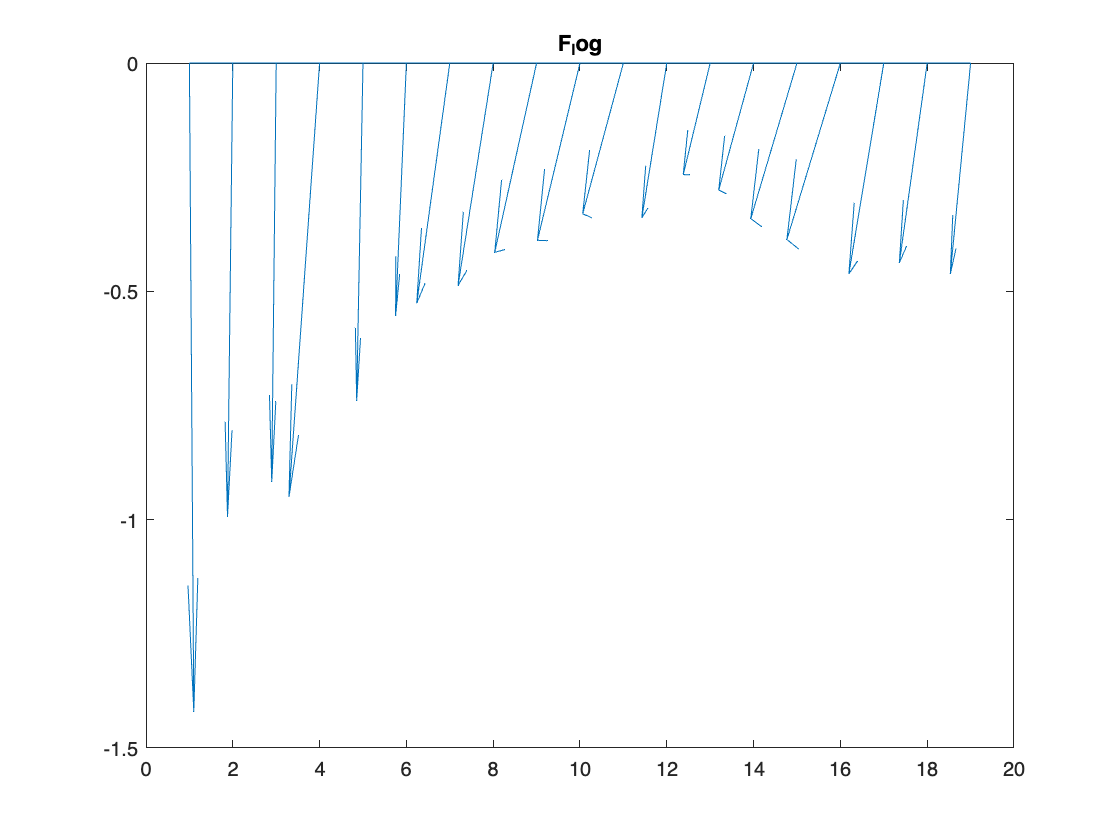

 if FL==1
     fl_Fx_log = log10(fl_Fx_nth);
     fl_Fx_deg_log = log10(fl_f0x_nth);
     %for f_x
     figure(24)
     feather(fl_Fx_deg_log,fl_Fx_log)
     title ('F_x_log')  %both are log10()

     figure(30)
     feather(fl_f0x_nth,fl_Fx_log)
     title ('F_x') 

       %for fy
     fl_Fy_log = log10(fl_Fy_nth);
     fl_Fy_deg_log = log10(fl_f0y_nth);
     figure(25)
     feather(fl_Fy_deg_log,fl_Fy_log)
     title ('F_y_log')  %both are log10()

     %for fz
     fl_Fz_log = log10(fl_Fz_nth);
     fl_Fz_deg_log = log10(fl_f0z_nth);
     figure(26)
     feather(fl_Fz_deg_log,fl_Fz_log)
     title ('F_z_log')  %both are log10()
 end

**Hl**

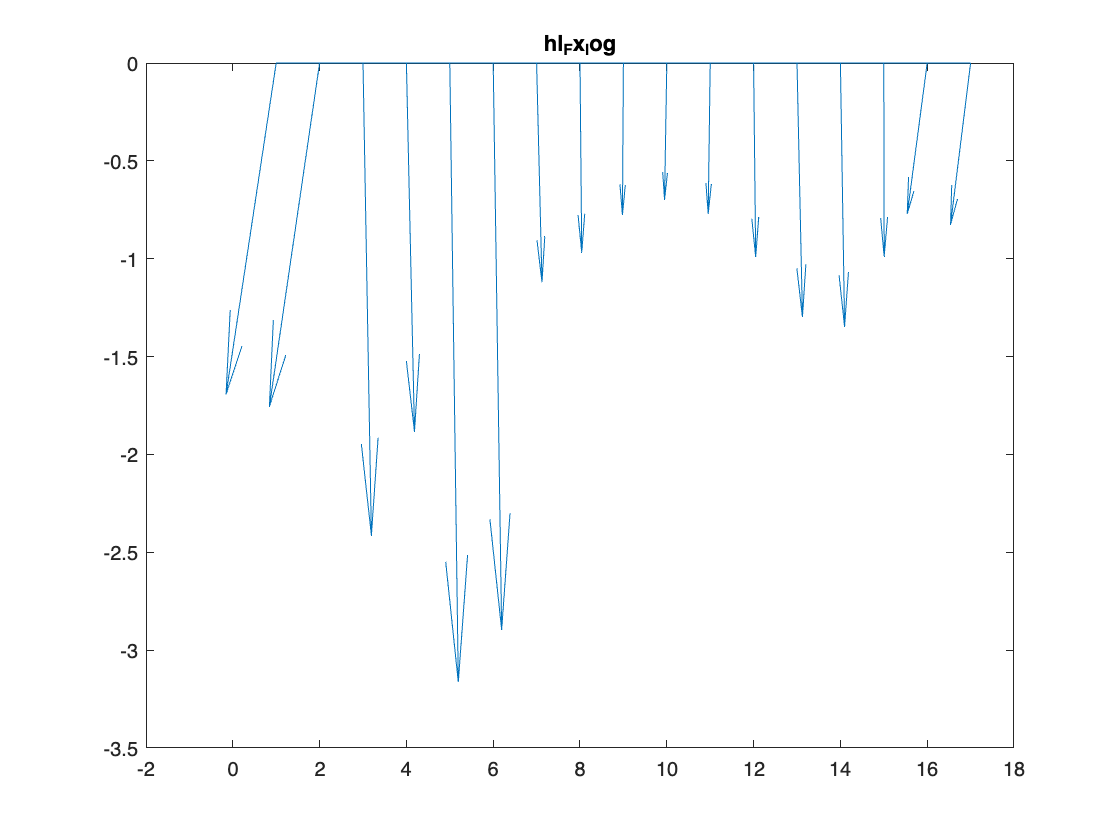

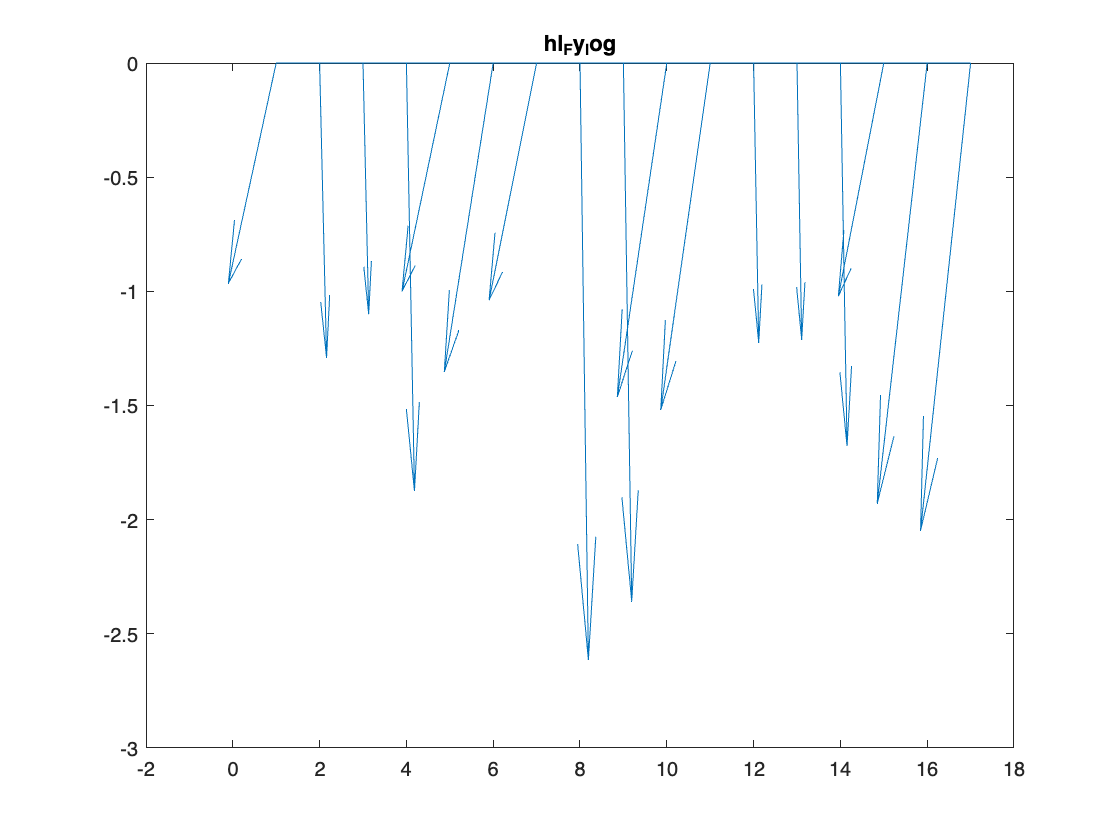

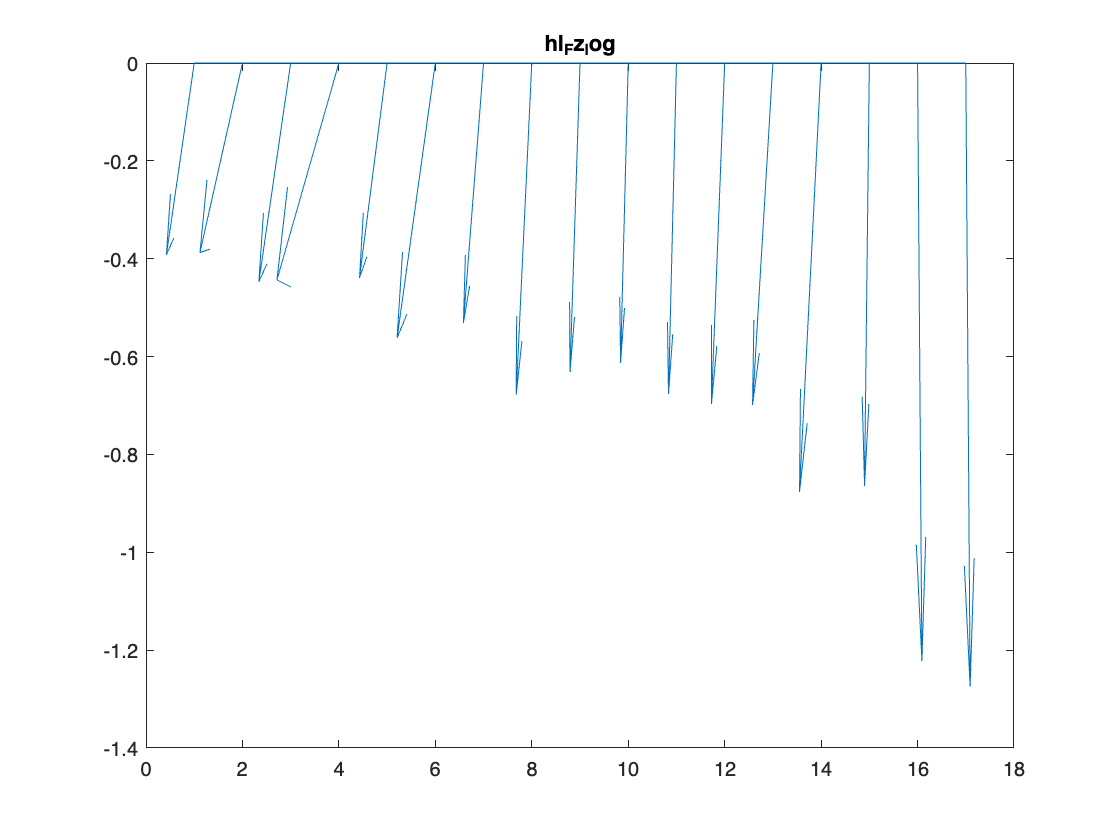

if HL==1
     hl_Fx_log = log10(hl_Fx_nth);
     hl_Fx_deg_log = log10(hl_f0x_nth);
     %for f_x
     figure(27)
     feather(hl_Fx_deg_log,hl_Fx_log)
     title ('hl_Fx_log')  %both are log10()

     %figure(25)
%      feather(fl_f0x_nth,fl_Fx_log)
%      title ('F_x') 

       %for fy
     hl_Fy_log = log10(hl_Fy_nth);
     hl_Fy_deg_log = log10(hl_f0y_nth);
     figure(28)
     feather(hl_Fy_deg_log,hl_Fy_log)
     title ('hl_Fy_log')  %both are log10()

     %for fz
     hl_Fz_log = log10(hl_Fz_nth);
     hl_Fz_deg_log = log10(hl_f0z_nth);
     figure(29)
     feather(hl_Fz_deg_log,hl_Fz_log)
     title ('hl_Fz_log')  %both are log10()
 end

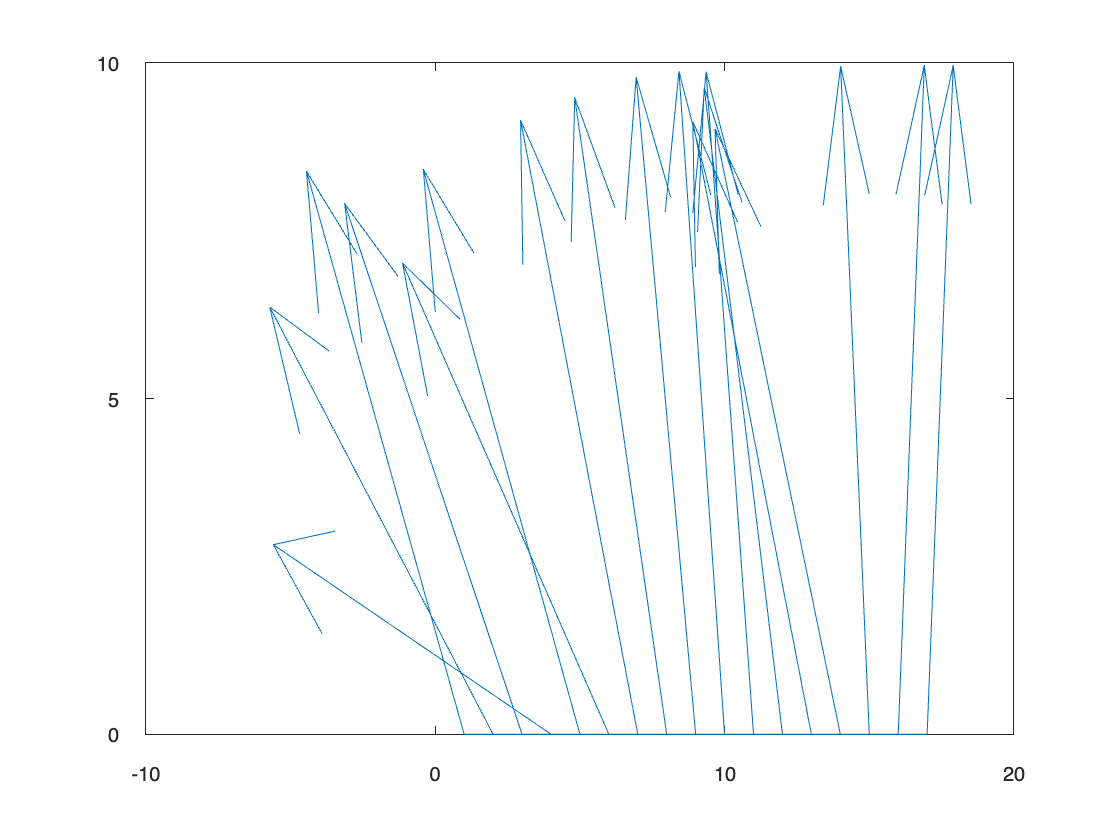




u = 10*sin(hl_Fz_deg_log );
v = 10*cos(hl_Fz_deg_log);
feather(u,v)

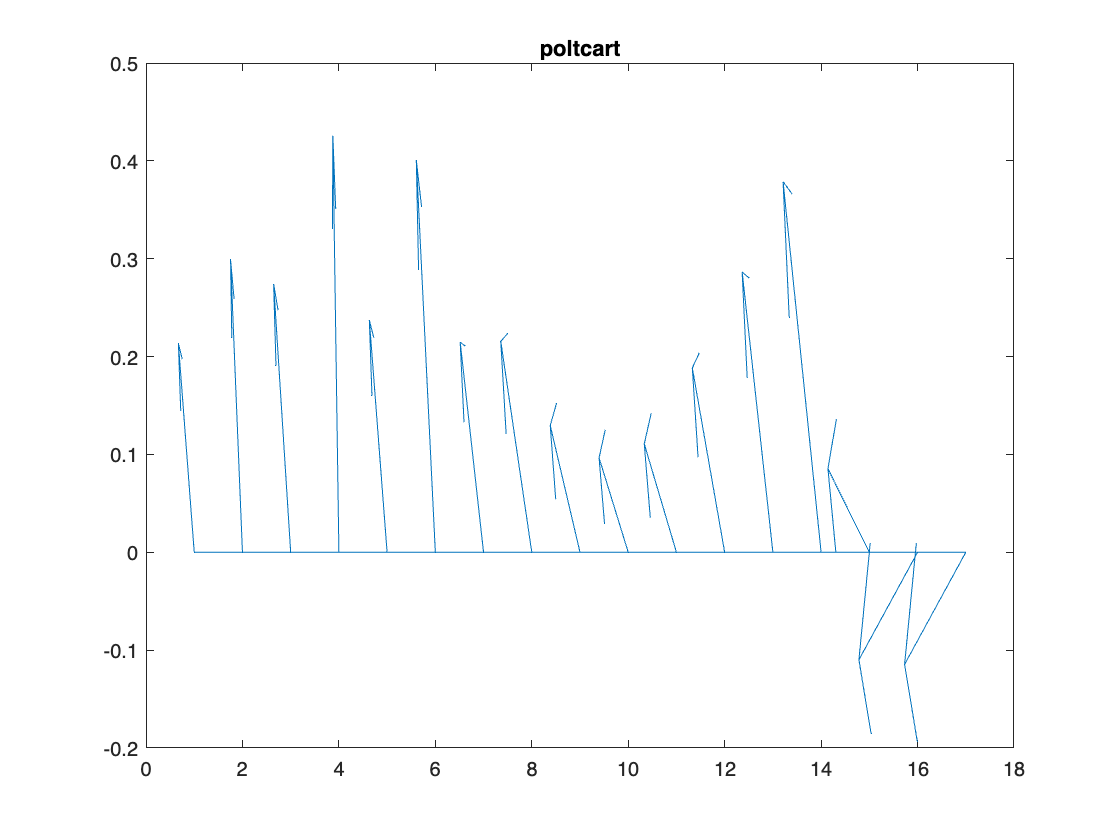



%  feather(fl_f0x_nth, y)
%  xlim([0 150])

%  loglog(fl_f0x_nth,fl_Fx_nth )
 
 [h, j] = pol2cart(hl_Fz_deg_log, hl_Fz_log );
    feather(h, j) 
    title ('poltcart')

% compass(Fx_nth,Fz_nth)

## Finding the perpendicular line for finding Torque

We need to find the perpendicular ine in order to find the distance of each joint, ans use that information to ultimetly find the torque

**Equation to findin the perpendicular line**

(y1 - y2) = mx (x2 - x1) 

**Fl**

% pnt 3


## Creating an y-axis autoscale

Adjusting Y-axis based upon maximum and min force readings 

This is an auto-scale in a sense for the graph in the following section

if  HL == 1
    if FL == 1
        max1 = max(f_x_fl)
        max2 = max(f_y_fl) 
        max3 = max(f_z_fl) 
        max4 = max(f_r_fl)
        max5 = max(f_x_hl)
        max6 = max(f_y_hl)
        max7 = max(f_z_hl)
        max8 = max(f_r_hl)
        maxcat = horzcat(max1, max2, max3, max4, max5, max6, max7, max8)
        [maxy,~] = max(maxcat)
        min1 = min(f_x_fl)
        min2 = min(f_y_fl) 
        min3 = min(f_z_fl) 
        min4 = min(f_r_fl)
        min5 = min(f_x_hl)
        min6 = min(f_y_hl)
        min7 = min(f_z_hl)
        min8 = min(f_r_hl)
        mincat = horzcat(min1, min2, min3, min4, min5, min6, min7, min8)
        [miny,~] = min(mincat)
        scale = horzcat(miny, maxy)
    else FL == 0
        max5 = max(f_x_hl)
        max6 = max(f_y_hl)
        max7 = max(f_z_hl)
        max8 = max(f_r_hl)
        maxcat = horzcat(max5, max6, max7, max8)
        [maxy,~] = max(maxcat)
        min5 = min(f_x_hl)
        min6 = min(f_y_hl)
        min7 = min(f_z_hl)
        min8 = min(f_r_hl)
        mincat = horzcat(min5, min6, min7, min8)
        [miny,~] = min(mincat)
        scale = horzcat(miny, maxy)
    end
else
    max1 = max(f_x_fl)
    max2 = max(f_y_fl) 
    max3 = max(f_z_fl) 
    max4 = max(f_r_fl)
    maxcat = horzcat(max1, max2, max3, max4)
    [maxy,~] = max(maxcat)
    min1 = min(f_x_fl)
    min2 = min(f_y_fl) 
    min3 = min(f_z_fl) 
    min4 = min(f_r_fl)
    mincat = horzcat(min1, min2, min3, min4)
    [miny,~] = min(mincat)
    scale = horzcat(miny, maxy)
end


max1 = 0.0028

max2 = 0.0058

max3 = 0.0146

max4 = 0.0150

max5 = 0.0051

max6 = 0.0028

max7 = 0.0114

max8 = 0.0118

maxcat =     0.0028    0.0058    0.0146    0.0150    0.0051    0.0028    0.0114    0.0118


maxy = 0.0150

min1 = -0.0029

min2 = -0.0014

min3 = 9.6722e-04

min4 = 0.0028

min5 = -6.0193e-04

min6 = -0.0030

min7 = 3.4237e-04

min8 = 0.0034

mincat =    -0.0029   -0.0014    0.0010    0.0028   -0.0006   -0.0030    0.0003    0.0034


miny = -0.0030

scale =    -0.0030    0.0150


## Plotting Force Graphs Trends Lines

Plotting figure

figure(5)
t=tiledlayout(4,1)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [4 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


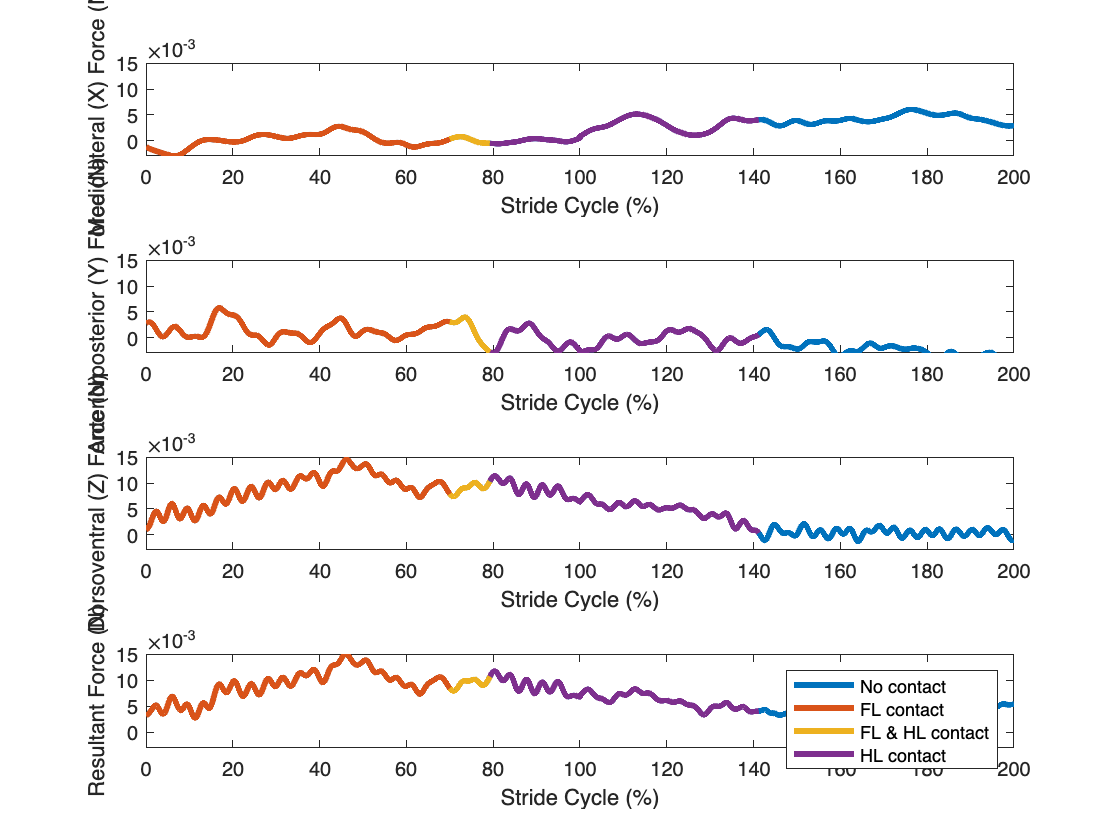

%subplot(4,1,1) % F_x graph
nexttile
if endf_s2_sec ~= 0 
    plot(p_strides_f,f_x_all,'LineWidth',3)
end
hold on 
if FL ==1 
    plot(p_stride_fl_f,f_x_fl,'LineWidth',3)
end
hold on 
if Overlap ~= 0
    plot(p_stride_overlap_f,f_x_overlap,'LineWidth',3)
end
hold on 
if endf_s2_sec ~= 0 
    plot(p_stride_hl_f,f_x_hl,'LineWidth',3)
end
xlabel('Stride Cycle (%)')
ylabel('Mediolateral (X) Force (N)')
ylim(scale)
%legend('No contact','FL contact','FL & HL contact','HL contact')
hold off
%subplot(4,1,2) % F_y graph
nexttile
if endf_s2_sec ~= 0 
    plot(p_strides_f,f_y_all,'LineWidth',3)
end
hold on 
if FL == 1
    plot(p_stride_fl_f,f_y_fl,'LineWidth',3)
end
hold on 
if Overlap ~= 0
    plot(p_stride_overlap_f,f_y_overlap,'LineWidth',3)
end
hold on 
if endf_s2_sec ~= 0 
    plot(p_stride_hl_f,f_y_hl,'LineWidth',3)
end
xlabel('Stride Cycle (%)')
ylabel('Anteriorposterior (Y) Force (N)')
ylim(scale)
%legend('No contact','FL contact','FL & HL contact','HL contact')
hold off
%subplot(4,1,3) % F_z graph
nexttile
if endf_s2_sec ~= 0 
    plot(p_strides_f,f_z_all,'LineWidth',3)
end
hold on 
if FL == 1
    plot(p_stride_fl_f,f_z_fl,'LineWidth',3)
end
hold on 
if Overlap ~= 0
    plot(p_stride_overlap_f,f_z_overlap,'LineWidth',3)
end
hold on 
if endf_s2_sec ~= 0 
    plot(p_stride_hl_f,f_z_hl,'LineWidth',3)
end
xlabel('Stride Cycle (%)')
ylabel('Dorsoventral (Z) Force (N)')
ylim(scale)
%legend('No contact','FL contact','FL & HL contact','HL contact')
hold off
%subplot(4,1,4) % F_r graph
nexttile
if endf_s2_sec ~= 0 
    plot(p_strides_f,f_r_all,'LineWidth',3)
end
hold on 
if FL == 1
    plot(p_stride_fl_f,f_r_fl,'LineWidth',3)
end
hold on 
if Overlap ~= 0
    plot(p_stride_overlap_f,f_r_overlap,'LineWidth',3)
end
hold on 
if endf_s2_sec ~= 0 
    plot(p_stride_hl_f,f_r_hl,'LineWidth',3)
end
xlabel('Stride Cycle (%)')
ylabel('Resultant Force (N)')
ylim(scale)
legend('No contact','FL contact','FL & HL contact','HL contact')
hold off

## Calculating radius, azimuth,and elevation angles for FL & HL

Creating forelimb and hindlimb vectors and then changing Cartesian coordinates to spherical coordinates. Here we are setting the hip and shoulder as the origin and base of the vectors. Here they are cartesian (X,Y,Z) coordinates. 


$$\begin{array}{l}
\textrm{pt6}-\textrm{pt3}=\textrm{FL}\;\textrm{vector}\\
\textrm{pt10}-\textrm{pt7}=\textrm{HL}\;\textrm{vector}
\end{array}$$


Following we do a transformation from cartesian to spherical coordinates. Where, the `r` component of the vector tell us how much effective use of the entire limb length is being used. `Azimuth` tells us how sprawed the posture is, how far away the limb is from the body (abducted or adducted). `Elevation` angle tells us how vertically extended the limb posture. 

Remember that:

pt 6 = longest FL phalange

pt 3 = shoulder

pt 10 = longest HL phalange

pt 7 = hip 

v_3_9_X_s1= pt9_X_s1-pt3_X_s1 

v_3_9_X_s1 =   -24.3940
  -24.3729
  -24.6780
  -24.7570
  -24.7991
  -25.0426
  -25.3022
  -25.3122
  -25.6007
  -25.7304


v_3_9_Y_s1= pt9_Y_s1-pt3_Y_s1 

v_3_9_Y_s1 =    10.1463
    9.8651
    9.5727
    9.1953
    9.1434
    9.0834
    9.1149
    9.2297
    9.3274
    9.4612


v_3_9_Z_s1= pt9_Z_s1-pt3_Z_s1 

v_3_9_Z_s1 =     6.6137
    6.2413
    6.2903
    6.4702
    6.4515
    6.4945
    6.5851
    6.5715
    6.8718
    7.1100


[FL_azimuth,FL_elevation,FL_r] = cart2sph(v_3_9_X_s1,v_3_9_Y_s1,v_3_9_Z_s1)

FL_azimuth =     2.7474
    2.7570
    2.7716
    2.7860
    2.7884
    2.7936
    2.7958
    2.7919
    2.7922
    2.7892


FL_elevation =     0.2453
    0.2331
    0.2333
    0.2403
    0.2394
    0.2391
    0.2401
    0.2392
    0.2471
    0.2538


FL_r =    27.2352
   27.0243
   27.2067
   27.1906
   27.2070
   27.4193
   27.6884
   27.7322
   28.1001
   28.3217




    v_7_10_X_s1= pt10_X_s1-pt7_X_s1 

v_7_10_X_s1 =    36.0515
   35.8300
   35.5893
   34.9788
   34.7038
   34.5704
   34.4978
   34.4507
   34.2770
   34.1612


    v_7_10_Y_s1= pt10_Y_s1-pt7_Y_s1 

v_7_10_Y_s1 =    -3.2748
   -1.6526
   -0.0660
    0.4574
    1.2214
    1.6467
    1.7854
    1.9180
    1.9416
    1.9624


    v_7_10_Z_s1= pt10_Z_s1-pt7_Z_s1 

v_7_10_Z_s1 =     2.6692
    3.0161
    3.6813
    4.8527
    5.3788
    5.3722
    5.3837
    5.3692
    5.4232
    5.4876


    [HL_azimuth,HL_elevation,HL_r] = cart2sph(v_7_10_X_s1,v_7_10_Y_s1,v_7_10_Z_s1)

HL_azimuth =    -0.0906
   -0.0461
   -0.0019
    0.0131
    0.0352
    0.0476
    0.0517
    0.0556
    0.0566
    0.0574


HL_elevation =     0.0736
    0.0839
    0.1031
    0.1378
    0.1537
    0.1540
    0.1546
    0.1544
    0.1567
    0.1590


HL_r =    36.2982
   35.9947
   35.7793
   35.3167
   35.1394
   35.0241
   34.9610
   34.9193
   34.7577
   34.6547


Converting spherical coordinates from radians to degrees, **r should be in units of mm**

Only need this for cartesian ploting 

FL_azimuth_deg = rad2deg(FL_azimuth)

FL_azimuth_deg =   157.4160
  157.9641
  158.7985
  159.6240
  159.7611
  160.0634
  160.1888
  159.9664
  159.9812
  159.8112


FL_elevation_deg = rad2deg(FL_elevation)

FL_elevation_deg =    14.0540
   13.3531
   13.3679
   13.7661
   13.7171
   13.7012
   13.7584
   13.7073
   14.1551
   14.5394



  
    HL_azimuth_deg = rad2deg(HL_azimuth)

HL_azimuth_deg =    -5.1903
   -2.6408
   -0.1063
    0.7492
    2.0157
    2.7271
    2.9627
    3.1866
    3.2420
    3.2878


    HL_elevation_deg = rad2deg(HL_elevation)

HL_elevation_deg =     4.2171
    4.8067
    5.9055
    7.8978
    8.8049
    8.8232
    8.8583
    8.8449
    8.9765
    9.1111


Making sure that the data are positive values from 0-360 deg (don't need to worry about this anymore) Negative degrees are most intuitive. 

% [row_az, ~] = find(FL_azimuth_deg<0)
% FL_azimuth_deg(row_az) = 360 + FL_azimuth_deg(row_az)
% 
% [row_el, ~] = find(FL_elevation_deg<0)
% FL_elevation_deg(FL_elevation_deg<0) = 360 + FL_elevation_deg(row_el)
% 
% if HL == 1
%     [row_az_hl, ~] = find(HL_azimuth_deg<0)
%     HL_azimuth_deg(HL_azimuth_deg<0) = 360 + HL_azimuth_deg(row_az_hl)
% 
%     [row_el_hl, ~] = find(HL_elevation_deg<0)
%     HL_elevation_deg(HL_elevation_deg<0) = 360 + HL_elevation_deg(row_el_hl)
% 
% end

## Plotting Limb Radial Magnitude Vector Graphs

% figure(2)
% t=tiledlayout(3,1)
% %subplot(4,1,1) % F_x graph
% nexttile
% if FL == 1 
%     plot(p_stride1, FL_azimuth_deg,'LineWidth',3)
% end
% hold on 
% if HL == 1
%     plot(total_digitized_time, HL_azimuth_deg,'LineWidth',3)
% end
% xlabel('Stride Cycle (%)')
% ylabel('Azimuth Angle (deg)')
% %ylim(scale)
% 
% if FL == 1 && HL == 1
%     legend('FL azimuth', 'HL azimuth')
% elseif FL == 1
%     legend('FL azimuth')
% else 
%     legend ('HL azimuth')
% end    
% hold off
% 
% nexttile
% if FL == 1
%    plot(p_stride1, FL_elevation_deg,'LineWidth',3)
% end
% hold on 
% if HL == 1
%     plot(total_digitized_time, HL_elevation_deg,'LineWidth',3)
% end
% xlabel('Stride Cycle (%)')
% ylabel('Elevation Angle (deg)')
% %ylim(scale)
% 
% if FL == 1 && HL == 1
%     legend('FL elevation', 'HL elevation')
% elseif FL == 1
%     legend('FL elevation')
% else 
%     legend ('HL elevation')
% end    
% hold off
% 
% nexttile
% if FL == 1
%    plot(p_stride1, FL_r,'LineWidth',3)
% end
% hold on 
% if HL == 1
%     plot(total_digitized_time, HL_r,'LineWidth',3)
% end
% xlabel('Stride Cycle (%)')
% ylabel('R magnitude (mm)')
% %ylim(scale)
% 
% if FL == 1 && HL == 1
%     legend('FL R magntiude', 'HL magnitude')
% elseif FL == 1
%     legend('FL magnitude')
% else 
%     legend ('HL magnitude')
% end    
% hold off

Radial Magntiude Graph

% figure(2)
% if FL == 1
%    t2 = plot(p_stride1, FL_r,'LineWidth',3)
% end
% if HL == 1
%     hold on 
%     t2 = plot(total_digitized_time, HL_r,'LineWidth',3)
%     hold off
% end
% 
% xlabel('Stride Cycle (%)')
% ylabel('R magnitude (mm)')
% %ylim(scale)
% 
% if FL == 1 && HL == 1
%     legend('FL R magntiude', 'HL magnitude')
% elseif FL == 1
%     legend('FL magnitude')
% else 
%     legend ('HL magnitude')
% end    

Save Graph 

% f = gcf
% limbvectorgraph = append(walk_seq, '_limbvectorgraph.pdf')
% exportgraphics(f, limbvectorgraph,'ContentType','vector')

## Graphing Limb Vectors with Windrose Plots 

Rose plots are also known as angle histograms. Particularly direction density wind plots. These plots take measurements in radians and will convert them to degrees, no need to convert to degrees. 

% figure(3)
% if HL == 0 && FL == 1
%     t2=tiledlayout(1,2)
% else
%     t2=tiledlayout(4,1)
% end
% nexttile
% rose(FL_azimuth)
% title('Forelimb Azimuth Angle (deg)')
% nexttile
% rose(FL_elevation)
% title('Forelimb Elevation Angle (deg)')
% if HL == 1
%     nexttile
%     rose(HL_azimuth)
%     title('Hindlimb Azimuth Angle (deg)')
%     nexttile        
%     rose(HL_elevation)
%     title('Hindlimb Elevation Angle (deg)')
% end
% hold off

Save Graph 

% windrosegraph = append(walk_seq, '_windroseplot.pdf')
% exportgraphics(t2, windrosegraph,'ContentType','vector')

## Polar Plots

Polar plots plot azimuth and elevation angles relative to radial extension. 

**Polar histograms**

% figure(4)
% if HL == 0 && FL == 1
%     t3=tiledlayout(1,2)
% else
%     t3=tiledlayout(4,1)
% end
% nexttile
% polarhistogram(FL_azimuth,20)
% title('Forelimb Azimuth Angle (deg)')
% nexttile
% polarhistogram(FL_elevation,10)
% title('Forelimb Elevation Angle (deg)')
% if HL == 1
%     nexttile
%     polarhistogram(HL_azimuth,20)
%     title('Hindlimb Azimuth Angle (deg)')
%     nexttile
%     polarhistogram(HL_elevation,10)
%     title('Hindlimb Azimuth Angle (deg)')
% end

Save Graph 

% polarhistgraph = append(walk_seq, '_polarhistplots.pdf')
% exportgraphics(t3, polarhistgraph,'ContentType','vector')

**Polar Plots**

% figure(5)
% if HL == 0 && FL == 1
%     t4=tiledlayout(1,2)
% else
%     t4=tiledlayout(4,1)
% end
% nexttile
% p = polarplot(FL_azimuth, FL_r, 'LineWidth',3)
% [n, ~] = size(FL_r)
% %hold on
% 
% % modified jet-colormap
% cd = [uint8(parula(n)*255) uint8(ones(n,1))].';
% drawnow
% set(p.Edge, 'ColorBinding','interpolated', 'ColorData',cd)
% title('FL Limb Extension vs. Azimuth Angle (deg)')
% %hold off
% 
% nexttile
% p2 = polarplot(FL_elevation, FL_r, 'LineWidth',3)
% %hold on
% 
% % modified jet-colormap
% %cd = [uint8(parula(n)*255) uint8(ones(n,1))].';
% drawnow
% set(p2.Edge, 'ColorBinding','interpolated', 'ColorData',cd)
% %hold off
% 
% %legend
% c=colorbar('Ticks',[0,0.1,0.2,0.3,0.4,0.5,0.6,0.7,0.8,0.9,1], ...
%     'TickLabels',{'0','10','20','30','40','50','60','70','80','90','100'})
% c.Label.String = 'Stride Cycle (%)'
% title('FL Limb Extension vs. Elevation Angle (deg)')
% 
% if HL == 1
%     nexttile
%     p = polarplot(HL_azimuth, HL_r, 'LineWidth',3)
%     [n, ~] = size(HL_r)
% 
%     % modified jet-colormap
%     cd = [uint8(parula(n)*255) uint8(ones(n,1))].';
%     drawnow
%     set(p.Edge, 'ColorBinding','interpolated', 'ColorData',cd)
%     title('HL Limb Extension vs. Azimuth Angle (deg)')
% 
%     nexttile
%     p2 = polarplot(HL_elevation, HL_r, 'LineWidth',3)
% 
%     % modified jet-colormap
%     %cd = [uint8(parula(n)*255) uint8(ones(n,1))].';
%     drawnow
%     set(p2.Edge, 'ColorBinding','interpolated', 'ColorData',cd)
%     title('HL Limb Extension vs. Elevation Angle (deg)')
% end

Save Graph 

% polarplotsgraph = append(walk_seq, '_polarplots.png')
% %exportgraphics(t4, polarplotsgraph,'ContentType','vector')
% saveas(t4,polarplotsgraph)

### Exporting Limb Vector Data

Now that we have all of the data, we need to export the f(x), f(y), f(z) and R data to their own files to be combined with the other trials on a single graph. That will be a seperate script, but in this portion we will export said data.

if FL == 1 && HL == 1
    limbvector_file = append(walk_seq, '_limbvectordata.csv')
    T = table(FL_azimuth,FL_elevation,FL_r,HL_azimuth, HL_elevation, HL_r)
    writetable(T,limbvector_file,'Delimiter',',','QuoteStrings',true)
elseif HL == 1
    limbvector_file = append(walk_seq, '_limbvectordata.csv')
    T = table(HL_azimuth, HL_elevation, HL_r)
    writetable(T,limbvector_file,'Delimiter',',','QuoteStrings',true)
else
    limbvector_file = append(walk_seq, '_limbvectordata.csv')
    T = table(FL_azimuth,FL_elevation,FL_r)
    writetable(T,limbvector_file,'Delimiter',',','QuoteStrings',true)
end

limbvector_file = '20220429_ks1_walk3_limbvectordata.csv'

T = 131×6 table
    FL_azimuth    FL_elevation     FL_r     HL_azimuth    HL_elevation     HL_r 
    __________    ____________    ______    __________    ____________    ______

      2.7474        0.24529       27.235    -0.090589       0.073603      36.298
       2.757        0.23306       27.024     -0.04609       0.083892      35.995
      2.7716        0.23331       27.207    -0.001855        0.10307      35.779
       2.786        0.24026       27.191     0.013075        0.13784      35.317
      2.7884        0.23941       27.207      0.03518        0.15367      35.139
      2.7936        0.23913       27.419     0.047597        0.15399      35.024
      2.7958        0.24013       27.688     0.051709        0.15461      34.961
      2.7919        0.23924       27.732     0.055